# This is MATLAB codes of the article:				

*Cell nucleus as a mcirorheological probe to study the rheology of the cytoskeleton*, by M. Moradi and Ehssan Nazockdast 

## ***1- Nucleus surrounded by a Newotonian fluid***

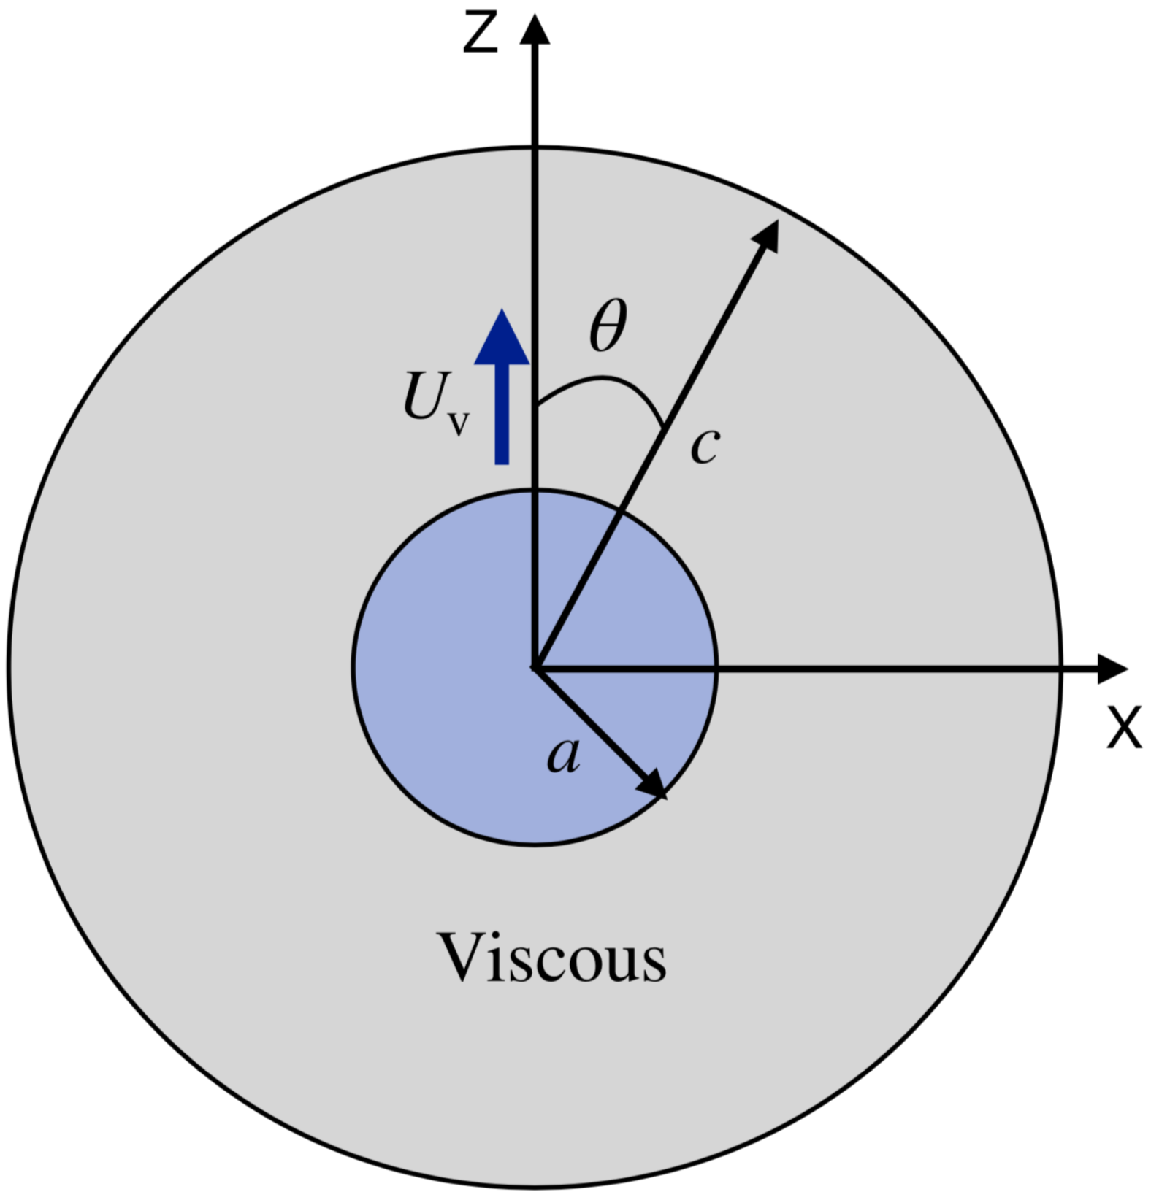


$$U_{\mathrm{v}} =  \frac{1}{3} {\lambda}_1 \left(  \frac{6+ 6\chi + {\chi}^2 +  {\chi}^3 +  {\chi}^4}{1+ \chi + {\chi}^2 + {\chi}^3 + {\chi}^4} \right) - \frac{1}{3} {\lambda}_{1}^{'} \left(  \frac{-3- 3 \chi +2 {\chi}^2 +2 {\chi}^3 +2 {\chi}^4}{1+ \chi + {\chi}^2 + {\chi}^3 + {\chi}^4} \right) $$


clc; clear;
syms A B C a c lambda1 lambdap1 r U1
% radial and tangential velocity component of Stokes equation, for n=2; 
% see equation A5 and A6 in AppendixA in the main text.
vr = -(A + B/r^3 + C * r^2) ; 
vtheta = A - B/(2* r^3)  + 2 * C * r^2 ;

% The (radial and tangential) velocity at r=a, and r=c (see the above figure)
vr_a = subs(vr,r,a);
vtheta_a = subs(vtheta,r,a);
vr_c = subs(vr,r,c);
vtheta_c = subs(vtheta,r,c);

% The boundary conditions at r=a (in moving frame of nucleus) and r=c
eqns = [  vr_a  == U1 , vtheta_a  == -U1 , ...
          vr_c == ( lambda1), ...    
          vtheta_c == ( lambdap1) ]; 
% solving the equations for uknowns A, B, C, and U1(nucleus velocity)      
S = solve(eqns,A,B,C,U1);
A0 = S.A; B0 = S.B; C0 = S.C; U10 = S.U1;
% The velocity of nucleus:
U_v = simplify(U10);

%%%%%%% plot U_v for solid sphere vs \chi %%%%%%%%%%%
% this part replicate fig2(c)
clc; clear;
lambda1 =1; lambdaP1 =1; % first surface velocity modes
chi1 = 0:0.01:1; % chi1 = a/c
% nucleus velocity, Eq.2 in the main text:
U_v =  lambda1/3 * ((6 + 6.*chi1 + chi1.^2 + chi1.^3 + chi1.^4)./(1 + chi1 + chi1.^2 + chi1.^3 + chi1.^4))...
     -lambdaP1/3 * ((2.* chi1.^4 + 2 .* chi1.^3 + 2 .* chi1.^2 -3 .* chi1 - 3 )./(1 + chi1 + chi1.^2 + chi1.^3 + chi1.^4)) ;

plot(chi1,U_v,'LineWidth',2)

**Outer cell shape for some special values of the first five modes (Fig 2b) : **$${\lambda}_n =[1.0000  ; -1.1975 ;  -0.8497  ; -0.8296  ; -0.2806]$ and 
$ {\lambda}_{n}^{\prime} = [1.0000  ;  1.7277  ;  1.3449 ;  -0.8401 ;  1.8323 ]$. $

clc;clear;
colormap('gray');
n_theta = 50; n_phi = 50; % number of grid points in theta and phi coordinates
% making meshgrid of dimension: n_theta * n_phi
[THETA,PHI]=meshgrid(linspace(0,pi,n_theta),linspace(0,2*pi,n_phi));

% surface velocity modes
lambda =  [1.0000  ; -1.1975 ;  -0.8497  ; -0.8296  ; -0.2806 ; -0.0875];
lambdap =  [1.0000  ;  1.7277  ;  1.3449 ;  -0.8401 ;  1.8323  ;  0.8922];

N = 1:1:6;
n_max = 5;
ur_M = zeros(n_theta,n_phi);
utheta_M = ur_M;
  % calculating r and theta velocity components from Eq.1(b) in main text 
for n=1:n_max 
    ur_M = ur_M +  lambda(n) .* legendreP(n,cos(THETA));
    utheta_M = utheta_M +lambdap(n).*((2/(2*n+1))* (1./(sin(THETA)+1e-10)) .* ...
              (legendreP(n-1,cos(THETA)) - legendreP(n+1,cos(THETA))));
end     
% surface velocity in cartesian coordinates:
    ux_M=ur_M.*sin(THETA).*cos(PHI)+ utheta_M.*cos(THETA).*cos(PHI);
    uy_M=ur_M.*sin(THETA).*sin(PHI)+ utheta_M.*cos(THETA).*sin(PHI);
    uz_M=ur_M.*cos(THETA)-utheta_M.*sin(THETA);

% coordinates of sphere surface
x=cos(PHI).*sin(THETA);
y=sin(PHI).*sin(THETA);
z=cos(THETA);

% ploting the deformed surface
h=surf(x+0.2*ux_M,y+0.2*uy_M,z+0.2*uz_M,ones(n_theta)); hold on; drawnow;

caxis([-1,1]);
alpha(0.5);
axis equal;
set(gca,'visible','off')


## ***2- Nucleus inside a Viscoelastic medium*** 

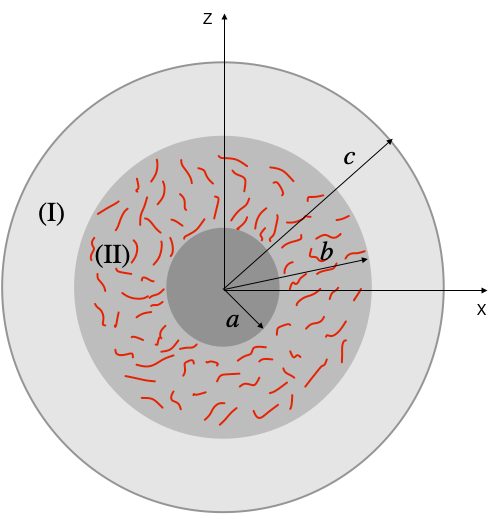

**(a)** **General case.**

%%%%%%%%%%%%%%%%%%%% U_ve %%%%%%%%%%%%%%%%
clc; clear;
syms AP BP CP DP A B C D alpha a b c r U2 U1 Lambda1 LambdaP1 s tau Gt

% radial and tangential velocity component of Stokes equation, for n=2; 
% see equation A5 and A6 in AppendixA in the main text.
vpr = -(AP + BP/r^3 + CP *r^2 + DP/r);
vptheta = AP - BP/(2*r^3) + 2*CP* r^2 + DP/(2*r);

vr_out = -( A + B/r^3 + C * r^2) ;
vtheta_out = A - B/(2* r^3)  + 2*C* r^2 ;

% The (radial and tangential) velocity at r=a, r=b, and r=c:
vpr_a = subs(vpr , r,a);
vptheta_a = subs(vptheta , r ,a);

vpr_b = subs(vpr , r,b);
vptheta_b = subs(vptheta , r ,b);

vr_out_b = subs(vr_out , r,b);
vtheta_out_b = subs(vtheta_out , r,b);

vr_out_c = subs(vr_out , r,c);
vtheta_out_c = subs(vtheta_out , r,c);

% Applying BCs as in Eq(1), and Eq(6) of the paper 
% (in moving frame of nuleus)
eqns = [ vpr_a == 0 , vptheta_a == 0 , ...
         vr_out_b == vpr_b , vtheta_out_b == vptheta_b , ...
         3*B/b^4 + 3*C*b == (1+Gt)*(3*BP/b^4 + 3*CP*b ) , ...
         6*B/b^4 + 6*C*b  == (1+Gt)*( 6*BP/b^4 + 6*CP*b + 3* DP/(b^2)) , ...
         vr_out_c == (1/s)*(-s*U1 + s*Lambda1 ) ,...
         vtheta_out_c == (1/s)*(s*U1 + s*LambdaP1 )];

% solving the Equations for uknowns A,B,C,DP,AP,BP,CP, and U1 (nucleus velocity)
S = solve(eqns,A,B,C,DP, AP, BP, CP, U1);
A0 = S.A; B0 = S.B; C0 = S.C; U10 = S.U1;
AP0 = S.AP; BP0 = S.BP; CP0 = S.CP; DP0 = S.DP;

% simplify to find nucleus velocity:
U_ve = simplify(U10);

**(b) Maxwell fluid.**

%%%%%%%%%%%%%%%%%% Maxwell fluid %%%%%%%%%%%%%%%%%
clc; clear;
syms AP BP CP DP A B C D alpha a b c r U1 Lambda1 LambdaP1 s tau etas

% radial and tangential velocity component of Stokes equation, for n=2; 
% see equation A5 and A6 in AppendixA in the main text.
vpr = -(AP + BP/r^3 + CP *r^2 + DP/r);
vptheta = AP - BP/(2*r^3) + 2*CP* r^2 + DP/(2*r);

vr_out = -( A + B/r^3 + C * r^2) ;
vtheta_out = A - B/(2* r^3)  + 2*C* r^2 ;

% The (radial and tangential) velocity at r=a, r=b, and r=c:
vpr_a = subs(vpr , r,a);
vptheta_a = subs(vptheta , r ,a);

vpr_b = subs(vpr , r,b);
vptheta_b = subs(vptheta , r ,b);

vr_out_b = subs(vr_out , r,b);
vtheta_out_b = subs(vtheta_out , r,b);

vr_out_c = subs(vr_out , r,c);
vtheta_out_c = subs(vtheta_out , r,c);

% Applying BCs as in Eq(1), and Eq(6) of the paper 
% (in moving frame of nuleus)
% see Appendix A for the form of stress and pressure (Eqs. A8-9)
eqns = [ vpr_a == 0 , vptheta_a == 0 , ...
         vr_out_b == vpr_b , vtheta_out_b == vptheta_b , ...
         3*B/b^4 + 3*C*b == (1+ (etas)/(1+ tau*s))* (3*BP/b^4 + 3*CP*b ) , ...
         6*B/b^4 + 6*C*b  == (1 + (etas)/(1+ tau*s)) * ( 6*BP/b^4 + 6*CP*b + 3* DP/(b^2)) , ...
         vr_out_c == (1/s)*(-s*U1 + Lambda1) , ...
         vtheta_out_c == (1/s)*(s*U1  + LambdaP1)  ];

% solving the Equations for uknowns A,B,C,DP,AP,BP,CP, and U1 (nucleus velocity)
S = solve(eqns,A,B,C,DP, AP, BP, CP, U1);
A0 = S.A; B0 = S.B; C0 = S.C; U10 = S.U1;
AP0 = S.AP; BP0 = S.BP; CP0 = S.CP; DP0 = S.DP;

%%% To find nucleus velocity take inverse Laplace of U10 :
U_ve = ilaplace(U10);

%%%%%%%%%% plot of U_ve  (Maxwell fluid) %%%%%%%%%%%
% Fig 3(a) in the main text:
clc; clear;
a=1; b=2; c=3;             % geometrical parameters
Lambda1 =1; LambdaP1 =1;   % first surface velocity modes
tau =1;                    % relaxation time
colormap(linspecer);
set(0,'DefaultFigureColormap',linspecer);
set(0,'DefaultAxesColorOrder',linspecer(6))
set(0,'DefaultLineLineWidth',4)

t = 0: 0.001:10;
ETAS = [1, 2, 5, 10] ; % the eta^{*} values we use
for  etas = ETAS
% U_ve calculated from previous part
U1 =  (5.*Lambda1.*a.^5.*b.^5 - 10.*LambdaP1.*a.^5.*b.^5 - 30.*Lambda1.*b.^5.*c.^5 - 15.*LambdaP1.*b.^5.*c.^5 + 3.*Lambda1.*b.^10.*etas - 6.*LambdaP1.*b.^10.*etas + 2.*Lambda1.*a.^5.*b.^5.*etas - 4.*LambdaP1.*a.^5.*b.^5.*etas - 12.*Lambda1.*a.^5.*c.^5.*etas - 6.*LambdaP1.*a.^5.*c.^5.*etas - 18.*Lambda1.*b.^5.*c.^5.*etas + 15.*Lambda1.*b.^7.*c.^3.*etas - 9.*LambdaP1.*b.^5.*c.^5.*etas + 15.*LambdaP1.*b.^7.*c.^3.*etas + 25.*Lambda1.*a.^2.*b.^5.*c.^3 + 25.*LambdaP1.*a.^2.*b.^5.*c.^3 + 10.*Lambda1.*a.^5.*b.^2.*c.^3.*etas + 10.*LambdaP1.*a.^5.*b.^2.*c.^3.*etas)./(3.*(3.*b.^10.*etas + 5.*a.^5.*b.^5 - 5.*b.^5.*c.^5 + 2.*a.^5.*b.^5.*etas - 2.*a.^5.*c.^5.*etas - 3.*b.^5.*c.^5.*etas)) - (5.*c.^3.*etas.*exp(-(t.*(3.*b.^10.*etas + 5.*a.^5.*b.^5 - 5.*b.^5.*c.^5 + 2.*a.^5.*b.^5.*etas - 2.*a.^5.*c.^5.*etas - 3.*b.^5.*c.^5.*etas))./(5.*b.^5.*tau.*(a.^5 - c.^5))).*(a - c).*(b - c).*(Lambda1 + LambdaP1).*(2.*a.^6 - 2.*a.^5.*b + 3.*a.*b.^5 - 3.*b.^6).*(a.^3.*b + a.^3.*c + a.^2.*b.^2 + 2.*a.^2.*b.*c + a.^2.*c.^2 + a.*b.^3 + 2.*a.*b.^2.*c + 2.*a.*b.*c.^2 + a.*c.^3 + b.^3.*c + b.^2.*c.^2 + b.*c.^3))./(3.*(a.^5 - c.^5).*(3.*b.^10.*etas + 5.*a.^5.*b.^5 - 5.*b.^5.*c.^5 + 2.*a.^5.*b.^5.*etas - 2.*a.^5.*c.^5.*etas - 3.*b.^5.*c.^5.*etas));
plot(t,U1,'LineWidth',4); hold on;
legend('{\eta}^{*} = 1','{\eta}^{*} = 2','{\eta}^{*} = 5','{\eta}^{*} = 10')
end



%%%%%%%% to plot Fig3(b) of the main text: %%%%%%%%
clc; clear;
a=1; b=2; c=3;             % geometrical parameters 
Lambda1 =1; LambdaP1 =1;   % first surface velocity modes
tau =1;                    % relaxation time
etas=0:0.01:50;            % values for relative viscosity

% long-time velocity of the nucleus: U_infinity = limit(s*U,s,0)
U1infinity = (5.*Lambda1.*a.^5.*b.^5 - 10.*LambdaP1.*a.^5.*b.^5 - 30.*Lambda1.*b.^5.*c.^5 - 15.*LambdaP1.*b.^5.*c.^5 + 3.*Lambda1.*b.^10.*etas - 6.*LambdaP1.*b.^10.*etas + 2.*Lambda1.*a.^5.*b.^5.*etas - 4.*LambdaP1.*a.^5.*b.^5.*etas - 12.*Lambda1.*a.^5.*c.^5.*etas - 6.*LambdaP1.*a.^5.*c.^5.*etas - 18.*Lambda1.*b.^5.*c.^5.*etas + 15.*Lambda1.*b.^7.*c.^3.*etas - 9.*LambdaP1.*b.^5.*c.^5.*etas + 15.*LambdaP1.*b.^7.*c.^3.*etas + 25.*Lambda1.*a.^2.*b.^5.*c.^3 + 25.*LambdaP1.*a.^2.*b.^5.*c.^3 + 10.*Lambda1.*a.^5.*b.^2.*c.^3.*etas + 10.*LambdaP1.*a.^5.*b.^2.*c.^3.*etas)./(3.*(3.*b.^10.*etas + 5.*a.^5.*b.^5 - 5.*b.^5.*c.^5 + 2.*a.^5.*b.^5.*etas - 2.*a.^5.*c.^5.*etas - 3.*b.^5.*c.^5.*etas));

plot(etas,U1infinity,'LineWidth',3);


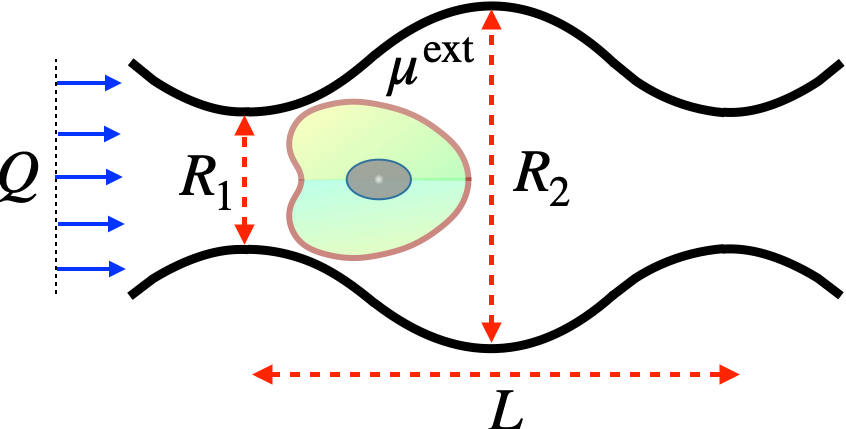

**(c) Lissajous Figures for Maxwell fluid**

clc; clear;
syms AP BP CP DP A B C D alpha a b c r U1 Lambda1 LambdaP1 s tau etas omega

% radial and tangential velocity component of Stokes equation, for n=2; 
% see equation A5 and A6 in AppendixA in the main text.
vpr = -(AP + BP/r^3 + CP *r^2 + DP/r);
vptheta = AP - BP/(2*r^3) + 2* CP * r^2 + DP/(2*r);

vr_out =-( A + B/r^3 + C * r^2) ;
vtheta_out = A - B/(2* r^3)  + 2 * C * r^2 ;

% The (radial and tangential) velocity at r=a, r=b, and r=c:
vpr_a = subs(vpr , r,a);
vptheta_a = subs(vptheta , r ,a);

vpr_b = subs(vpr , r,b);
vptheta_b = subs(vptheta , r ,b);

vr_out_b = subs(vr_out , r,b);
vtheta_out_b = subs(vtheta_out , r,b);

vr_out_c = subs(vr_out , r,c);
vtheta_out_c = subs(vtheta_out , r,c);

% Applying BCs as in Eq(1), and Eq(6) of the paper 
% (in moving frame of nuleus)
% see Appendix A for the form of stress and pressure (Eqs. A8-9)
% Note that we use Laplace transform of modes in the Eqs;
% lambda=lambda1*cos(wt) and lambdaP=lambdaP1*cos(wt)
eqns = [ vpr_a == 0 , vptheta_a == 0 , ...
         vr_out_b == vpr_b , vtheta_out_b == vptheta_b , ...
        3*B/b^4 + 3*C*b == (1+ (etas)/(1+ tau*s))* (3*BP/b^4 + 3*CP*b ) , ...
         6*B/b^4 + 6*C*b  == (1 + (etas)/(1+ tau*s)) * ( 6*BP/b^4 + 6*CP*b + 3* DP/(b^2)) , ...
         vr_out_c == (1/s)*(-s*U1 + Lambda1*( s^2/(s^2 + omega^2))) , ... 
         vtheta_out_c == (1/s)*(s*U1 + LambdaP1*( s^2/(s^2 + omega^2)))];

% solving the Equations for uknowns A,B,C,DP,AP,BP,CP, and U1 (nucleus velocity)
S = solve(eqns,A,B,C,DP, AP, BP, CP, U1);

% This part generate the velocity of the nucleus in s-space:
U10 = simplify(S.U1);
% nucleus velocity as a function of time:
U_ve_l=ilaplace(U10);

% Lissajous Figures for Lambda1 = LambdaP1 = cos(wt)
 clc; clear;
 a=1; b=2; c=3;             % geometrical parameters 
 Lambda1 =1; LambdaP1 =1;   % first surface velocity modes
 tau =1;                    % relaxation time
 etas = 10;                 % relative viscosity
 t = 10:0.01:100; 
 OMEGA = [0.1,0.5,1,5,10,50]; % these are the frequencies
 k=0;
 for omega = OMEGA 
 k = k+1;
 % nucleus velocity for periodic surface velocity modes
 % (calculated from previous part)
 fun = - (50*LambdaP1*a^10*b^10*cos(omega*t) - 25*Lambda1*a^10*b^10*cos(omega*t) - 150*Lambda1*b^10*c^10*cos(omega*t) - 75*LambdaP1*b^10*c^10*cos(omega*t) - 9*Lambda1*b^20*etas^2*cos(omega*t) + 18*LambdaP1*b^20*etas^2*cos(omega*t) - 30*Lambda1*a^5*b^15*etas*cos(omega*t) - 20*Lambda1*a^10*b^10*etas*cos(omega*t) + 60*LambdaP1*a^5*b^15*etas*cos(omega*t) + 40*LambdaP1*a^10*b^10*etas*cos(omega*t) - 180*Lambda1*b^10*c^10*etas*cos(omega*t) + 75*Lambda1*b^12*c^8*etas*cos(omega*t) + 105*Lambda1*b^15*c^5*etas*cos(omega*t) - 90*LambdaP1*b^10*c^10*etas*cos(omega*t) + 75*LambdaP1*b^12*c^8*etas*cos(omega*t) + 15*LambdaP1*b^15*c^5*etas*cos(omega*t) + 125*Lambda1*a^2*b^10*c^8*cos(omega*t) + 175*Lambda1*a^5*b^10*c^5*cos(omega*t) - 125*Lambda1*a^7*b^10*c^3*cos(omega*t) + 125*LambdaP1*a^2*b^10*c^8*cos(omega*t) + 25*LambdaP1*a^5*b^10*c^5*cos(omega*t) - 125*LambdaP1*a^7*b^10*c^3*cos(omega*t) - 12*Lambda1*a^5*b^15*etas^2*cos(omega*t) - 4*Lambda1*a^10*b^10*etas^2*cos(omega*t) + 24*LambdaP1*a^5*b^15*etas^2*cos(omega*t) + 8*LambdaP1*a^10*b^10*etas^2*cos(omega*t) - 24*Lambda1*a^10*c^10*etas^2*cos(omega*t) - 12*LambdaP1*a^10*c^10*etas^2*cos(omega*t) - 54*Lambda1*b^10*c^10*etas^2*cos(omega*t) + 45*Lambda1*b^12*c^8*etas^2*cos(omega*t) + 63*Lambda1*b^15*c^5*etas^2*cos(omega*t) - 45*Lambda1*b^17*c^3*etas^2*cos(omega*t) - 27*LambdaP1*b^10*c^10*etas^2*cos(omega*t) + 45*LambdaP1*b^12*c^8*etas^2*cos(omega*t) + 9*LambdaP1*b^15*c^5*etas^2*cos(omega*t) - 45*LambdaP1*b^17*c^3*etas^2*cos(omega*t) - 72*Lambda1*a^5*b^5*c^10*etas^2*cos(omega*t) + 60*Lambda1*a^5*b^7*c^8*etas^2*cos(omega*t) + 84*Lambda1*a^5*b^10*c^5*etas^2*cos(omega*t) - 60*Lambda1*a^5*b^12*c^3*etas^2*cos(omega*t) + 20*Lambda1*a^10*b^2*c^8*etas^2*cos(omega*t) + 28*Lambda1*a^10*b^5*c^5*etas^2*cos(omega*t) - 20*Lambda1*a^10*b^7*c^3*etas^2*cos(omega*t) - 36*LambdaP1*a^5*b^5*c^10*etas^2*cos(omega*t) + 60*LambdaP1*a^5*b^7*c^8*etas^2*cos(omega*t) + 12*LambdaP1*a^5*b^10*c^5*etas^2*cos(omega*t) - 60*LambdaP1*a^5*b^12*c^3*etas^2*cos(omega*t) + 20*LambdaP1*a^10*b^2*c^8*etas^2*cos(omega*t) + 4*LambdaP1*a^10*b^5*c^5*etas^2*cos(omega*t) - 20*LambdaP1*a^10*b^7*c^3*etas^2*cos(omega*t) - 25*Lambda1*a^10*b^10*omega^2*tau^2*cos(omega*t) + 50*LambdaP1*a^10*b^10*omega^2*tau^2*cos(omega*t) - 150*Lambda1*b^10*c^10*omega^2*tau^2*cos(omega*t) - 75*LambdaP1*b^10*c^10*omega^2*tau^2*cos(omega*t) + 75*Lambda1*a^2*b^10*c^8*etas*cos(omega*t) - 75*Lambda1*a^2*b^15*c^3*etas*cos(omega*t) - 120*Lambda1*a^5*b^5*c^10*etas*cos(omega*t) + 50*Lambda1*a^5*b^7*c^8*etas*cos(omega*t) + 175*Lambda1*a^5*b^10*c^5*etas*cos(omega*t) - 75*Lambda1*a^5*b^12*c^3*etas*cos(omega*t) + 50*Lambda1*a^7*b^5*c^8*etas*cos(omega*t) - 50*Lambda1*a^7*b^10*c^3*etas*cos(omega*t) + 70*Lambda1*a^10*b^5*c^5*etas*cos(omega*t) - 50*Lambda1*a^10*b^7*c^3*etas*cos(omega*t) + 75*LambdaP1*a^2*b^10*c^8*etas*cos(omega*t) - 75*LambdaP1*a^2*b^15*c^3*etas*cos(omega*t) - 60*LambdaP1*a^5*b^5*c^10*etas*cos(omega*t) + 50*LambdaP1*a^5*b^7*c^8*etas*cos(omega*t) + 25*LambdaP1*a^5*b^10*c^5*etas*cos(omega*t) - 75*LambdaP1*a^5*b^12*c^3*etas*cos(omega*t) + 50*LambdaP1*a^7*b^5*c^8*etas*cos(omega*t) - 50*LambdaP1*a^7*b^10*c^3*etas*cos(omega*t) + 10*LambdaP1*a^10*b^5*c^5*etas*cos(omega*t) - 50*LambdaP1*a^10*b^7*c^3*etas*cos(omega*t) + 75*Lambda1*b^12*c^8*etas*omega*tau*sin(omega*t) - 75*Lambda1*b^15*c^5*etas*omega*tau*sin(omega*t) + 75*LambdaP1*b^12*c^8*etas*omega*tau*sin(omega*t) - 75*LambdaP1*b^15*c^5*etas*omega*tau*sin(omega*t) + 125*Lambda1*a^2*b^10*c^8*omega^2*tau^2*cos(omega*t) + 175*Lambda1*a^5*b^10*c^5*omega^2*tau^2*cos(omega*t) - 125*Lambda1*a^7*b^10*c^3*omega^2*tau^2*cos(omega*t) + 125*LambdaP1*a^2*b^10*c^8*omega^2*tau^2*cos(omega*t) + 25*LambdaP1*a^5*b^10*c^5*omega^2*tau^2*cos(omega*t) - 125*LambdaP1*a^7*b^10*c^3*omega^2*tau^2*cos(omega*t) - 75*Lambda1*a^2*b^10*c^8*etas*omega*tau*sin(omega*t) + 75*Lambda1*a^2*b^15*c^3*etas*omega*tau*sin(omega*t) + 50*Lambda1*a^5*b^7*c^8*etas*omega*tau*sin(omega*t) + 25*Lambda1*a^5*b^10*c^5*etas*omega*tau*sin(omega*t) - 75*Lambda1*a^5*b^12*c^3*etas*omega*tau*sin(omega*t) - 50*Lambda1*a^7*b^5*c^8*etas*omega*tau*sin(omega*t) + 50*Lambda1*a^7*b^10*c^3*etas*omega*tau*sin(omega*t) + 50*Lambda1*a^10*b^5*c^5*etas*omega*tau*sin(omega*t) - 50*Lambda1*a^10*b^7*c^3*etas*omega*tau*sin(omega*t) - 75*LambdaP1*a^2*b^10*c^8*etas*omega*tau*sin(omega*t) + 75*LambdaP1*a^2*b^15*c^3*etas*omega*tau*sin(omega*t) + 50*LambdaP1*a^5*b^7*c^8*etas*omega*tau*sin(omega*t) + 25*LambdaP1*a^5*b^10*c^5*etas*omega*tau*sin(omega*t) - 75*LambdaP1*a^5*b^12*c^3*etas*omega*tau*sin(omega*t) - 50*LambdaP1*a^7*b^5*c^8*etas*omega*tau*sin(omega*t) + 50*LambdaP1*a^7*b^10*c^3*etas*omega*tau*sin(omega*t) + 50*LambdaP1*a^10*b^5*c^5*etas*omega*tau*sin(omega*t) - 50*LambdaP1*a^10*b^7*c^3*etas*omega*tau*sin(omega*t))/(3*(4*a^10*b^10*etas^2 + 20*a^10*b^10*etas + 25*a^10*b^10*omega^2*tau^2 + 25*a^10*b^10 - 8*a^10*b^5*c^5*etas^2 - 20*a^10*b^5*c^5*etas + 4*a^10*c^10*etas^2 + 12*a^5*b^15*etas^2 + 30*a^5*b^15*etas - 24*a^5*b^10*c^5*etas^2 - 50*a^5*b^10*c^5*etas - 50*a^5*b^10*c^5*omega^2*tau^2 - 50*a^5*b^10*c^5 + 12*a^5*b^5*c^10*etas^2 + 20*a^5*b^5*c^10*etas + 9*b^20*etas^2 - 18*b^15*c^5*etas^2 - 30*b^15*c^5*etas + 9*b^10*c^10*etas^2 + 30*b^10*c^10*etas + 25*b^10*c^10*omega^2*tau^2 + 25*b^10*c^10)) - (5*c^3*etas*exp(-(t*(3*b^10*etas + 5*a^5*b^5 - 5*b^5*c^5 + 2*a^5*b^5*etas - 2*a^5*c^5*etas - 3*b^5*c^5*etas))/(5*b^5*tau*(a^5 - c^5)))*(a - c)*(b - c)*(Lambda1 + LambdaP1)*(2*a^6 - 2*a^5*b + 3*a*b^5 - 3*b^6)*(3*b^10*etas + 5*a^5*b^5 - 5*b^5*c^5 + 2*a^5*b^5*etas - 2*a^5*c^5*etas - 3*b^5*c^5*etas)*(a^3*b + a^3*c + a^2*b^2 + 2*a^2*b*c + a^2*c^2 + a*b^3 + 2*a*b^2*c + 2*a*b*c^2 + a*c^3 + b^3*c + b^2*c^2 + b*c^3))/(3*(a^5 - c^5)*(4*a^10*b^10*etas^2 + 20*a^10*b^10*etas + 25*a^10*b^10*omega^2*tau^2 + 25*a^10*b^10 - 8*a^10*b^5*c^5*etas^2 - 20*a^10*b^5*c^5*etas + 4*a^10*c^10*etas^2 + 12*a^5*b^15*etas^2 + 30*a^5*b^15*etas - 24*a^5*b^10*c^5*etas^2 - 50*a^5*b^10*c^5*etas - 50*a^5*b^10*c^5*omega^2*tau^2 - 50*a^5*b^10*c^5 + 12*a^5*b^5*c^10*etas^2 + 20*a^5*b^5*c^10*etas + 9*b^20*etas^2 - 18*b^15*c^5*etas^2 - 30*b^15*c^5*etas + 9*b^10*c^10*etas^2 + 30*b^10*c^10*etas + 25*b^10*c^10*omega^2*tau^2 + 25*b^10*c^10));
 subplot(2,3,k)
 plot(cos(omega*t),fun,'linewidth',3);% hold on; drawnow;
 %caxis;
 axis([-1,1,-1,1]);
 end


## ***3- Nucleus inside a porous medium*** 

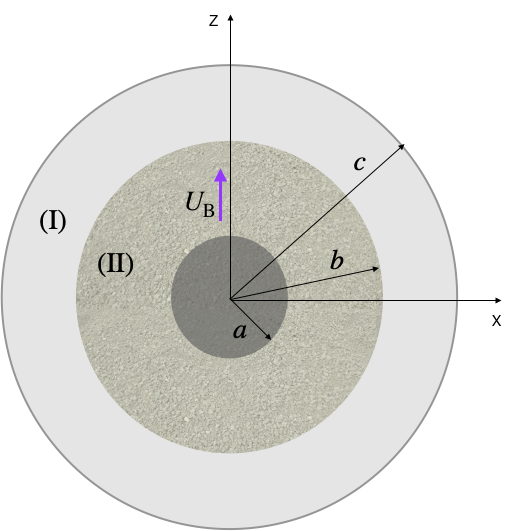

%%%%%%%%%%%%%%% Brinkman fluid %%%%%%%%%%%%%%%%
clc; clear;
syms AP BP CP DP A B C D alpha a b c r U2 U1 Lambda1 LambdaP1 s s1

% creating functions y,Y(alpha*r); see Eq.16 in the main text
y = (alpha)* cosh(alpha * r) - (1/r) * (sinh(alpha * r));
Y = (alpha)* sinh(alpha * r) - (1/r) * (cosh(alpha * r));

% first and second derivatives of functions y and Y w.r.t. r:
dy = diff(y,r);
d2y = diff(y,r,2);
dY = diff(Y,r);
d2Y = diff(Y,r,2);

% radial and tangential velocity component of Stokes equation, for n=2; 
% see equation A5 and A6 in AppendixA in the main text.
vpr = AP + BP/r^3 + (CP/r^2)* y + (DP/r^2)* Y;
vptheta = AP - BP/(2*r^3) + (CP/(2*r))* dy + (DP/(2*r))* dY;

vr_out = A + B/r^3 + C * r^2 ;
vtheta_out = A - B/(2* r^3)  + 2 * C * r^2 ;

% see Appendix A for the form of pressure (Eqs. A9 and A17)
p_in = (alpha)^2*(AP*r - BP/(2*r^2));
p_out = -10*C*r;

% see Appendix A for the form of stress (Eqs. A8 and A18)
sigma_rtheta_in = 2*(3*BP/r^4 + (CP/(2*r^3))*(2*y-2*r*dy + r^2*d2y)...
                        + (DP/(2*r^3))*(2*Y-2*r*dY + r^2*d2Y) );
sigma_rtheta_out = 2*(3*B/r^4 + 3*C*r);

% The (radial and tangential) velocities, 
% pressure, and tengential stress at r=a, r=b, and r=c:
vpr_a = subs(vpr , r,a);
vptheta_a = subs(vptheta , r ,a);

vpr_b = subs(vpr , r,b);
vptheta_b = subs(vptheta , r ,b);

p_in_b = subs(p_in,r,b);
p_out_b = subs(p_out,r,b);

sigma_rtheta_in_b = simplify(subs(sigma_rtheta_in,r,b));
sigma_rtheta_out_b = simplify(subs(sigma_rtheta_out,r,b));

vr_out_b = subs(vr_out , r,b);
vtheta_out_b = subs(vtheta_out , r,b);

vr_out_c = subs(vr_out , r,c);
vtheta_out_c = subs(vtheta_out , r,c);

% Applying BCs as in Eq(1), and Eq(6) of the main text 
% (in moving frame of nuleus)
eqns = [ vpr_a == 0 , vptheta_a == 0 , ...
         vr_out_b == vpr_b , vtheta_out_b == vptheta_b , ...
         sigma_rtheta_in_b == sigma_rtheta_out_b , ...
         p_in_b == p_out_b , ...
         vr_out_c == (U1 - Lambda1) , ...
         vtheta_out_c == (U1 + LambdaP1)   ];

% solving the Equations for uknowns 
% A,B,C,DP,AP,BP,CP, and U1 (nucleus velocity)
S = solve(eqns,A,B,C,DP, AP, BP, CP, U1);
A0 = S.A; B0 = S.B; C0 = S.C; U10 = S.U1;
AP0 = S.AP; BP0 = S.BP; CP0 = S.CP; DP0 = S.DP;

% velocity of the nucleus in porous medium
U_B = simplify(U10);

% plot of U_B Brinkman Vs alpha
clc; clear;
a = 1;  c = 3;              % geometrical parameters 
Lambda1 = 1; LambdaP1 = 1;  % first surface velocity modes
alpha = 0.01:0.1:10;        % different values for (inverse) permeability
B = 1:0.5:3;                % the values for the porous shell radius, b

for b = B   
% Velocity of the nucleus in Brinkman fluid (U_B) 
U =  (135.*Lambda1.*a.*b.^3.*sinh(alpha.*(a - b)) - 270.*LambdaP1.*a.*b.^3.*sinh(alpha.*(a - b)) + 405.*U1.*a.*b.^3.*sinh(alpha.*(a - b)) - 60.*Lambda1.*a.*alpha.^3.*b.^6 + 120.*LambdaP1.*a.*alpha.^3.*b.^6 - 180.*U1.*a.*alpha.^3.*b.^6 + 30.*Lambda1.*alpha.^3.*b.^7.*cosh(alpha.*(a - b)) + 2.*Lambda1.*alpha.^5.*b.^9.*cosh(alpha.*(a - b)) - 60.*LambdaP1.*alpha.^3.*b.^7.*cosh(alpha.*(a - b)) - 4.*LambdaP1.*alpha.^5.*b.^9.*cosh(alpha.*(a - b)) + 90.*U1.*alpha.^3.*b.^7.*cosh(alpha.*(a - b)) + 6.*U1.*alpha.^5.*b.^9.*cosh(alpha.*(a - b)) + 30.*Lambda1.*alpha.^2.*b.^6.*sinh(alpha.*(a - b)) + 12.*Lambda1.*alpha.^4.*b.^8.*sinh(alpha.*(a - b)) - 60.*LambdaP1.*alpha.^2.*b.^6.*sinh(alpha.*(a - b)) - 24.*LambdaP1.*alpha.^4.*b.^8.*sinh(alpha.*(a - b)) + 90.*U1.*alpha.^2.*b.^6.*sinh(alpha.*(a - b)) + 36.*U1.*alpha.^4.*b.^8.*sinh(alpha.*(a - b)) - 135.*Lambda1.*a.^2.*alpha.*b.^3.*cosh(alpha.*(a - b)) + 3.*Lambda1.*a.*alpha.^3.*b.^6.*cosh(alpha.*(a - b)) + 270.*LambdaP1.*a.^2.*alpha.*b.^3.*cosh(alpha.*(a - b)) - 6.*LambdaP1.*a.*alpha.^3.*b.^6.*cosh(alpha.*(a - b)) - 405.*U1.*a.^2.*alpha.*b.^3.*cosh(alpha.*(a - b)) + 9.*U1.*a.*alpha.^3.*b.^6.*cosh(alpha.*(a - b)) + 18.*Lambda1.*a.*alpha.^2.*b.^5.*sinh(alpha.*(a - b)) - 36.*LambdaP1.*a.*alpha.^2.*b.^5.*sinh(alpha.*(a - b)) - 18.*Lambda1.*a.*alpha.^2.*c.^5.*sinh(alpha.*(a - b)) - 9.*LambdaP1.*a.*alpha.^2.*c.^5.*sinh(alpha.*(a - b)) + 54.*U1.*a.*alpha.^2.*b.^5.*sinh(alpha.*(a - b)) - 9.*U1.*a.*alpha.^2.*c.^5.*sinh(alpha.*(a - b)) - 30.*Lambda1.*a.*alpha.^3.*b.^3.*c.^3 - 30.*LambdaP1.*a.*alpha.^3.*b.^3.*c.^3 - 18.*Lambda1.*a.^2.*alpha.^3.*b.^5.*cosh(alpha.*(a - b)) + 45.*Lambda1.*a.^3.*alpha.^3.*b.^4.*cosh(alpha.*(a - b)) + Lambda1.*a.^3.*alpha.^5.*b.^6.*cosh(alpha.*(a - b)) + 36.*LambdaP1.*a.^2.*alpha.^3.*b.^5.*cosh(alpha.*(a - b)) - 90.*LambdaP1.*a.^3.*alpha.^3.*b.^4.*cosh(alpha.*(a - b)) - 2.*LambdaP1.*a.^3.*alpha.^5.*b.^6.*cosh(alpha.*(a - b)) + 18.*Lambda1.*a.^2.*alpha.^3.*c.^5.*cosh(alpha.*(a - b)) + 9.*LambdaP1.*a.^2.*alpha.^3.*c.^5.*cosh(alpha.*(a - b)) + 60.*Lambda1.*alpha.^3.*b.^4.*c.^3.*cosh(alpha.*(a - b)) - 12.*Lambda1.*alpha.^5.*b.^4.*c.^5.*cosh(alpha.*(a - b)) + 10.*Lambda1.*alpha.^5.*b.^6.*c.^3.*cosh(alpha.*(a - b)) + 60.*LambdaP1.*alpha.^3.*b.^4.*c.^3.*cosh(alpha.*(a - b)) - 6.*LambdaP1.*alpha.^5.*b.^4.*c.^5.*cosh(alpha.*(a - b)) + 10.*LambdaP1.*alpha.^5.*b.^6.*c.^3.*cosh(alpha.*(a - b)) - 54.*U1.*a.^2.*alpha.^3.*b.^5.*cosh(alpha.*(a - b)) + 135.*U1.*a.^3.*alpha.^3.*b.^4.*cosh(alpha.*(a - b)) + 3.*U1.*a.^3.*alpha.^5.*b.^6.*cosh(alpha.*(a - b)) + 9.*U1.*a.^2.*alpha.^3.*c.^5.*cosh(alpha.*(a - b)) - 6.*U1.*alpha.^5.*b.^4.*c.^5.*cosh(alpha.*(a - b)) - 135.*Lambda1.*a.^2.*alpha.^2.*b.^4.*sinh(alpha.*(a - b)) + 45.*Lambda1.*a.^3.*alpha.^2.*b.^3.*sinh(alpha.*(a - b)) - 3.*Lambda1.*a.^2.*alpha.^4.*b.^6.*sinh(alpha.*(a - b)) + 6.*Lambda1.*a.^3.*alpha.^4.*b.^5.*sinh(alpha.*(a - b)) + 270.*LambdaP1.*a.^2.*alpha.^2.*b.^4.*sinh(alpha.*(a - b)) - 90.*LambdaP1.*a.^3.*alpha.^2.*b.^3.*sinh(alpha.*(a - b)) + 6.*LambdaP1.*a.^2.*alpha.^4.*b.^6.*sinh(alpha.*(a - b)) - 12.*LambdaP1.*a.^3.*alpha.^4.*b.^5.*sinh(alpha.*(a - b)) - 6.*Lambda1.*a.^3.*alpha.^4.*c.^5.*sinh(alpha.*(a - b)) - 3.*LambdaP1.*a.^3.*alpha.^4.*c.^5.*sinh(alpha.*(a - b)) + 60.*Lambda1.*alpha.^2.*b.^3.*c.^3.*sinh(alpha.*(a - b)) - 12.*Lambda1.*alpha.^4.*b.^3.*c.^5.*sinh(alpha.*(a - b)) + 30.*Lambda1.*alpha.^4.*b.^5.*c.^3.*sinh(alpha.*(a - b)) + 60.*LambdaP1.*alpha.^2.*b.^3.*c.^3.*sinh(alpha.*(a - b)) - 6.*LambdaP1.*alpha.^4.*b.^3.*c.^5.*sinh(alpha.*(a - b)) + 30.*LambdaP1.*alpha.^4.*b.^5.*c.^3.*sinh(alpha.*(a - b)) - 405.*U1.*a.^2.*alpha.^2.*b.^4.*sinh(alpha.*(a - b)) + 135.*U1.*a.^3.*alpha.^2.*b.^3.*sinh(alpha.*(a - b)) - 9.*U1.*a.^2.*alpha.^4.*b.^6.*sinh(alpha.*(a - b)) + 18.*U1.*a.^3.*alpha.^4.*b.^5.*sinh(alpha.*(a - b)) - 3.*U1.*a.^3.*alpha.^4.*c.^5.*sinh(alpha.*(a - b)) - 6.*U1.*alpha.^4.*b.^3.*c.^5.*sinh(alpha.*(a - b)) + 135.*Lambda1.*a.*alpha.*b.^4.*cosh(alpha.*(a - b)) - 270.*LambdaP1.*a.*alpha.*b.^4.*cosh(alpha.*(a - b)) + 405.*U1.*a.*alpha.*b.^4.*cosh(alpha.*(a - b)) - 3.*U1.*a.^3.*alpha.^5.*b.*c.^5.*cosh(alpha.*(a - b)) + 45.*Lambda1.*a.*alpha.^2.*b.^2.*c.^3.*sinh(alpha.*(a - b)) + 18.*Lambda1.*a.^2.*alpha.^4.*b.*c.^5.*sinh(alpha.*(a - b)) + 45.*LambdaP1.*a.*alpha.^2.*b.^2.*c.^3.*sinh(alpha.*(a - b)) + 9.*LambdaP1.*a.^2.*alpha.^4.*b.*c.^5.*sinh(alpha.*(a - b)) + 9.*U1.*a.^2.*alpha.^4.*b.*c.^5.*sinh(alpha.*(a - b)) - 45.*Lambda1.*a.^2.*alpha.^3.*b.^2.*c.^3.*cosh(alpha.*(a - b)) + 5.*Lambda1.*a.^3.*alpha.^5.*b.^3.*c.^3.*cosh(alpha.*(a - b)) - 45.*LambdaP1.*a.^2.*alpha.^3.*b.^2.*c.^3.*cosh(alpha.*(a - b)) + 5.*LambdaP1.*a.^3.*alpha.^5.*b.^3.*c.^3.*cosh(alpha.*(a - b)) - 15.*Lambda1.*a.^2.*alpha.^4.*b.^3.*c.^3.*sinh(alpha.*(a - b)) + 15.*Lambda1.*a.^3.*alpha.^4.*b.^2.*c.^3.*sinh(alpha.*(a - b)) - 15.*LambdaP1.*a.^2.*alpha.^4.*b.^3.*c.^3.*sinh(alpha.*(a - b)) + 15.*LambdaP1.*a.^3.*alpha.^4.*b.^2.*c.^3.*sinh(alpha.*(a - b)) - 18.*Lambda1.*a.*alpha.^3.*b.*c.^5.*cosh(alpha.*(a - b)) - 9.*LambdaP1.*a.*alpha.^3.*b.*c.^5.*cosh(alpha.*(a - b)) - 9.*U1.*a.*alpha.^3.*b.*c.^5.*cosh(alpha.*(a - b)) + 15.*Lambda1.*a.*alpha.^3.*b.^3.*c.^3.*cosh(alpha.*(a - b)) - 6.*Lambda1.*a.^3.*alpha.^5.*b.*c.^5.*cosh(alpha.*(a - b)) + 15.*LambdaP1.*a.*alpha.^3.*b.^3.*c.^3.*cosh(alpha.*(a - b)) - 3.*LambdaP1.*a.^3.*alpha.^5.*b.*c.^5.*cosh(alpha.*(a - b)))./(3.*(135.*a.*b.^3.*sinh(alpha.*(a - b)) - 60.*a.*alpha.^3.*b.^6 + 30.*alpha.^3.*b.^7.*cosh(alpha.*(a - b)) + 2.*alpha.^5.*b.^9.*cosh(alpha.*(a - b)) + 30.*alpha.^2.*b.^6.*sinh(alpha.*(a - b)) + 12.*alpha.^4.*b.^8.*sinh(alpha.*(a - b)) - 18.*a.^2.*alpha.^3.*b.^5.*cosh(alpha.*(a - b)) + 45.*a.^3.*alpha.^3.*b.^4.*cosh(alpha.*(a - b)) + a.^3.*alpha.^5.*b.^6.*cosh(alpha.*(a - b)) + 3.*a.^2.*alpha.^3.*c.^5.*cosh(alpha.*(a - b)) - 2.*alpha.^5.*b.^4.*c.^5.*cosh(alpha.*(a - b)) - 135.*a.^2.*alpha.^2.*b.^4.*sinh(alpha.*(a - b)) + 45.*a.^3.*alpha.^2.*b.^3.*sinh(alpha.*(a - b)) - 3.*a.^2.*alpha.^4.*b.^6.*sinh(alpha.*(a - b)) + 6.*a.^3.*alpha.^4.*b.^5.*sinh(alpha.*(a - b)) - a.^3.*alpha.^4.*c.^5.*sinh(alpha.*(a - b)) - 2.*alpha.^4.*b.^3.*c.^5.*sinh(alpha.*(a - b)) + 135.*a.*alpha.*b.^4.*cosh(alpha.*(a - b)) - 135.*a.^2.*alpha.*b.^3.*cosh(alpha.*(a - b)) + 3.*a.*alpha.^3.*b.^6.*cosh(alpha.*(a - b)) + 18.*a.*alpha.^2.*b.^5.*sinh(alpha.*(a - b)) - 3.*a.*alpha.^2.*c.^5.*sinh(alpha.*(a - b)) - 3.*a.*alpha.^3.*b.*c.^5.*cosh(alpha.*(a - b)) - a.^3.*alpha.^5.*b.*c.^5.*cosh(alpha.*(a - b)) + 3.*a.^2.*alpha.^4.*b.*c.^5.*sinh(alpha.*(a - b))));

plot(alpha,U,'linewidth',4);hold on;
legend('b = 1','b = 1.5','b = 2','b = 2.5','b = 3')

end

### **(a) Porous shell with variable permeability**


$$\eta_{\circ} {\nabla}^2 \mathbf{v} -  \eta_{\circ} \, \frac{{{\alpha}_{\circ}}^2 }{ r^2} \,\mathbf{v}   - \nabla p =0$$



clc; clear;
syms AP BP CP DP A B C D alpha0 a b c r n U0 U1 Lambda1 LambdaP1 U2 m1 m2 m3 m4

a=1; b=2; c=3;             % geometrical parameters 
Lambda1 =1; LambdaP1 =1;   % first surface velocity modes
%alpha0 = 0;               % (inverse) permeability  

% radial and tangential velocity component of Stokes equation, for n=2; 
% see equation A5 and A6 in AppendixA in the main text.
vr_out =   A  + B * r^(-3) + C * r^2  ; 
vtheta_out =  A  - B/(2*r^3) + 2* C * r^2  ; 

% see Appendix A for the form of 
% pressure and tangential stress (Eqs. A8,9 and A17,18)
p_out = 10 * C*r; 
sigma_rtheta_out = 3* B * r^(-4) + 3* C*r  ;

% The (radial and tangential) velocities, 
% pressure, and tengential stress at r=a, r=b, and r=c:
vr_out_b = subs(vr_out ,r,b);
vtheta_out_b = subs(vtheta_out ,r,b);
vr_out_c = subs(vr_out ,r,c);
vtheta_out_c = subs(vtheta_out ,r,c);
p_out_b = subs(p_out ,r,b);
sigma_rtheta_out_b = subs(sigma_rtheta_out ,r,b);

% We use the stream function solution of Stokes equation 
% for variable permeability; Eqs.23A-26A in Appendix A
m1 = (1/2)*(3+ sqrt(13+ 2* (alpha0)^2 -2*sqrt((alpha0)^4 -4* (alpha0)^2 +36) ) );
m2 = (1/2)*(3- sqrt(13+ 2* (alpha0)^2 +2*sqrt((alpha0)^4 -4* (alpha0)^2 +36) ) );
m3 = (1/2)*(3+ sqrt(13+ 2* (alpha0)^2 +2*sqrt((alpha0)^4 -4* (alpha0)^2 +36) ) );
m4 = (1/2)*(3- sqrt(13+ 2* (alpha0)^2 -2*sqrt((alpha0)^4 -4* (alpha0)^2 +36) ) );

vr_in =   AP * r^(m1 -2) + BP * r^(m2 -2) +  CP * r^(m3 -2) + DP * r^(m4 -2) ;
vtheta_in =  (1/2)* ( m1* AP * r^(m1 -2) + m2* BP * r^(m2 -2) + m3* CP * r^(m3 -2)+ m4* DP * r^(m4 -2) );

p_in = (((m1)^2 -m1 -2 - (alpha0)^2)/(m1 -3)) *AP * r^(m1 -3) + (((m2)^2 -m2 -2 - (alpha0)^2)/(m2 -3)) *BP * r^(m2 -3) ...
       +(((m3)^2 -m3 -2 - (alpha0)^2)/(m3 -3)) *CP * r^(m3 -3) + (((m4)^2 -m4 -2 - (alpha0)^2)/(m4 -3)) *DP * r^(m4 -3) ;

sigma_rtheta_in = (1/2)*(  ((m1)^2 -3* m1 +2)*AP * r^(m1 -3) + ((m2)^2 -3* m2 +2)*BP * r^(m2 -3) + ...
                          + ((m3)^2 -3* m3 +2)*CP * r^(m3 -3) + ((m4)^2 -3* m4 +2)*DP * r^(m4 -3) );

% The (radial and tangential) velocities, 
% pressure, and tengential stress at r=a, r=b, and r=c:
vr_in_a = subs(vr_in,r,a);
vtheta_in_a = subs(vtheta_in , r,a);
vr_in_b = subs(vr_in,r,b);
vtheta_in_b = subs(vtheta_in , r,b);

p_in_b = subs(p_in ,r,b);
sigma_rtheta_in_b = subs(sigma_rtheta_in ,r,b);

% Applying BCs as in Eq(1), and Eq(6) of the main text 
% (in moving frame of nuleus)
eqns = [ vr_in_a == 0 , vtheta_in_a == 0 , ...
         vr_in_b == vr_out_b , vtheta_in_b == vtheta_out_b , ...
         p_in_b == p_out_b , ...
         sigma_rtheta_in_b == sigma_rtheta_out_b , ...
         vr_out_c ==  (U1 - Lambda1) , ...
         vtheta_out_c == (U1  + LambdaP1)  ];

% solving the Equations for uknowns 
% A,B,C,DP,AP,BP,CP, and U1 (nucleus velocity)
S = solve(eqns,A,B,C,U1,AP, BP, CP, DP);
A0 = S.A; B0 = S.B; C0 = S.C; U10 = S.U1;  
AP0 = S.AP; BP0 = S.BP; CP0 = S.CP; DP0 = S.DP;

% nucleus velocity for variable permeability case:
U_Bvp = simplify(U10);

%%%%%%% plot U_B with variable permeability %%%%%%%
clear; clc;
colormap(linspecer);
set(0,'DefaultFigureColormap',linspecer);
set(0,'DefaultAxesColorOrder',linspecer(5))
set(0,'DefaultLineLineWidth',4)
a = 1;  c = 3;              % geometrical parameters 
Lambda1 = 1; LambdaP1 = 1;  % first surface velocity modes
alpha = 0.01:0.1:50;        % (inverse) permeability
alpha0 = 0.01:0.1:50;
 B = 1:0.5:3;

for b = B 
    % nucleus velocity for variable permeability
    U1a = (566433.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(3/2) - 984150.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) + 566433.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(3/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) + 15309.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(5/2) - 183708.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(3/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(3/2) + 15309.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(5/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) + 2187.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(3/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(5/2) + 2187.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(5/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(3/2) - 100776960.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)) + 100776960.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)) + 100776960.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)) - 36391680.*alpha0.^2.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)) - 36391680.*alpha0.^2.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)) + 5598720.*alpha0.^4.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)) + 5598720.*alpha0.^4.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)) - 699840.*alpha0.^6.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)) - 699840.*alpha0.^6.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)) + 36391680.*alpha0.^2 - 5598720.*alpha0.^4 + 699840.*alpha0.^6 - 46080.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^5 - 46080.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^5 + 46080.*b.^5 - 11962890.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2) + 11962890.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) + 1076004.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(3/2) - 1076004.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(3/2) + 69984.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(3/2).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2) - 69984.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(3/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) - 30618.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(5/2) + 30618.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(5/2) - 57063204.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2) + 57063204.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) + 57063204.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2) - 57063204.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) + 6840936.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(3/2) - 6840936.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(3/2) - 6840936.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(3/2) + 6840936.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(3/2) - 166212.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(5/2) + 166212.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(5/2) + 166212.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(5/2) - 166212.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(5/2) - 57063204.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2) - 57063204.*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) + 6840936.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(3/2) + 6840936.*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(3/2) - 166212.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(5/2) - 166212.*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(5/2) - 6773760.*alpha0.^2.*b.^2 + 2868480.*alpha0.^4.*b.^2 - 83200.*alpha0.^2.*b.^5 - 293760.*alpha0.^6.*b.^2 + 8960.*alpha0.^4.*b.^5 + 2240.*alpha0.^6.*b.^5 + 835434.*alpha0.^2.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2) + 835434.*alpha0.^2.*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) + 8748.*alpha0.^2.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(3/2) + 8748.*alpha0.^2.*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(3/2) - 332424.*alpha0.^4.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2) - 332424.*alpha0.^4.*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) - 4374.*alpha0.^2.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(5/2) - 4374.*alpha0.^2.*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(5/2) + 52488.*alpha0.^4.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(3/2) + 52488.*alpha0.^4.*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(3/2) + 69984.*alpha0.^6.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2) + 69984.*alpha0.^6.*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) + 243000.*b.^2.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2) + 243000.*b.^2.*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) - 252720.*b.^2.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(3/2) - 252720.*b.^2.*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(3/2) + 21408.*b.^5.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2) + 21408.*b.^5.*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) + 9720.*b.^2.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(5/2) + 9720.*b.^2.*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(5/2) + 1728.*b.^5.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(3/2) + 1728.*b.^5.*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(3/2) - 96.*b.^5.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(5/2) - 96.*b.^5.*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(5/2) + 36391680.*alpha0.^2.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)) - 5598720.*alpha0.^4.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)) + 699840.*alpha0.^6.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)) + 46080.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^5 - 11962890.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2) - 11962890.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) + 11962890.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2) + 11962890.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) + 1076004.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(3/2) + 1076004.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(3/2) + 69984.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*(alpha0.^4 - 4.*alpha0.^2 + 36).^(3/2).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2) + 69984.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*(alpha0.^4 - 4.*alpha0.^2 + 36).^(3/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) - 1076004.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(3/2) - 1076004.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(3/2) - 69984.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*(alpha0.^4 - 4.*alpha0.^2 + 36).^(3/2).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2) - 69984.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*(alpha0.^4 - 4.*alpha0.^2 + 36).^(3/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) - 30618.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(5/2) - 30618.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(5/2) + 30618.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(5/2) + 30618.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(5/2) + 57063204.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2) + 57063204.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) - 6840936.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(3/2) - 6840936.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(3/2) + 166212.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(5/2) + 166212.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(5/2) + 6773760.*alpha0.^2.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^2 + 6773760.*alpha0.^2.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^2 - 2868480.*alpha0.^4.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^2 - 2868480.*alpha0.^4.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^2 + 83200.*alpha0.^2.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^5 + 83200.*alpha0.^2.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^5 + 293760.*alpha0.^6.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^2 + 293760.*alpha0.^6.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^2 - 8960.*alpha0.^4.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^5 - 8960.*alpha0.^4.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^5 - 2240.*alpha0.^6.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^5 - 2240.*alpha0.^6.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^5 + 87480.*alpha0.^2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2) - 87480.*alpha0.^2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) + 52488.*alpha0.^2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(3/2) - 52488.*alpha0.^2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(3/2) + 835434.*alpha0.^2.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2) - 835434.*alpha0.^2.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) - 835434.*alpha0.^2.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2) + 835434.*alpha0.^2.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) + 8748.*alpha0.^2.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(3/2) - 8748.*alpha0.^2.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(3/2) - 8748.*alpha0.^2.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(3/2) + 8748.*alpha0.^2.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(3/2) - 332424.*alpha0.^4.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2) + 332424.*alpha0.^4.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) + 332424.*alpha0.^4.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2) - 332424.*alpha0.^4.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) - 4374.*alpha0.^2.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(5/2) + 4374.*alpha0.^2.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(5/2) + 4374.*alpha0.^2.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(5/2) - 4374.*alpha0.^2.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(5/2) + 52488.*alpha0.^4.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(3/2) - 52488.*alpha0.^4.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(3/2) - 52488.*alpha0.^4.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(3/2) + 52488.*alpha0.^4.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(3/2) + 69984.*alpha0.^6.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2) - 69984.*alpha0.^6.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) - 69984.*alpha0.^6.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2) + 69984.*alpha0.^6.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) - 973620.*b.^2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2) + 973620.*b.^2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) + 42120.*b.^2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(3/2) - 42120.*b.^2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(3/2) + 25920.*b.^2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(3/2).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2) - 25920.*b.^2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(3/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) + 13800.*b.^5.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2) - 13800.*b.^5.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) - 1620.*b.^2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(5/2) + 1620.*b.^2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(5/2) + 432.*b.^5.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(3/2) - 432.*b.^5.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(3/2) - 288.*b.^5.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(3/2).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2) + 288.*b.^5.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(3/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) - 24.*b.^5.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(5/2) + 24.*b.^5.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(5/2) + 243000.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^2.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2) - 243000.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^2.*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) - 243000.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^2.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2) + 243000.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^2.*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) - 252720.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^2.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(3/2) + 252720.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^2.*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(3/2) + 252720.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^2.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(3/2) - 252720.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^2.*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(3/2) + 21408.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^5.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2) - 21408.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^5.*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) - 21408.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^5.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2) + 21408.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^5.*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) + 9720.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^2.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(5/2) - 9720.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^2.*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(5/2) - 9720.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^2.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(5/2) + 9720.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^2.*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(5/2) + 1728.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^5.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(3/2) - 1728.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^5.*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(3/2) - 1728.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^5.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(3/2) + 1728.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^5.*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(3/2) - 96.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^5.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(5/2) + 96.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^5.*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(5/2) + 96.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^5.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(5/2) - 96.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^5.*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(5/2) - 984150.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) - 984150.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) + 566433.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(3/2) + 566433.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(3/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) + 566433.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(3/2) + 566433.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(3/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) + 15309.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(5/2) - 183708.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(3/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(3/2) + 15309.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(5/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) + 15309.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(5/2) - 183708.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(3/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(3/2) + 15309.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(5/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) + 2187.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(3/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(5/2) + 2187.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(5/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(3/2) + 2187.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(3/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(5/2) + 2187.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(5/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(3/2) - 134460.*alpha0.^2.*b.^2.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2) - 134460.*alpha0.^2.*b.^2.*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) + 139320.*alpha0.^2.*b.^2.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(3/2) + 139320.*alpha0.^2.*b.^2.*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(3/2) - 265680.*alpha0.^4.*b.^2.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2) - 265680.*alpha0.^4.*b.^2.*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) - 7788.*alpha0.^2.*b.^5.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2) - 7788.*alpha0.^2.*b.^5.*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) - 4860.*alpha0.^2.*b.^2.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(5/2) - 4860.*alpha0.^2.*b.^2.*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(5/2) + 6480.*alpha0.^4.*b.^2.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(3/2) + 6480.*alpha0.^4.*b.^2.*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(3/2) + 25920.*alpha0.^6.*b.^2.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2) + 25920.*alpha0.^6.*b.^2.*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) + 504.*alpha0.^2.*b.^5.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(3/2) + 504.*alpha0.^2.*b.^5.*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(3/2) - 912.*alpha0.^4.*b.^5.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2) - 912.*alpha0.^4.*b.^5.*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) - 12.*alpha0.^2.*b.^5.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(5/2) - 12.*alpha0.^2.*b.^5.*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(5/2) + 144.*alpha0.^4.*b.^5.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(3/2) + 144.*alpha0.^4.*b.^5.*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(3/2) - 288.*alpha0.^6.*b.^5.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2) - 288.*alpha0.^6.*b.^5.*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) - 2676888.*alpha0.^2.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) + 227448.*alpha0.^2.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(3/2) + 227448.*alpha0.^2.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(3/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) - 8748.*alpha0.^2.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(5/2) - 8748.*alpha0.^2.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(5/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) - 3037500.*b.^2.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) + 290250.*b.^2.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(3/2) + 290250.*b.^2.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(3/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) + 1800.*b.^5.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) - 6750.*b.^2.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(5/2) - 18360.*b.^2.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(3/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(3/2) - 6750.*b.^2.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(5/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) - 1036.*b.^5.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(3/2) - 1036.*b.^5.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(3/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) + 270.*b.^2.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(3/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(5/2) + 270.*b.^2.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(5/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(3/2) + 52.*b.^5.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(5/2) + 176.*b.^5.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(3/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(3/2) + 52.*b.^5.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(5/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) - 4.*b.^5.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(3/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(5/2) - 4.*b.^5.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(5/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(3/2) + 3936600.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)/2).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)/2).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) - 2265732.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)/2).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)/2).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(3/2) - 2265732.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)/2).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)/2).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(3/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) + 78732.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)/2).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)/2).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(5/2) + 454896.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)/2).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)/2).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(3/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(3/2) + 78732.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)/2).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)/2).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(5/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) - 8748.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)/2).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)/2).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(3/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(5/2) - 8748.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)/2).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)/2).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(5/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(3/2) + 11962890.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2) - 11962890.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) - 1076004.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(3/2) + 1076004.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(3/2) - 69984.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*(alpha0.^4 - 4.*alpha0.^2 + 36).^(3/2).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2) + 69984.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*(alpha0.^4 - 4.*alpha0.^2 + 36).^(3/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) + 30618.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(5/2) - 30618.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(5/2) - 6773760.*alpha0.^2.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^2 + 2868480.*alpha0.^4.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^2 - 83200.*alpha0.^2.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^5 - 293760.*alpha0.^6.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^2 + 8960.*alpha0.^4.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^5 + 2240.*alpha0.^6.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^5 + 87480.*alpha0.^2.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2) + 87480.*alpha0.^2.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) - 87480.*alpha0.^2.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2) - 87480.*alpha0.^2.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) + 52488.*alpha0.^2.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(3/2) + 52488.*alpha0.^2.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(3/2) - 52488.*alpha0.^2.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(3/2) - 52488.*alpha0.^2.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(3/2) - 835434.*alpha0.^2.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2) - 835434.*alpha0.^2.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) - 8748.*alpha0.^2.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(3/2) - 8748.*alpha0.^2.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(3/2) + 332424.*alpha0.^4.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2) + 332424.*alpha0.^4.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) + 4374.*alpha0.^2.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(5/2) + 4374.*alpha0.^2.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(5/2) - 52488.*alpha0.^4.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(3/2) - 52488.*alpha0.^4.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(3/2) - 69984.*alpha0.^6.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2) - 69984.*alpha0.^6.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) - 973620.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2) - 973620.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) + 973620.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2) + 973620.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) + 42120.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(3/2) + 42120.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(3/2) + 25920.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(3/2).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2) + 25920.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(3/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) - 42120.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(3/2) - 42120.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(3/2) - 25920.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(3/2).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2) - 25920.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(3/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) + 13800.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^5.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2) + 13800.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^5.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) - 13800.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^5.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2) - 13800.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^5.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) - 1620.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(5/2) - 1620.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(5/2) + 1620.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(5/2) + 1620.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(5/2) + 432.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^5.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(3/2) + 432.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^5.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(3/2) - 288.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^5.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(3/2).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2) - 288.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^5.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(3/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) - 432.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^5.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(3/2) - 432.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^5.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(3/2) + 288.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^5.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(3/2).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2) + 288.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^5.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(3/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) - 24.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^5.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(5/2) - 24.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^5.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(5/2) + 24.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^5.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(5/2) + 24.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^5.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(5/2) - 243000.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^2.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2) - 243000.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^2.*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) + 252720.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^2.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(3/2) + 252720.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^2.*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(3/2) - 21408.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^5.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2) - 21408.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^5.*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) - 9720.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^2.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(5/2) - 9720.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^2.*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(5/2) - 1728.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^5.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(3/2) - 1728.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^5.*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(3/2) + 96.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^5.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(5/2) + 96.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^5.*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(5/2) - 984150.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) + 566433.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(3/2) + 566433.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(3/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) + 15309.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(5/2) - 183708.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(3/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(3/2) + 15309.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(5/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) + 2187.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(3/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(5/2) + 2187.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(5/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(3/2) - 110160.*alpha0.^2.*b.^2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2) + 110160.*alpha0.^2.*b.^2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) + 6480.*alpha0.^2.*b.^2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(3/2) - 6480.*alpha0.^2.*b.^2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(3/2) - 2640.*alpha0.^2.*b.^5.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2) + 2640.*alpha0.^2.*b.^5.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) + 144.*alpha0.^2.*b.^5.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(3/2) - 144.*alpha0.^2.*b.^5.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(3/2) - 134460.*alpha0.^2.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^2.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2) + 134460.*alpha0.^2.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^2.*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) + 134460.*alpha0.^2.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^2.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2) - 134460.*alpha0.^2.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^2.*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) + 139320.*alpha0.^2.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^2.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(3/2) - 139320.*alpha0.^2.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^2.*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(3/2) - 139320.*alpha0.^2.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^2.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(3/2) + 139320.*alpha0.^2.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^2.*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(3/2) - 265680.*alpha0.^4.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^2.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2) + 265680.*alpha0.^4.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^2.*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) + 265680.*alpha0.^4.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^2.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2) - 265680.*alpha0.^4.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^2.*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) - 7788.*alpha0.^2.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^5.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2) + 7788.*alpha0.^2.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^5.*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) + 7788.*alpha0.^2.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^5.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2) - 7788.*alpha0.^2.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^5.*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) - 4860.*alpha0.^2.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^2.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(5/2) + 4860.*alpha0.^2.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^2.*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(5/2) + 4860.*alpha0.^2.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^2.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(5/2) - 4860.*alpha0.^2.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^2.*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(5/2) + 6480.*alpha0.^4.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^2.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(3/2) - 6480.*alpha0.^4.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^2.*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(3/2) - 6480.*alpha0.^4.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^2.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(3/2) + 6480.*alpha0.^4.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^2.*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(3/2) + 25920.*alpha0.^6.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^2.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2) - 25920.*alpha0.^6.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^2.*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) - 25920.*alpha0.^6.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^2.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2) + 25920.*alpha0.^6.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^2.*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) + 504.*alpha0.^2.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^5.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(3/2) - 504.*alpha0.^2.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^5.*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(3/2) - 504.*alpha0.^2.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^5.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(3/2) + 504.*alpha0.^2.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^5.*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(3/2) - 912.*alpha0.^4.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^5.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2) + 912.*alpha0.^4.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^5.*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) + 912.*alpha0.^4.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^5.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2) - 912.*alpha0.^4.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^5.*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) - 12.*alpha0.^2.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^5.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(5/2) + 12.*alpha0.^2.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^5.*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(5/2) + 12.*alpha0.^2.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^5.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(5/2) - 12.*alpha0.^2.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^5.*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(5/2) + 144.*alpha0.^4.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^5.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(3/2) - 144.*alpha0.^4.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^5.*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(3/2) - 144.*alpha0.^4.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^5.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(3/2) + 144.*alpha0.^4.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^5.*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(3/2) - 288.*alpha0.^6.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^5.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2) + 288.*alpha0.^6.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^5.*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) + 288.*alpha0.^6.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^5.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2) - 288.*alpha0.^6.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^5.*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) - 2676888.*alpha0.^2.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) - 2676888.*alpha0.^2.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) + 227448.*alpha0.^2.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(3/2) + 227448.*alpha0.^2.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(3/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) + 227448.*alpha0.^2.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(3/2) + 227448.*alpha0.^2.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(3/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) - 8748.*alpha0.^2.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(5/2) - 8748.*alpha0.^2.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(5/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) - 8748.*alpha0.^2.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(5/2) - 8748.*alpha0.^2.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(5/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) - 3037500.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^2.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) - 3037500.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^2.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) + 290250.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^2.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(3/2) + 290250.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^2.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(3/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) + 290250.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^2.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(3/2) + 290250.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^2.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(3/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) + 1800.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^5.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) + 1800.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^5.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) - 6750.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^2.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(5/2) - 18360.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^2.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(3/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(3/2) - 6750.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^2.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(5/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) - 6750.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^2.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(5/2) - 18360.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^2.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(3/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(3/2) - 6750.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^2.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(5/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) - 1036.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^5.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(3/2) - 1036.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^5.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(3/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) - 1036.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^5.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(3/2) - 1036.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^5.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(3/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) + 270.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^2.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(3/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(5/2) + 270.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^2.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(5/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(3/2) + 270.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^2.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(3/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(5/2) + 270.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^2.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(5/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(3/2) + 52.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^5.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(5/2) + 176.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^5.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(3/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(3/2) + 52.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^5.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(5/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) + 52.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^5.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(5/2) + 176.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^5.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(3/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(3/2) + 52.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^5.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(5/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) - 4.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^5.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(3/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(5/2) - 4.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^5.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(5/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(3/2) - 4.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^5.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(3/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(5/2) - 4.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^5.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(5/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(3/2) + 486000.*alpha0.^2.*b.^2.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) - 36720.*alpha0.^2.*b.^2.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(3/2) - 36720.*alpha0.^2.*b.^2.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(3/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) + 1656.*alpha0.^2.*b.^5.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) + 1080.*alpha0.^2.*b.^2.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(5/2) + 1080.*alpha0.^2.*b.^2.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(5/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) - 56.*alpha0.^2.*b.^5.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(3/2) - 56.*alpha0.^2.*b.^5.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(3/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) - 4.*alpha0.^2.*b.^5.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(5/2) - 4.*alpha0.^2.*b.^5.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(5/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) - 110160.*alpha0.^2.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2) - 110160.*alpha0.^2.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) + 110160.*alpha0.^2.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2) + 110160.*alpha0.^2.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) + 6480.*alpha0.^2.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(3/2) + 6480.*alpha0.^2.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(3/2) - 6480.*alpha0.^2.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(3/2) - 6480.*alpha0.^2.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(3/2) - 2640.*alpha0.^2.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^5.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2) - 2640.*alpha0.^2.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^5.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) + 2640.*alpha0.^2.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^5.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2) + 2640.*alpha0.^2.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^5.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) + 144.*alpha0.^2.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^5.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(3/2) + 144.*alpha0.^2.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^5.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(3/2) - 144.*alpha0.^2.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^5.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(3/2) - 144.*alpha0.^2.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^5.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(3/2) + 134460.*alpha0.^2.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^2.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2) + 134460.*alpha0.^2.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^2.*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) - 139320.*alpha0.^2.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^2.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(3/2) - 139320.*alpha0.^2.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^2.*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(3/2) + 265680.*alpha0.^4.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^2.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2) + 265680.*alpha0.^4.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^2.*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) + 7788.*alpha0.^2.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^5.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2) + 7788.*alpha0.^2.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^5.*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) + 4860.*alpha0.^2.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^2.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(5/2) + 4860.*alpha0.^2.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^2.*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(5/2) - 6480.*alpha0.^4.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^2.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(3/2) - 6480.*alpha0.^4.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^2.*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(3/2) - 25920.*alpha0.^6.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^2.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2) - 25920.*alpha0.^6.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^2.*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) - 504.*alpha0.^2.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^5.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(3/2) - 504.*alpha0.^2.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^5.*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(3/2) + 912.*alpha0.^4.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^5.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2) + 912.*alpha0.^4.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^5.*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) + 12.*alpha0.^2.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^5.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(5/2) + 12.*alpha0.^2.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^5.*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(5/2) - 144.*alpha0.^4.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^5.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(3/2) - 144.*alpha0.^4.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^5.*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(3/2) + 288.*alpha0.^6.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^5.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2) + 288.*alpha0.^6.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^5.*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) - 2676888.*alpha0.^2.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) + 227448.*alpha0.^2.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(3/2) + 227448.*alpha0.^2.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(3/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) - 8748.*alpha0.^2.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(5/2) - 8748.*alpha0.^2.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(5/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) - 3037500.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^2.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) + 290250.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^2.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(3/2) + 290250.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^2.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(3/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) + 1800.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^5.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) - 6750.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^2.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(5/2) - 18360.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^2.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(3/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(3/2) - 6750.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^2.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(5/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) - 1036.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^5.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(3/2) - 1036.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^5.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(3/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) + 270.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^2.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(3/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(5/2) + 270.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^2.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(5/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(3/2) + 52.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^5.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(5/2) + 176.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^5.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(3/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(3/2) + 52.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^5.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(5/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) - 4.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^5.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(3/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(5/2) - 4.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^5.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(5/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(3/2) + 486000.*alpha0.^2.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^2.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) + 486000.*alpha0.^2.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^2.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) - 36720.*alpha0.^2.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^2.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(3/2) - 36720.*alpha0.^2.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^2.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(3/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) - 36720.*alpha0.^2.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^2.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(3/2) - 36720.*alpha0.^2.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^2.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(3/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) + 1656.*alpha0.^2.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^5.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) + 1656.*alpha0.^2.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^5.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) + 1080.*alpha0.^2.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^2.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(5/2) + 1080.*alpha0.^2.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^2.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(5/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) + 1080.*alpha0.^2.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^2.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(5/2) + 1080.*alpha0.^2.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^2.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(5/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) - 56.*alpha0.^2.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^5.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(3/2) - 56.*alpha0.^2.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^5.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(3/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) - 56.*alpha0.^2.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^5.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(3/2) - 56.*alpha0.^2.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^5.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(3/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) - 4.*alpha0.^2.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^5.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(5/2) - 4.*alpha0.^2.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^5.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(5/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) - 4.*alpha0.^2.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^5.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(5/2) - 4.*alpha0.^2.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^5.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(5/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) + 10707552.*alpha0.^2.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)/2).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)/2).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) - 909792.*alpha0.^2.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)/2).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)/2).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(3/2) - 909792.*alpha0.^2.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)/2).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)/2).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(3/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) + 69984.*alpha0.^2.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)/2).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)/2).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(3/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(3/2) + 12150000.*b.^2.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)/2).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)/2).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) - 1161000.*b.^2.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)/2).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)/2).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(3/2) - 1161000.*b.^2.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)/2).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)/2).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(3/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) - 7200.*b.^5.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)/2).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)/2).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) + 9720.*b.^2.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)/2).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)/2).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(5/2) + 108000.*b.^2.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)/2).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)/2).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(3/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(3/2) + 9720.*b.^2.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)/2).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)/2).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(5/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) + 4144.*b.^5.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)/2).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)/2).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(3/2) + 4144.*b.^5.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)/2).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)/2).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(3/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) - 1080.*b.^2.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)/2).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)/2).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(3/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(5/2) - 1080.*b.^2.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)/2).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)/2).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(5/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(3/2) - 144.*b.^5.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)/2).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)/2).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(5/2) - 832.*b.^5.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)/2).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)/2).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(3/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(3/2) - 144.*b.^5.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)/2).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)/2).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(5/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) + 16.*b.^5.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)/2).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)/2).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(3/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(5/2) + 16.*b.^5.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)/2).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)/2).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(5/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(3/2) - 87480.*alpha0.^2.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2) + 87480.*alpha0.^2.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) - 52488.*alpha0.^2.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(3/2) + 52488.*alpha0.^2.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(3/2) + 973620.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2) - 973620.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) - 42120.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(3/2) + 42120.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(3/2) - 25920.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(3/2).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2) + 25920.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(3/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) - 13800.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^5.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2) + 13800.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^5.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) + 1620.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(5/2) - 1620.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(5/2) - 432.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^5.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(3/2) + 432.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^5.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(3/2) + 288.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^5.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(3/2).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2) - 288.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^5.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(3/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) + 24.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^5.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(5/2) - 24.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^5.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(5/2) - 1944000.*alpha0.^2.*b.^2.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)/2).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)/2).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) + 146880.*alpha0.^2.*b.^2.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)/2).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)/2).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(3/2) + 146880.*alpha0.^2.*b.^2.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)/2).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)/2).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(3/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) - 6624.*alpha0.^2.*b.^5.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)/2).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)/2).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) - 8640.*alpha0.^2.*b.^2.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)/2).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)/2).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(3/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(3/2) + 224.*alpha0.^2.*b.^5.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)/2).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)/2).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(3/2) + 224.*alpha0.^2.*b.^5.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)/2).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)/2).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(3/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) + 32.*alpha0.^2.*b.^5.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)/2).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)/2).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(3/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(3/2) + 110160.*alpha0.^2.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2) - 110160.*alpha0.^2.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) - 6480.*alpha0.^2.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(3/2) + 6480.*alpha0.^2.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(3/2) + 2640.*alpha0.^2.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^5.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2) - 2640.*alpha0.^2.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^5.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) - 144.*alpha0.^2.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^5.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(3/2) + 144.*alpha0.^2.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^5.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(3/2) + 486000.*alpha0.^2.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^2.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) - 36720.*alpha0.^2.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^2.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(3/2) - 36720.*alpha0.^2.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^2.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(3/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) + 1656.*alpha0.^2.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^5.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) + 1080.*alpha0.^2.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^2.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(5/2) + 1080.*alpha0.^2.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^2.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(5/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) - 56.*alpha0.^2.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^5.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(3/2) - 56.*alpha0.^2.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^5.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(3/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) - 4.*alpha0.^2.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^5.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(5/2) - 4.*alpha0.^2.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^5.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(5/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) - 100776960)./(3.*(62937.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(3/2) - 109350.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) + 62937.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(3/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) + 1701.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(5/2) - 20412.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(3/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(3/2) + 1701.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(5/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) + 243.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(3/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(5/2) + 243.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(5/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(3/2) - 11197440.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)) + 11197440.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)) + 11197440.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)) - 4043520.*alpha0.^2.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)) - 4043520.*alpha0.^2.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)) + 622080.*alpha0.^4.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)) + 622080.*alpha0.^4.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)) - 77760.*alpha0.^6.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)) - 77760.*alpha0.^6.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)) + 4043520.*alpha0.^2 - 622080.*alpha0.^4 + 77760.*alpha0.^6 + 46080.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^5 + 46080.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^5 - 46080.*b.^5 - 1329210.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2) + 1329210.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) + 119556.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(3/2) - 119556.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(3/2) + 7776.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(3/2).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2) - 7776.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(3/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) - 3402.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(5/2) + 3402.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(5/2) - 6340356.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2) + 6340356.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) + 6340356.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2) - 6340356.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) + 760104.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(3/2) - 760104.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(3/2) - 760104.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(3/2) + 760104.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(3/2) - 18468.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(5/2) + 18468.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(5/2) + 18468.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(5/2) - 18468.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(5/2) - 6340356.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2) - 6340356.*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) + 760104.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(3/2) + 760104.*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(3/2) - 18468.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(5/2) - 18468.*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(5/2) + 83200.*alpha0.^2.*b.^5 - 8960.*alpha0.^4.*b.^5 - 2240.*alpha0.^6.*b.^5 + 92826.*alpha0.^2.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2) + 92826.*alpha0.^2.*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) + 972.*alpha0.^2.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(3/2) + 972.*alpha0.^2.*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(3/2) - 36936.*alpha0.^4.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2) - 36936.*alpha0.^4.*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) - 486.*alpha0.^2.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(5/2) - 486.*alpha0.^2.*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(5/2) + 5832.*alpha0.^4.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(3/2) + 5832.*alpha0.^4.*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(3/2) + 7776.*alpha0.^6.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2) + 7776.*alpha0.^6.*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) - 21408.*b.^5.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2) - 21408.*b.^5.*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) - 1728.*b.^5.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(3/2) - 1728.*b.^5.*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(3/2) + 96.*b.^5.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(5/2) + 96.*b.^5.*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(5/2) + 4043520.*alpha0.^2.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)) - 622080.*alpha0.^4.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)) + 77760.*alpha0.^6.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)) - 46080.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^5 - 1329210.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2) - 1329210.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) + 1329210.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2) + 1329210.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) + 119556.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(3/2) + 119556.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(3/2) + 7776.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*(alpha0.^4 - 4.*alpha0.^2 + 36).^(3/2).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2) + 7776.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*(alpha0.^4 - 4.*alpha0.^2 + 36).^(3/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) - 119556.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(3/2) - 119556.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(3/2) - 7776.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*(alpha0.^4 - 4.*alpha0.^2 + 36).^(3/2).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2) - 7776.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*(alpha0.^4 - 4.*alpha0.^2 + 36).^(3/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) - 3402.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(5/2) - 3402.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(5/2) + 3402.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(5/2) + 3402.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(5/2) + 6340356.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2) + 6340356.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) - 760104.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(3/2) - 760104.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(3/2) + 18468.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(5/2) + 18468.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(5/2) - 83200.*alpha0.^2.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^5 - 83200.*alpha0.^2.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^5 + 8960.*alpha0.^4.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^5 + 8960.*alpha0.^4.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^5 + 2240.*alpha0.^6.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^5 + 2240.*alpha0.^6.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^5 + 9720.*alpha0.^2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2) - 9720.*alpha0.^2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) + 5832.*alpha0.^2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(3/2) - 5832.*alpha0.^2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(3/2) + 92826.*alpha0.^2.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2) - 92826.*alpha0.^2.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) - 92826.*alpha0.^2.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2) + 92826.*alpha0.^2.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) + 972.*alpha0.^2.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(3/2) - 972.*alpha0.^2.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(3/2) - 972.*alpha0.^2.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(3/2) + 972.*alpha0.^2.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(3/2) - 36936.*alpha0.^4.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2) + 36936.*alpha0.^4.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) + 36936.*alpha0.^4.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2) - 36936.*alpha0.^4.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) - 486.*alpha0.^2.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(5/2) + 486.*alpha0.^2.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(5/2) + 486.*alpha0.^2.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(5/2) - 486.*alpha0.^2.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(5/2) + 5832.*alpha0.^4.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(3/2) - 5832.*alpha0.^4.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(3/2) - 5832.*alpha0.^4.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(3/2) + 5832.*alpha0.^4.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(3/2) + 7776.*alpha0.^6.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2) - 7776.*alpha0.^6.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) - 7776.*alpha0.^6.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2) + 7776.*alpha0.^6.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) - 13800.*b.^5.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2) + 13800.*b.^5.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) - 432.*b.^5.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(3/2) + 432.*b.^5.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(3/2) + 288.*b.^5.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(3/2).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2) - 288.*b.^5.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(3/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) + 24.*b.^5.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(5/2) - 24.*b.^5.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(5/2) - 21408.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^5.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2) + 21408.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^5.*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) + 21408.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^5.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2) - 21408.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^5.*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) - 1728.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^5.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(3/2) + 1728.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^5.*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(3/2) + 1728.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^5.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(3/2) - 1728.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^5.*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(3/2) + 96.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^5.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(5/2) - 96.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^5.*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(5/2) - 96.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^5.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(5/2) + 96.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^5.*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(5/2) - 109350.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) - 109350.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) + 62937.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(3/2) + 62937.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(3/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) + 62937.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(3/2) + 62937.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(3/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) + 1701.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(5/2) - 20412.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(3/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(3/2) + 1701.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(5/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) + 1701.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(5/2) - 20412.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(3/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(3/2) + 1701.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(5/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) + 243.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(3/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(5/2) + 243.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(5/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(3/2) + 243.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(3/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(5/2) + 243.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(5/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(3/2) + 7788.*alpha0.^2.*b.^5.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2) + 7788.*alpha0.^2.*b.^5.*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) - 504.*alpha0.^2.*b.^5.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(3/2) - 504.*alpha0.^2.*b.^5.*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(3/2) + 912.*alpha0.^4.*b.^5.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2) + 912.*alpha0.^4.*b.^5.*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) + 12.*alpha0.^2.*b.^5.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(5/2) + 12.*alpha0.^2.*b.^5.*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(5/2) - 144.*alpha0.^4.*b.^5.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(3/2) - 144.*alpha0.^4.*b.^5.*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(3/2) + 288.*alpha0.^6.*b.^5.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2) + 288.*alpha0.^6.*b.^5.*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) - 297432.*alpha0.^2.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) + 25272.*alpha0.^2.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(3/2) + 25272.*alpha0.^2.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(3/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) - 972.*alpha0.^2.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(5/2) - 972.*alpha0.^2.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(5/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) - 1800.*b.^5.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) + 1036.*b.^5.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(3/2) + 1036.*b.^5.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(3/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) - 52.*b.^5.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(5/2) - 176.*b.^5.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(3/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(3/2) - 52.*b.^5.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(5/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) + 4.*b.^5.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(3/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(5/2) + 4.*b.^5.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(5/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(3/2) + 437400.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)/2).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)/2).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) - 251748.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)/2).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)/2).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(3/2) - 251748.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)/2).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)/2).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(3/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) + 8748.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)/2).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)/2).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(5/2) + 50544.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)/2).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)/2).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(3/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(3/2) + 8748.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)/2).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)/2).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(5/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) - 972.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)/2).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)/2).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(3/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(5/2) - 972.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)/2).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)/2).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(5/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(3/2) + 1329210.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2) - 1329210.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) - 119556.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(3/2) + 119556.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(3/2) - 7776.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*(alpha0.^4 - 4.*alpha0.^2 + 36).^(3/2).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2) + 7776.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*(alpha0.^4 - 4.*alpha0.^2 + 36).^(3/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) + 3402.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(5/2) - 3402.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(5/2) + 83200.*alpha0.^2.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^5 - 8960.*alpha0.^4.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^5 - 2240.*alpha0.^6.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^5 + 9720.*alpha0.^2.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2) + 9720.*alpha0.^2.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) - 9720.*alpha0.^2.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2) - 9720.*alpha0.^2.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) + 5832.*alpha0.^2.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(3/2) + 5832.*alpha0.^2.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(3/2) - 5832.*alpha0.^2.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(3/2) - 5832.*alpha0.^2.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(3/2) - 92826.*alpha0.^2.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2) - 92826.*alpha0.^2.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) - 972.*alpha0.^2.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(3/2) - 972.*alpha0.^2.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(3/2) + 36936.*alpha0.^4.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2) + 36936.*alpha0.^4.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) + 486.*alpha0.^2.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(5/2) + 486.*alpha0.^2.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(5/2) - 5832.*alpha0.^4.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(3/2) - 5832.*alpha0.^4.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(3/2) - 7776.*alpha0.^6.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2) - 7776.*alpha0.^6.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) - 13800.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^5.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2) - 13800.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^5.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) + 13800.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^5.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2) + 13800.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^5.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) - 432.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^5.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(3/2) - 432.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^5.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(3/2) + 288.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^5.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(3/2).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2) + 288.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^5.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(3/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) + 432.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^5.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(3/2) + 432.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^5.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(3/2) - 288.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^5.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(3/2).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2) - 288.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^5.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(3/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) + 24.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^5.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(5/2) + 24.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^5.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(5/2) - 24.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^5.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(5/2) - 24.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^5.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(5/2) + 21408.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^5.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2) + 21408.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^5.*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) + 1728.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^5.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(3/2) + 1728.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^5.*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(3/2) - 96.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^5.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(5/2) - 96.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^5.*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(5/2) - 109350.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) + 62937.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(3/2) + 62937.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(3/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) + 1701.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(5/2) - 20412.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(3/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(3/2) + 1701.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(5/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) + 243.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(3/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(5/2) + 243.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(5/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(3/2) + 2640.*alpha0.^2.*b.^5.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2) - 2640.*alpha0.^2.*b.^5.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) - 144.*alpha0.^2.*b.^5.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(3/2) + 144.*alpha0.^2.*b.^5.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(3/2) + 7788.*alpha0.^2.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^5.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2) - 7788.*alpha0.^2.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^5.*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) - 7788.*alpha0.^2.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^5.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2) + 7788.*alpha0.^2.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^5.*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) - 504.*alpha0.^2.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^5.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(3/2) + 504.*alpha0.^2.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^5.*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(3/2) + 504.*alpha0.^2.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^5.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(3/2) - 504.*alpha0.^2.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^5.*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(3/2) + 912.*alpha0.^4.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^5.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2) - 912.*alpha0.^4.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^5.*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) - 912.*alpha0.^4.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^5.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2) + 912.*alpha0.^4.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^5.*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) + 12.*alpha0.^2.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^5.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(5/2) - 12.*alpha0.^2.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^5.*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(5/2) - 12.*alpha0.^2.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^5.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(5/2) + 12.*alpha0.^2.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^5.*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(5/2) - 144.*alpha0.^4.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^5.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(3/2) + 144.*alpha0.^4.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^5.*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(3/2) + 144.*alpha0.^4.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^5.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(3/2) - 144.*alpha0.^4.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^5.*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(3/2) + 288.*alpha0.^6.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^5.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2) - 288.*alpha0.^6.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^5.*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) - 288.*alpha0.^6.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^5.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2) + 288.*alpha0.^6.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^5.*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) - 297432.*alpha0.^2.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) - 297432.*alpha0.^2.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) + 25272.*alpha0.^2.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(3/2) + 25272.*alpha0.^2.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(3/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) + 25272.*alpha0.^2.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(3/2) + 25272.*alpha0.^2.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(3/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) - 972.*alpha0.^2.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(5/2) - 972.*alpha0.^2.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(5/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) - 972.*alpha0.^2.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(5/2) - 972.*alpha0.^2.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(5/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) - 1800.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^5.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) - 1800.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^5.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) + 1036.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^5.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(3/2) + 1036.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^5.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(3/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) + 1036.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^5.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(3/2) + 1036.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^5.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(3/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) - 52.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^5.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(5/2) - 176.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^5.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(3/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(3/2) - 52.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^5.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(5/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) - 52.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^5.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(5/2) - 176.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^5.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(3/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(3/2) - 52.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^5.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(5/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) + 4.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^5.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(3/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(5/2) + 4.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^5.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(5/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(3/2) + 4.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^5.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(3/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(5/2) + 4.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^5.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(5/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(3/2) - 1656.*alpha0.^2.*b.^5.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) + 56.*alpha0.^2.*b.^5.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(3/2) + 56.*alpha0.^2.*b.^5.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(3/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) + 4.*alpha0.^2.*b.^5.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(5/2) + 4.*alpha0.^2.*b.^5.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(5/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) + 2640.*alpha0.^2.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^5.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2) + 2640.*alpha0.^2.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^5.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) - 2640.*alpha0.^2.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^5.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2) - 2640.*alpha0.^2.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^5.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) - 144.*alpha0.^2.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^5.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(3/2) - 144.*alpha0.^2.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^5.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(3/2) + 144.*alpha0.^2.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^5.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(3/2) + 144.*alpha0.^2.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^5.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(3/2) - 7788.*alpha0.^2.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^5.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2) - 7788.*alpha0.^2.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^5.*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) + 504.*alpha0.^2.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^5.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(3/2) + 504.*alpha0.^2.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^5.*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(3/2) - 912.*alpha0.^4.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^5.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2) - 912.*alpha0.^4.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^5.*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) - 12.*alpha0.^2.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^5.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(5/2) - 12.*alpha0.^2.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^5.*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(5/2) + 144.*alpha0.^4.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^5.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(3/2) + 144.*alpha0.^4.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^5.*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(3/2) - 288.*alpha0.^6.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^5.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2) - 288.*alpha0.^6.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^5.*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) - 297432.*alpha0.^2.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) + 25272.*alpha0.^2.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(3/2) + 25272.*alpha0.^2.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(3/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) - 972.*alpha0.^2.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(5/2) - 972.*alpha0.^2.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(5/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) - 1800.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^5.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) + 1036.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^5.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(3/2) + 1036.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^5.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(3/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) - 52.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^5.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(5/2) - 176.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^5.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(3/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(3/2) - 52.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^5.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(5/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) + 4.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^5.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(3/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(5/2) + 4.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^5.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(5/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(3/2) - 1656.*alpha0.^2.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^5.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) - 1656.*alpha0.^2.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^5.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) + 56.*alpha0.^2.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^5.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(3/2) + 56.*alpha0.^2.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^5.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(3/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) + 56.*alpha0.^2.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^5.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(3/2) + 56.*alpha0.^2.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^5.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(3/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) + 4.*alpha0.^2.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^5.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(5/2) + 4.*alpha0.^2.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^5.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(5/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) + 4.*alpha0.^2.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^5.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(5/2) + 4.*alpha0.^2.*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^5.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(5/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) + 1189728.*alpha0.^2.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)/2).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)/2).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) - 101088.*alpha0.^2.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)/2).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)/2).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(3/2) - 101088.*alpha0.^2.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)/2).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)/2).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(3/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) + 7776.*alpha0.^2.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)/2).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)/2).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(3/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(3/2) + 7200.*b.^5.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)/2).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)/2).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) - 4144.*b.^5.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)/2).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)/2).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(3/2) - 4144.*b.^5.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)/2).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)/2).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(3/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) + 144.*b.^5.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)/2).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)/2).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(5/2) + 832.*b.^5.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)/2).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)/2).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(3/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(3/2) + 144.*b.^5.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)/2).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)/2).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(5/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) - 16.*b.^5.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)/2).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)/2).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(3/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(5/2) - 16.*b.^5.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)/2).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)/2).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(5/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(3/2) - 9720.*alpha0.^2.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2) + 9720.*alpha0.^2.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) - 5832.*alpha0.^2.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(3/2) + 5832.*alpha0.^2.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(3/2) + 13800.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^5.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2) - 13800.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^5.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) + 432.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^5.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(3/2) - 432.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^5.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(3/2) - 288.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^5.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(3/2).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2) + 288.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^5.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(3/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) - 24.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^5.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(5/2) + 24.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^5.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(5/2) + 6624.*alpha0.^2.*b.^5.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)/2).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)/2).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) - 224.*alpha0.^2.*b.^5.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)/2).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)/2).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(3/2) - 224.*alpha0.^2.*b.^5.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)/2).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)/2).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(3/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) - 32.*alpha0.^2.*b.^5.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)/2).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)/2).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(3/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(3/2) - 2640.*alpha0.^2.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^5.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2) + 2640.*alpha0.^2.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^5.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) + 144.*alpha0.^2.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^5.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2).*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(3/2) - 144.*alpha0.^2.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^5.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(3/2) - 1656.*alpha0.^2.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^5.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) + 56.*alpha0.^2.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^5.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(3/2) + 56.*alpha0.^2.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^5.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(3/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) + 4.*alpha0.^2.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^5.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(5/2) + 4.*alpha0.^2.*b.^((2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(1/2)).*b.^((2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2)).*b.^5.*(2.*alpha0.^2 - 2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 13).^(5/2).*(2.*(alpha0.^4 - 4.*alpha0.^2 + 36).^(1/2) + 2.*alpha0.^2 + 13).^(1/2) - 11197440));
    plot(alpha0,U1a,':'); hold on;
end
for b = B 
    % nucleus velocity for constant permeability
    U =  (135.*Lambda1.*a.*b.^3.*sinh(alpha.*(a - b)) - 270.*LambdaP1.*a.*b.^3.*sinh(alpha.*(a - b)) - 60.*Lambda1.*a.*alpha.^3.*b.^6 + 120.*LambdaP1.*a.*alpha.^3.*b.^6 + 30.*Lambda1.*alpha.^3.*b.^7.*cosh(alpha.*(a - b)) + 2.*Lambda1.*alpha.^5.*b.^9.*cosh(alpha.*(a - b)) - 60.*LambdaP1.*alpha.^3.*b.^7.*cosh(alpha.*(a - b)) - 4.*LambdaP1.*alpha.^5.*b.^9.*cosh(alpha.*(a - b)) + 30.*Lambda1.*alpha.^2.*b.^6.*sinh(alpha.*(a - b)) + 12.*Lambda1.*alpha.^4.*b.^8.*sinh(alpha.*(a - b)) - 60.*LambdaP1.*alpha.^2.*b.^6.*sinh(alpha.*(a - b)) - 24.*LambdaP1.*alpha.^4.*b.^8.*sinh(alpha.*(a - b)) - 135.*Lambda1.*a.^2.*alpha.*b.^3.*cosh(alpha.*(a - b)) + 3.*Lambda1.*a.*alpha.^3.*b.^6.*cosh(alpha.*(a - b)) + 270.*LambdaP1.*a.^2.*alpha.*b.^3.*cosh(alpha.*(a - b)) - 6.*LambdaP1.*a.*alpha.^3.*b.^6.*cosh(alpha.*(a - b)) + 18.*Lambda1.*a.*alpha.^2.*b.^5.*sinh(alpha.*(a - b)) - 36.*LambdaP1.*a.*alpha.^2.*b.^5.*sinh(alpha.*(a - b)) - 18.*Lambda1.*a.*alpha.^2.*c.^5.*sinh(alpha.*(a - b)) - 9.*LambdaP1.*a.*alpha.^2.*c.^5.*sinh(alpha.*(a - b)) - 30.*Lambda1.*a.*alpha.^3.*b.^3.*c.^3 - 30.*LambdaP1.*a.*alpha.^3.*b.^3.*c.^3 - 18.*Lambda1.*a.^2.*alpha.^3.*b.^5.*cosh(alpha.*(a - b)) + 45.*Lambda1.*a.^3.*alpha.^3.*b.^4.*cosh(alpha.*(a - b)) + Lambda1.*a.^3.*alpha.^5.*b.^6.*cosh(alpha.*(a - b)) + 36.*LambdaP1.*a.^2.*alpha.^3.*b.^5.*cosh(alpha.*(a - b)) - 90.*LambdaP1.*a.^3.*alpha.^3.*b.^4.*cosh(alpha.*(a - b)) - 2.*LambdaP1.*a.^3.*alpha.^5.*b.^6.*cosh(alpha.*(a - b)) + 18.*Lambda1.*a.^2.*alpha.^3.*c.^5.*cosh(alpha.*(a - b)) + 9.*LambdaP1.*a.^2.*alpha.^3.*c.^5.*cosh(alpha.*(a - b)) + 60.*Lambda1.*alpha.^3.*b.^4.*c.^3.*cosh(alpha.*(a - b)) - 12.*Lambda1.*alpha.^5.*b.^4.*c.^5.*cosh(alpha.*(a - b)) + 10.*Lambda1.*alpha.^5.*b.^6.*c.^3.*cosh(alpha.*(a - b)) + 60.*LambdaP1.*alpha.^3.*b.^4.*c.^3.*cosh(alpha.*(a - b)) - 6.*LambdaP1.*alpha.^5.*b.^4.*c.^5.*cosh(alpha.*(a - b)) + 10.*LambdaP1.*alpha.^5.*b.^6.*c.^3.*cosh(alpha.*(a - b)) - 135.*Lambda1.*a.^2.*alpha.^2.*b.^4.*sinh(alpha.*(a - b)) + 45.*Lambda1.*a.^3.*alpha.^2.*b.^3.*sinh(alpha.*(a - b)) - 3.*Lambda1.*a.^2.*alpha.^4.*b.^6.*sinh(alpha.*(a - b)) + 6.*Lambda1.*a.^3.*alpha.^4.*b.^5.*sinh(alpha.*(a - b)) + 270.*LambdaP1.*a.^2.*alpha.^2.*b.^4.*sinh(alpha.*(a - b)) - 90.*LambdaP1.*a.^3.*alpha.^2.*b.^3.*sinh(alpha.*(a - b)) + 6.*LambdaP1.*a.^2.*alpha.^4.*b.^6.*sinh(alpha.*(a - b)) - 12.*LambdaP1.*a.^3.*alpha.^4.*b.^5.*sinh(alpha.*(a - b)) - 6.*Lambda1.*a.^3.*alpha.^4.*c.^5.*sinh(alpha.*(a - b)) - 3.*LambdaP1.*a.^3.*alpha.^4.*c.^5.*sinh(alpha.*(a - b)) + 60.*Lambda1.*alpha.^2.*b.^3.*c.^3.*sinh(alpha.*(a - b)) - 12.*Lambda1.*alpha.^4.*b.^3.*c.^5.*sinh(alpha.*(a - b)) + 30.*Lambda1.*alpha.^4.*b.^5.*c.^3.*sinh(alpha.*(a - b)) + 60.*LambdaP1.*alpha.^2.*b.^3.*c.^3.*sinh(alpha.*(a - b)) - 6.*LambdaP1.*alpha.^4.*b.^3.*c.^5.*sinh(alpha.*(a - b)) + 30.*LambdaP1.*alpha.^4.*b.^5.*c.^3.*sinh(alpha.*(a - b)) + 135.*Lambda1.*a.*alpha.*b.^4.*cosh(alpha.*(a - b)) - 270.*LambdaP1.*a.*alpha.*b.^4.*cosh(alpha.*(a - b)) + 45.*Lambda1.*a.*alpha.^2.*b.^2.*c.^3.*sinh(alpha.*(a - b)) + 18.*Lambda1.*a.^2.*alpha.^4.*b.*c.^5.*sinh(alpha.*(a - b)) + 45.*LambdaP1.*a.*alpha.^2.*b.^2.*c.^3.*sinh(alpha.*(a - b)) + 9.*LambdaP1.*a.^2.*alpha.^4.*b.*c.^5.*sinh(alpha.*(a - b)) - 45.*Lambda1.*a.^2.*alpha.^3.*b.^2.*c.^3.*cosh(alpha.*(a - b)) + 5.*Lambda1.*a.^3.*alpha.^5.*b.^3.*c.^3.*cosh(alpha.*(a - b)) - 45.*LambdaP1.*a.^2.*alpha.^3.*b.^2.*c.^3.*cosh(alpha.*(a - b)) + 5.*LambdaP1.*a.^3.*alpha.^5.*b.^3.*c.^3.*cosh(alpha.*(a - b)) - 15.*Lambda1.*a.^2.*alpha.^4.*b.^3.*c.^3.*sinh(alpha.*(a - b)) + 15.*Lambda1.*a.^3.*alpha.^4.*b.^2.*c.^3.*sinh(alpha.*(a - b)) - 15.*LambdaP1.*a.^2.*alpha.^4.*b.^3.*c.^3.*sinh(alpha.*(a - b)) + 15.*LambdaP1.*a.^3.*alpha.^4.*b.^2.*c.^3.*sinh(alpha.*(a - b)) - 18.*Lambda1.*a.*alpha.^3.*b.*c.^5.*cosh(alpha.*(a - b)) - 9.*LambdaP1.*a.*alpha.^3.*b.*c.^5.*cosh(alpha.*(a - b)) + 15.*Lambda1.*a.*alpha.^3.*b.^3.*c.^3.*cosh(alpha.*(a - b)) - 6.*Lambda1.*a.^3.*alpha.^5.*b.*c.^5.*cosh(alpha.*(a - b)) + 15.*LambdaP1.*a.*alpha.^3.*b.^3.*c.^3.*cosh(alpha.*(a - b)) - 3.*LambdaP1.*a.^3.*alpha.^5.*b.*c.^5.*cosh(alpha.*(a - b)))./(405.*a.*b.^3.*sinh(alpha.*(a - b)) - 180.*a.*alpha.^3.*b.^6 + 90.*alpha.^3.*b.^7.*cosh(alpha.*(a - b)) + 6.*alpha.^5.*b.^9.*cosh(alpha.*(a - b)) + 90.*alpha.^2.*b.^6.*sinh(alpha.*(a - b)) + 36.*alpha.^4.*b.^8.*sinh(alpha.*(a - b)) - 54.*a.^2.*alpha.^3.*b.^5.*cosh(alpha.*(a - b)) + 135.*a.^3.*alpha.^3.*b.^4.*cosh(alpha.*(a - b)) + 3.*a.^3.*alpha.^5.*b.^6.*cosh(alpha.*(a - b)) + 9.*a.^2.*alpha.^3.*c.^5.*cosh(alpha.*(a - b)) - 6.*alpha.^5.*b.^4.*c.^5.*cosh(alpha.*(a - b)) - 405.*a.^2.*alpha.^2.*b.^4.*sinh(alpha.*(a - b)) + 135.*a.^3.*alpha.^2.*b.^3.*sinh(alpha.*(a - b)) - 9.*a.^2.*alpha.^4.*b.^6.*sinh(alpha.*(a - b)) + 18.*a.^3.*alpha.^4.*b.^5.*sinh(alpha.*(a - b)) - 3.*a.^3.*alpha.^4.*c.^5.*sinh(alpha.*(a - b)) - 6.*alpha.^4.*b.^3.*c.^5.*sinh(alpha.*(a - b)) + 405.*a.*alpha.*b.^4.*cosh(alpha.*(a - b)) - 405.*a.^2.*alpha.*b.^3.*cosh(alpha.*(a - b)) + 9.*a.*alpha.^3.*b.^6.*cosh(alpha.*(a - b)) + 54.*a.*alpha.^2.*b.^5.*sinh(alpha.*(a - b)) - 9.*a.*alpha.^2.*c.^5.*sinh(alpha.*(a - b)) - 9.*a.*alpha.^3.*b.*c.^5.*cosh(alpha.*(a - b)) - 3.*a.^3.*alpha.^5.*b.*c.^5.*cosh(alpha.*(a - b)) + 9.*a.^2.*alpha.^4.*b.*c.^5.*sinh(alpha.*(a - b)));
    plot(alpha,U,'-');hold on;
    %legend('b = 1','b = 1.5','b = 2','b = 2.5','b = 3')

end
LH(1) = plot(nan, nan, '-');
LH(2) = plot(nan, nan, ':');
L{1} = '\alpha = {\alpha}_{\circ} ';
L{2} = '\alpha = {\alpha}_{\circ}/r ';
legend(LH, L);


## ***4- Nucleus inside a Poroelastic medium*** 

### (a) Linear elastic network

 
 % poroelastic shell
clc; clear;
syms APt BPt CPt DPt At Bt Ct Dt A B C D alpha 
syms a b c r U2 U1 Lambda1 LambdaP1 s s1 tau t alpha0
a=1; b=2; c=3;             % geometrical parameters 
Lambda1 =1; LambdaP1 =1;   % first surface velocity modes

s1= s*tau/(1+s*tau); 
alpha = alpha0*sqrt(1+s*tau); 

% creating functions y,Y(alpha*r); see Eq.16 in the main text
y = (alpha)* cosh(alpha * r) - (1/r) * (sinh(alpha * r));
Y = (alpha)* sinh(alpha * r) - (1/r) * (cosh(alpha * r));

% deravitives of functions y,Y(alpha*r) w.r.t. r;
dy = diff(y,r);
d2y = diff(y,r,2);
d3y = diff(y,r,3);

dY = diff(Y,r);
d2Y = diff(Y,r,2);
d3Y = diff(Y,r,3);

y_b = subs(y,r,b);
dy_b = subs(dy,r,b);
d2y_b = subs(d2y,r,b);
d3y_b = subs(d3y,r,b);

y_a = subs(y,r,a);
dy_a = subs(dy,r,a);
d2y_a = subs(d2y,r,a);
d3y_a = subs(d3y,r,a);

Y_b = subs(Y,r,b);
dY_b = subs(dY,r,b);
d2Y_b = subs(d2Y,r,b);
d3Y_b = subs(d3Y,r,b);

Y_a = subs(Y,r,a);
dY_a = subs(dY,r,a);
d2Y_a = subs(d2Y,r,a);
d3Y_a = subs(d3Y,r,a);

% radial and tangential components of velocity field  v^{+}
% which satisfies Stokes Equation. (see Eq.17 in text)
vr_plus = At + Ct * r^2 + Bt/(r^3) + Dt/r;
vtheta_plus = At + 2* Ct * r^2 -(1/2) * (Bt/r^3) + (1/2)* (Dt/r);
dvr_plus = diff(vr_plus,r);

% substituting velocity components at r=a and r=b
vr_plus_a = subs(vr_plus , r,a);
vtheta_plus_a = subs(vtheta_plus , r ,a);
vr_plus_b = subs(vr_plus , r,b);
vtheta_plus_b = subs(vtheta_plus , r ,b);
dvr_plus_b = subs(dvr_plus,r,b);

% radial and tangential components of velocity field  v^{-}
% which satisfies Brinkman Equation. (see Eq.16 in text)
vr_minus = APt + BPt/r^3 + (1/(r^2)) * (CPt * y)+  (1/(r^2)) * (DPt * Y);
vtheta_minus = APt +  - (1/2)* (BPt/r^3) + (1/(2*r))*(CPt * dy) + (1/(2*r))*(DPt * dY);
dvr_minus = diff(vr_minus,r);

% substituting velocity components at r=a and r=b
vr_minus_a = subs(vr_minus , r,a);
vtheta_minus_a = subs(vtheta_minus ,r,a);
vr_minus_b = subs(vr_minus , r,b);
vtheta_minus_b = subs(vtheta_minus ,r,b);
dvr_minus_b = subs(dvr_minus,r,b);

% radial and tangential components of velocity field  v^{out}
% which satisfies Stokes Equation. (see Eq.17 in text)
vr_out = A + B/r^3 + C * r^2  ;
vtheta_out = A - B/(2* r^3)  + 2 * C * r^2  ;

% substituting for velocity components at r=b, and r=c:
vr_out_b = subs(vr_out , r,b);
vtheta_out_b = subs(vtheta_out , r,b);
vr_out_c = subs(vr_out , r,c);
vtheta_out_c = subs(vtheta_out , r,c);

% pressure from v^{+} , v^{-} and v^{out}:
p_minus =  alpha^2 * ( APt * r - (1/2)* BPt * r^(-2) );
p_plus = -2 * ( 5*Ct * r + (1/2 )* Dt * r^(-2)  );  
p_out = -2 * ( 5* C * r  );

% substituting for pressure at r=b
p_minus_b = subs(p_minus ,r,b);
p_plus_b = subs(p_plus ,r,b);
p_out_b = subs(p_out ,r,b);

% tangential stress from v^{+} , v^{-} and v^{out}:
sigma_plus_rtheta = simplify( 2* (3*Bt* r^(-4) + 3*Ct* r  )) ; 
sigma_minus_rtheta = simplify( 2* ( 3*BPt* r^(-4) + (CPt/(2* r^3))* (2* y -2*r * dy + r^2 * d2y ) + (DPt/(2* r^3))* (2* Y -2*r * dY + r^2 * d2Y )  ));
sigma_rtheta_out = simplify( 2* (3*B* r^(-4) + 3*C* r  )) ; 

% substituting for tangential stress at r=b
sigma_plus_rtheta_b = subs(sigma_plus_rtheta ,r,b);
sigma_minus_rtheta_b = subs(sigma_minus_rtheta ,r,b);
sigma_rtheta_out_b = subs(sigma_rtheta_out ,r,b);

% Applying BCs as in Eq(1), and Eq(29) of the main text 
% (in moving frame of nuleus)
eqns = [  s1 * (vr_plus_a) + (1-s1)* (vr_minus_a) == 0 , ...
          s1 * (vtheta_plus_a) + (1-s1)* (vtheta_minus_a) == 0  , ...
          s1 * (vr_plus_a - vr_minus_a) == 0  , ...
          s1 * (vtheta_plus_a - vtheta_minus_a) == 0  , ...
        s1 * vr_plus_b + (1-s1) * (vr_minus_b )  == vr_out_b , ...
        s1 * vtheta_plus_b + (1- s1)* (vtheta_minus_b )  == vtheta_out_b , ...
        s1* (p_plus_b - p_minus_b) == 0 , ...
        s1*(sigma_plus_rtheta_b - sigma_minus_rtheta_b ) == 0 , ...
        s1* p_plus_b + (1-s1)* p_minus_b == p_out_b , ...
        s1* sigma_plus_rtheta_b + (1-s1)* sigma_minus_rtheta_b == sigma_rtheta_out_b , ...
        vr_out_c == (1/s)*(s*U1 - Lambda1) , ...
        vtheta_out_c == (1/s)*(s*U1 + LambdaP1)   ];
 
% solving the Equations for uknowns A,B,C,At,Bt,Ct, Dt,
% APt, BPt, CPt, DPt, and U1 (nucleus velocity)
S = solve(eqns,A,B,C,U1, At, Bt, Ct, Dt, APt, BPt, CPt, DPt);

A0 = S.A; B0 = S.B; C0 = S.C; U10 = S.U1;
At0 = S.At; Bt0 = S.Bt; Ct0 = S.Ct; Dt0 = S.Dt;
APt0 = S.APt; BPt0 = S. BPt; CPt0 = S.CPt; DPt0 = S.DPt;

 % General expression for U_pe :
 % U_pe = (10800*Lambda1*a^2*alpha0*b^6*c^3 + 10800*LambdaP1*a^2*alpha0*b^6*c^3 + 405*Lambda1*a^2*b^8*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(1/2) + 1350*Lambda1*a^4*b^6*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(1/2) + 270*Lambda1*a^7*b^3*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(3/2) - 810*LambdaP1*a^2*b^8*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(1/2) - 2700*LambdaP1*a^4*b^6*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(1/2) - 540*LambdaP1*a^7*b^3*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(3/2) - 180*Lambda1*a^2*alpha0^3*b^11*(s*tau + 1)^2 - 600*Lambda1*a^4*alpha0^3*b^9*(s*tau + 1)^2 + 60*Lambda1*a^7*alpha0^3*b^6*(s*tau + 1)^2 - 180*Lambda1*a^7*alpha0^3*b^6*(s*tau + 1)^3 + 360*LambdaP1*a^2*alpha0^3*b^11*(s*tau + 1)^2 + 1200*LambdaP1*a^4*alpha0^3*b^9*(s*tau + 1)^2 - 120*LambdaP1*a^7*alpha0^3*b^6*(s*tau + 1)^2 + 360*LambdaP1*a^7*alpha0^3*b^6*(s*tau + 1)^3 + 270*Lambda1*a^7*alpha0*b^4*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^2 - 270*Lambda1*a^8*alpha0*b^3*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^2 + 90*Lambda1*a*alpha0^3*b^12*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^2 + 6*Lambda1*a*alpha0^5*b^14*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^3 - 540*LambdaP1*a^7*alpha0*b^4*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^2 + 540*LambdaP1*a^8*alpha0*b^3*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^2 - 180*LambdaP1*a*alpha0^3*b^12*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^2 - 12*LambdaP1*a*alpha0^5*b^14*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^3 + 1200*Lambda1*alpha0^3*b^10*c^3*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1) + 1200*LambdaP1*alpha0^3*b^10*c^3*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1) + 90*Lambda1*a*alpha0^2*b^11*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(3/2) + 36*Lambda1*a*alpha0^4*b^13*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(5/2) - 180*LambdaP1*a*alpha0^2*b^11*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(3/2) - 72*LambdaP1*a*alpha0^4*b^13*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(5/2) + 3240*Lambda1*a^2*alpha0^3*b^8*c^3*(s*tau + 1) - 600*Lambda1*a^4*alpha0^3*b^6*c^3*(s*tau + 1) - 240*Lambda1*a^7*alpha0^3*b^3*c^3*(s*tau + 1) + 2400*Lambda1*a*alpha0^3*b^9*c^3*(s*tau + 1)^2 + 3240*LambdaP1*a^2*alpha0^3*b^8*c^3*(s*tau + 1) - 600*LambdaP1*a^4*alpha0^3*b^6*c^3*(s*tau + 1) - 240*LambdaP1*a^7*alpha0^3*b^3*c^3*(s*tau + 1) + 2400*LambdaP1*a*alpha0^3*b^9*c^3*(s*tau + 1)^2 + 9*Lambda1*a^2*alpha0^3*b^11*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^2 + 246*Lambda1*a^3*alpha0^3*b^10*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^2 + 165*Lambda1*a^4*alpha0^3*b^9*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^2 - 180*Lambda1*a^5*alpha0^3*b^8*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^2 + 330*Lambda1*a^6*alpha0^3*b^7*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^2 - 39*Lambda1*a^7*alpha0^3*b^6*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^2 + 99*Lambda1*a^8*alpha0^3*b^5*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^2 + 180*Lambda1*a^6*alpha0^3*b^7*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^3 + 45*Lambda1*a^7*alpha0^3*b^6*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^3 - 135*Lambda1*a^8*alpha0^3*b^5*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^3 + 90*Lambda1*a^9*alpha0^3*b^4*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^3 + 20*Lambda1*a^3*alpha0^5*b^12*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^3 + 3*Lambda1*a^4*alpha0^5*b^11*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^3 - 16*Lambda1*a^6*alpha0^5*b^9*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^3 - 13*Lambda1*a^9*alpha0^5*b^6*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^3 + 30*Lambda1*a^6*alpha0^5*b^9*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^4 + 15*Lambda1*a^9*alpha0^5*b^6*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^4 - 18*LambdaP1*a^2*alpha0^3*b^11*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^2 - 492*LambdaP1*a^3*alpha0^3*b^10*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^2 - 330*LambdaP1*a^4*alpha0^3*b^9*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^2 + 360*LambdaP1*a^5*alpha0^3*b^8*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^2 - 660*LambdaP1*a^6*alpha0^3*b^7*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^2 + 78*LambdaP1*a^7*alpha0^3*b^6*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^2 - 198*LambdaP1*a^8*alpha0^3*b^5*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^2 - 360*LambdaP1*a^6*alpha0^3*b^7*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^3 - 90*LambdaP1*a^7*alpha0^3*b^6*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^3 + 270*LambdaP1*a^8*alpha0^3*b^5*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^3 - 180*LambdaP1*a^9*alpha0^3*b^4*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^3 - 40*LambdaP1*a^3*alpha0^5*b^12*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^3 - 6*LambdaP1*a^4*alpha0^5*b^11*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^3 + 32*LambdaP1*a^6*alpha0^5*b^9*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^3 + 26*LambdaP1*a^9*alpha0^5*b^6*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^3 - 60*LambdaP1*a^6*alpha0^5*b^9*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^4 - 30*LambdaP1*a^9*alpha0^5*b^6*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^4 + 36*Lambda1*a^8*alpha0^3*c^5*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^2 + 18*LambdaP1*a^8*alpha0^3*c^5*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^2 - 1200*Lambda1*alpha0^3*b^10*c^3*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^2 + 80*Lambda1*alpha0^5*b^12*c^3*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^2 - 80*Lambda1*alpha0^5*b^12*c^3*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^3 - 1200*LambdaP1*alpha0^3*b^10*c^3*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^2 + 80*LambdaP1*alpha0^5*b^12*c^3*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^2 - 80*LambdaP1*alpha0^5*b^12*c^3*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^3 + 54*Lambda1*a^2*alpha0^2*b^10*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(3/2) - 105*Lambda1*a^3*alpha0^2*b^9*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(3/2) + 315*Lambda1*a^4*alpha0^2*b^8*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(3/2) - 1350*Lambda1*a^5*alpha0^2*b^7*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(3/2) + 330*Lambda1*a^6*alpha0^2*b^6*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(3/2) - 99*Lambda1*a^7*alpha0^2*b^5*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(3/2) + 180*Lambda1*a^6*alpha0^2*b^6*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(5/2) + 135*Lambda1*a^7*alpha0^2*b^5*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(5/2) - 270*Lambda1*a^8*alpha0^2*b^4*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(5/2) + 90*Lambda1*a^9*alpha0^2*b^3*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(5/2) + 111*Lambda1*a^3*alpha0^4*b^11*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(5/2) + 18*Lambda1*a^4*alpha0^4*b^10*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(5/2) - 30*Lambda1*a^5*alpha0^4*b^9*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(5/2) - 6*Lambda1*a^6*alpha0^4*b^8*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(5/2) + 39*Lambda1*a^8*alpha0^4*b^6*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(5/2) - 33*Lambda1*a^9*alpha0^4*b^5*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(5/2) + 90*Lambda1*a^6*alpha0^4*b^8*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(7/2) - 45*Lambda1*a^8*alpha0^4*b^6*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(7/2) + 45*Lambda1*a^9*alpha0^4*b^5*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(7/2) - 108*LambdaP1*a^2*alpha0^2*b^10*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(3/2) + 210*LambdaP1*a^3*alpha0^2*b^9*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(3/2) - 630*LambdaP1*a^4*alpha0^2*b^8*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(3/2) + 2700*LambdaP1*a^5*alpha0^2*b^7*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(3/2) - 660*LambdaP1*a^6*alpha0^2*b^6*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(3/2) + 198*LambdaP1*a^7*alpha0^2*b^5*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(3/2) - 360*LambdaP1*a^6*alpha0^2*b^6*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(5/2) - 270*LambdaP1*a^7*alpha0^2*b^5*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(5/2) + 540*LambdaP1*a^8*alpha0^2*b^4*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(5/2) - 180*LambdaP1*a^9*alpha0^2*b^3*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(5/2) - 222*LambdaP1*a^3*alpha0^4*b^11*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(5/2) - 36*LambdaP1*a^4*alpha0^4*b^10*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(5/2) + 60*LambdaP1*a^5*alpha0^4*b^9*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(5/2) + 12*LambdaP1*a^6*alpha0^4*b^8*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(5/2) - 78*LambdaP1*a^8*alpha0^4*b^6*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(5/2) + 66*LambdaP1*a^9*alpha0^4*b^5*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(5/2) - 180*LambdaP1*a^6*alpha0^4*b^8*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(7/2) + 90*LambdaP1*a^8*alpha0^4*b^6*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(7/2) - 90*LambdaP1*a^9*alpha0^4*b^5*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(7/2) - 36*Lambda1*a^7*alpha0^2*c^5*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(3/2) - 12*Lambda1*a^9*alpha0^4*c^5*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(5/2) - 18*LambdaP1*a^7*alpha0^2*c^5*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(3/2) - 6*LambdaP1*a^9*alpha0^4*c^5*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(5/2) + 1620*Lambda1*a^2*b^3*c^5*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(1/2) - 1350*Lambda1*a^4*b^3*c^3*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(1/2) - 1620*Lambda1*a^2*b^3*c^5*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(3/2) + 1350*Lambda1*a^4*b^3*c^3*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(3/2) + 810*LambdaP1*a^2*b^3*c^5*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(1/2) - 1350*LambdaP1*a^4*b^3*c^3*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(1/2) - 810*LambdaP1*a^2*b^3*c^5*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(3/2) + 1350*LambdaP1*a^4*b^3*c^3*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(3/2) + 1200*Lambda1*alpha0^2*b^9*c^3*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(1/2) - 1200*Lambda1*alpha0^2*b^9*c^3*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(3/2) + 480*Lambda1*alpha0^4*b^11*c^3*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(3/2) - 480*Lambda1*alpha0^4*b^11*c^3*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(5/2) + 1200*LambdaP1*alpha0^2*b^9*c^3*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(1/2) - 1200*LambdaP1*alpha0^2*b^9*c^3*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(3/2) + 480*LambdaP1*alpha0^4*b^11*c^3*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(3/2) - 480*LambdaP1*alpha0^4*b^11*c^3*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(5/2) - 1080*Lambda1*a^2*alpha0^3*b^6*c^5*(s*tau + 1)^2 - 3330*Lambda1*a^2*alpha0^3*b^8*c^3*(s*tau + 1)^2 + 1200*Lambda1*a^4*alpha0^3*b^6*c^3*(s*tau + 1)^2 + 180*Lambda1*a^7*alpha0^3*b^3*c^3*(s*tau + 1)^2 + 1080*Lambda1*a^2*alpha0^3*b^6*c^5*(s*tau + 1)^3 - 900*Lambda1*a^4*alpha0^3*b^6*c^3*(s*tau + 1)^3 - 540*LambdaP1*a^2*alpha0^3*b^6*c^5*(s*tau + 1)^2 - 3330*LambdaP1*a^2*alpha0^3*b^8*c^3*(s*tau + 1)^2 + 1200*LambdaP1*a^4*alpha0^3*b^6*c^3*(s*tau + 1)^2 + 180*LambdaP1*a^7*alpha0^3*b^3*c^3*(s*tau + 1)^2 + 540*LambdaP1*a^2*alpha0^3*b^6*c^5*(s*tau + 1)^3 - 900*LambdaP1*a^4*alpha0^3*b^6*c^3*(s*tau + 1)^3 + 405*Lambda1*a^2*alpha0*b^9*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1) - 405*Lambda1*a^3*alpha0*b^8*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1) + 1350*Lambda1*a^4*alpha0*b^7*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1) - 1350*Lambda1*a^5*alpha0*b^6*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1) - 810*LambdaP1*a^2*alpha0*b^9*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1) + 810*LambdaP1*a^3*alpha0*b^8*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1) - 2700*LambdaP1*a^4*alpha0*b^7*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1) + 2700*LambdaP1*a^5*alpha0*b^6*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1) - 10800*Lambda1*a^2*alpha0*b^6*c^3*(s*tau + 1) - 2400*Lambda1*a*alpha0^3*b^9*c^3*(s*tau + 1) - 10800*LambdaP1*a^2*alpha0*b^6*c^3*(s*tau + 1) - 2400*LambdaP1*a*alpha0^3*b^9*c^3*(s*tau + 1) - 10800*Lambda1*a^2*alpha0*b^6*c^3*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2)) - 10800*LambdaP1*a^2*alpha0*b^6*c^3*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2)) - 1620*Lambda1*a^2*alpha0*b^4*c^5*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^2 + 1620*Lambda1*a^3*alpha0*b^3*c^5*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^2 + 1350*Lambda1*a^4*alpha0*b^4*c^3*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^2 - 1350*Lambda1*a^5*alpha0*b^3*c^3*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^2 - 990*Lambda1*a^2*alpha0^3*b^8*c^3*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1) + 4350*Lambda1*a^3*alpha0^3*b^7*c^3*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1) - 1500*Lambda1*a^4*alpha0^3*b^6*c^3*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1) - 900*Lambda1*a^5*alpha0^3*b^5*c^3*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1) - 150*Lambda1*a^6*alpha0^3*b^4*c^3*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1) + 390*Lambda1*a^7*alpha0^3*b^3*c^3*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1) + 1080*Lambda1*a*alpha0^3*b^7*c^5*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^2 + 2580*Lambda1*a*alpha0^3*b^9*c^3*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^2 - 36*Lambda1*a^7*alpha0^3*b*c^5*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^2 - 1080*Lambda1*a*alpha0^3*b^7*c^5*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^3 - 180*Lambda1*a*alpha0^5*b^11*c^3*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^2 + 144*Lambda1*a*alpha0^5*b^9*c^5*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^3 + 210*Lambda1*a*alpha0^5*b^11*c^3*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^3 - 12*Lambda1*a^9*alpha0^5*b*c^5*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^3 - 180*Lambda1*a*alpha0^5*b^9*c^5*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^4 - 810*LambdaP1*a^2*alpha0*b^4*c^5*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^2 + 810*LambdaP1*a^3*alpha0*b^3*c^5*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^2 + 1350*LambdaP1*a^4*alpha0*b^4*c^3*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^2 - 1350*LambdaP1*a^5*alpha0*b^3*c^3*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^2 - 990*LambdaP1*a^2*alpha0^3*b^8*c^3*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1) + 4350*LambdaP1*a^3*alpha0^3*b^7*c^3*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1) - 1500*LambdaP1*a^4*alpha0^3*b^6*c^3*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1) - 900*LambdaP1*a^5*alpha0^3*b^5*c^3*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1) - 150*LambdaP1*a^6*alpha0^3*b^4*c^3*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1) + 390*LambdaP1*a^7*alpha0^3*b^3*c^3*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1) + 540*LambdaP1*a*alpha0^3*b^7*c^5*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^2 + 2580*LambdaP1*a*alpha0^3*b^9*c^3*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^2 - 18*LambdaP1*a^7*alpha0^3*b*c^5*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^2 - 540*LambdaP1*a*alpha0^3*b^7*c^5*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^3 - 180*LambdaP1*a*alpha0^5*b^11*c^3*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^2 + 72*LambdaP1*a*alpha0^5*b^9*c^5*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^3 + 210*LambdaP1*a*alpha0^5*b^11*c^3*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^3 - 6*LambdaP1*a^9*alpha0^5*b*c^5*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^3 - 90*LambdaP1*a*alpha0^5*b^9*c^5*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^4 - 3600*Lambda1*a*alpha0^2*b^8*c^3*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(1/2) + 1080*Lambda1*a*alpha0^2*b^6*c^5*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(3/2) + 3780*Lambda1*a*alpha0^2*b^8*c^3*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(3/2) - 1080*Lambda1*a*alpha0^2*b^6*c^5*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(5/2) - 900*Lambda1*a*alpha0^4*b^10*c^3*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(3/2) + 504*Lambda1*a*alpha0^4*b^8*c^5*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(5/2) + 990*Lambda1*a*alpha0^4*b^10*c^3*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(5/2) + 36*Lambda1*a^8*alpha0^4*b*c^5*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(5/2) - 540*Lambda1*a*alpha0^4*b^8*c^5*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(7/2) - 3600*LambdaP1*a*alpha0^2*b^8*c^3*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(1/2) + 540*LambdaP1*a*alpha0^2*b^6*c^5*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(3/2) + 3780*LambdaP1*a*alpha0^2*b^8*c^3*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(3/2) - 540*LambdaP1*a*alpha0^2*b^6*c^5*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(5/2) - 900*LambdaP1*a*alpha0^4*b^10*c^3*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(3/2) + 252*LambdaP1*a*alpha0^4*b^8*c^5*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(5/2) + 990*LambdaP1*a*alpha0^4*b^10*c^3*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(5/2) + 18*LambdaP1*a^8*alpha0^4*b*c^5*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(5/2) - 270*LambdaP1*a*alpha0^4*b^8*c^5*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(7/2) + 216*Lambda1*a^2*alpha0^3*b^6*c^5*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^2 + 1035*Lambda1*a^2*alpha0^3*b^8*c^3*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^2 - 756*Lambda1*a^3*alpha0^3*b^5*c^5*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^2 - 4785*Lambda1*a^3*alpha0^3*b^7*c^3*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^2 + 360*Lambda1*a^4*alpha0^3*b^4*c^5*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^2 + 1425*Lambda1*a^4*alpha0^3*b^6*c^3*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^2 + 180*Lambda1*a^5*alpha0^3*b^3*c^5*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^2 + 1125*Lambda1*a^5*alpha0^3*b^5*c^3*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^2 - 180*Lambda1*a^6*alpha0^3*b^4*c^3*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^2 - 360*Lambda1*a^7*alpha0^3*b^3*c^3*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^2 - 90*Lambda1*a^8*alpha0^3*b^2*c^3*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^2 - 270*Lambda1*a^2*alpha0^3*b^6*c^5*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^3 + 810*Lambda1*a^3*alpha0^3*b^5*c^5*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^3 + 900*Lambda1*a^3*alpha0^3*b^7*c^3*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^3 - 540*Lambda1*a^4*alpha0^3*b^4*c^5*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^3 + 225*Lambda1*a^4*alpha0^3*b^6*c^3*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^3 - 675*Lambda1*a^5*alpha0^3*b^5*c^3*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^3 + 450*Lambda1*a^6*alpha0^3*b^4*c^3*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^3 + 240*Lambda1*a^3*alpha0^5*b^9*c^3*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^2 - 90*Lambda1*a^4*alpha0^5*b^8*c^3*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^2 - 180*Lambda1*a^5*alpha0^5*b^7*c^3*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^2 + 180*Lambda1*a^6*alpha0^5*b^6*c^3*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^2 - 90*Lambda1*a^8*alpha0^5*b^4*c^3*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^2 + 40*Lambda1*a^9*alpha0^5*b^3*c^3*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^2 - 120*Lambda1*a^3*alpha0^5*b^7*c^5*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^3 - 290*Lambda1*a^3*alpha0^5*b^9*c^3*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^3 + 72*Lambda1*a^4*alpha0^5*b^6*c^5*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^3 + 105*Lambda1*a^4*alpha0^5*b^8*c^3*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^3 + 180*Lambda1*a^5*alpha0^5*b^7*c^3*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^3 - 84*Lambda1*a^6*alpha0^5*b^4*c^5*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^3 - 185*Lambda1*a^6*alpha0^5*b^6*c^3*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^3 + 90*Lambda1*a^8*alpha0^5*b^4*c^3*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^3 - 30*Lambda1*a^9*alpha0^5*b^3*c^3*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^3 + 150*Lambda1*a^3*alpha0^5*b^9*c^3*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^4 - 90*Lambda1*a^4*alpha0^5*b^6*c^5*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^4 + 75*Lambda1*a^6*alpha0^5*b^6*c^3*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^4 + 108*LambdaP1*a^2*alpha0^3*b^6*c^5*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^2 + 1035*LambdaP1*a^2*alpha0^3*b^8*c^3*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^2 - 378*LambdaP1*a^3*alpha0^3*b^5*c^5*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^2 - 4785*LambdaP1*a^3*alpha0^3*b^7*c^3*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^2 + 180*LambdaP1*a^4*alpha0^3*b^4*c^5*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^2 + 1425*LambdaP1*a^4*alpha0^3*b^6*c^3*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^2 + 90*LambdaP1*a^5*alpha0^3*b^3*c^5*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^2 + 1125*LambdaP1*a^5*alpha0^3*b^5*c^3*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^2 - 180*LambdaP1*a^6*alpha0^3*b^4*c^3*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^2 - 360*LambdaP1*a^7*alpha0^3*b^3*c^3*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^2 - 90*LambdaP1*a^8*alpha0^3*b^2*c^3*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^2 - 135*LambdaP1*a^2*alpha0^3*b^6*c^5*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^3 + 405*LambdaP1*a^3*alpha0^3*b^5*c^5*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^3 + 900*LambdaP1*a^3*alpha0^3*b^7*c^3*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^3 - 270*LambdaP1*a^4*alpha0^3*b^4*c^5*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^3 + 225*LambdaP1*a^4*alpha0^3*b^6*c^3*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^3 - 675*LambdaP1*a^5*alpha0^3*b^5*c^3*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^3 + 450*LambdaP1*a^6*alpha0^3*b^4*c^3*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^3 + 240*LambdaP1*a^3*alpha0^5*b^9*c^3*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^2 - 90*LambdaP1*a^4*alpha0^5*b^8*c^3*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^2 - 180*LambdaP1*a^5*alpha0^5*b^7*c^3*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^2 + 180*LambdaP1*a^6*alpha0^5*b^6*c^3*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^2 - 90*LambdaP1*a^8*alpha0^5*b^4*c^3*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^2 + 40*LambdaP1*a^9*alpha0^5*b^3*c^3*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^2 - 60*LambdaP1*a^3*alpha0^5*b^7*c^5*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^3 - 290*LambdaP1*a^3*alpha0^5*b^9*c^3*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^3 + 36*LambdaP1*a^4*alpha0^5*b^6*c^5*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^3 + 105*LambdaP1*a^4*alpha0^5*b^8*c^3*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^3 + 180*LambdaP1*a^5*alpha0^5*b^7*c^3*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^3 - 42*LambdaP1*a^6*alpha0^5*b^4*c^5*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^3 - 185*LambdaP1*a^6*alpha0^5*b^6*c^3*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^3 + 90*LambdaP1*a^8*alpha0^5*b^4*c^3*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^3 - 30*LambdaP1*a^9*alpha0^5*b^3*c^3*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^3 + 150*LambdaP1*a^3*alpha0^5*b^9*c^3*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^4 - 45*LambdaP1*a^4*alpha0^5*b^6*c^5*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^4 + 75*LambdaP1*a^6*alpha0^5*b^6*c^3*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^4 - 6750*Lambda1*a^2*alpha0^2*b^7*c^3*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(1/2) + 8400*Lambda1*a^3*alpha0^2*b^6*c^3*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(1/2) + 900*Lambda1*a^4*alpha0^2*b^5*c^3*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(1/2) - 150*Lambda1*a^6*alpha0^2*b^3*c^3*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(1/2) + 756*Lambda1*a^2*alpha0^2*b^5*c^5*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(3/2) + 6885*Lambda1*a^2*alpha0^2*b^7*c^3*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(3/2) - 1620*Lambda1*a^3*alpha0^2*b^4*c^5*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(3/2) - 8700*Lambda1*a^3*alpha0^2*b^6*c^3*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(3/2) + 360*Lambda1*a^4*alpha0^2*b^3*c^5*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(3/2) - 1125*Lambda1*a^4*alpha0^2*b^5*c^3*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(3/2) + 1350*Lambda1*a^5*alpha0^2*b^4*c^3*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(3/2) - 180*Lambda1*a^6*alpha0^2*b^3*c^3*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(3/2) + 90*Lambda1*a^7*alpha0^2*b^2*c^3*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(3/2) - 810*Lambda1*a^2*alpha0^2*b^5*c^5*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(5/2) + 1620*Lambda1*a^3*alpha0^2*b^4*c^5*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(5/2) + 900*Lambda1*a^3*alpha0^2*b^6*c^3*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(5/2) - 540*Lambda1*a^4*alpha0^2*b^3*c^5*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(5/2) + 675*Lambda1*a^4*alpha0^2*b^5*c^3*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(5/2) - 1350*Lambda1*a^5*alpha0^2*b^4*c^3*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(5/2) + 450*Lambda1*a^6*alpha0^2*b^3*c^3*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(5/2) - 120*Lambda1*a^2*alpha0^4*b^9*c^3*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(3/2) + 1110*Lambda1*a^3*alpha0^4*b^8*c^3*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(3/2) - 450*Lambda1*a^4*alpha0^4*b^7*c^3*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(3/2) - 480*Lambda1*a^5*alpha0^4*b^6*c^3*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(3/2) + 300*Lambda1*a^6*alpha0^4*b^5*c^3*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(3/2) + 270*Lambda1*a^7*alpha0^4*b^4*c^3*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(3/2) - 210*Lambda1*a^8*alpha0^4*b^3*c^3*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(3/2) + 120*Lambda1*a^2*alpha0^4*b^9*c^3*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(5/2) - 336*Lambda1*a^3*alpha0^4*b^6*c^5*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(5/2) - 1305*Lambda1*a^3*alpha0^4*b^8*c^3*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(5/2) + 252*Lambda1*a^4*alpha0^4*b^5*c^5*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(5/2) + 495*Lambda1*a^4*alpha0^4*b^7*c^3*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(5/2) + 180*Lambda1*a^5*alpha0^4*b^4*c^5*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(5/2) + 555*Lambda1*a^5*alpha0^4*b^6*c^3*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(5/2) - 84*Lambda1*a^6*alpha0^4*b^3*c^5*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(5/2) - 315*Lambda1*a^6*alpha0^4*b^5*c^3*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(5/2) - 270*Lambda1*a^7*alpha0^4*b^4*c^3*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(5/2) + 180*Lambda1*a^8*alpha0^4*b^3*c^3*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(5/2) + 30*Lambda1*a^9*alpha0^4*b^2*c^3*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(5/2) + 270*Lambda1*a^3*alpha0^4*b^6*c^5*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(7/2) + 450*Lambda1*a^3*alpha0^4*b^8*c^3*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(7/2) - 270*Lambda1*a^4*alpha0^4*b^5*c^5*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(7/2) - 225*Lambda1*a^5*alpha0^4*b^6*c^3*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(7/2) + 225*Lambda1*a^6*alpha0^4*b^5*c^3*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(7/2) - 6750*LambdaP1*a^2*alpha0^2*b^7*c^3*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(1/2) + 8400*LambdaP1*a^3*alpha0^2*b^6*c^3*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(1/2) + 900*LambdaP1*a^4*alpha0^2*b^5*c^3*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(1/2) - 150*LambdaP1*a^6*alpha0^2*b^3*c^3*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(1/2) + 378*LambdaP1*a^2*alpha0^2*b^5*c^5*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(3/2) + 6885*LambdaP1*a^2*alpha0^2*b^7*c^3*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(3/2) - 810*LambdaP1*a^3*alpha0^2*b^4*c^5*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(3/2) - 8700*LambdaP1*a^3*alpha0^2*b^6*c^3*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(3/2) + 180*LambdaP1*a^4*alpha0^2*b^3*c^5*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(3/2) - 1125*LambdaP1*a^4*alpha0^2*b^5*c^3*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(3/2) + 1350*LambdaP1*a^5*alpha0^2*b^4*c^3*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(3/2) - 180*LambdaP1*a^6*alpha0^2*b^3*c^3*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(3/2) + 90*LambdaP1*a^7*alpha0^2*b^2*c^3*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(3/2) - 405*LambdaP1*a^2*alpha0^2*b^5*c^5*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(5/2) + 810*LambdaP1*a^3*alpha0^2*b^4*c^5*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(5/2) + 900*LambdaP1*a^3*alpha0^2*b^6*c^3*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(5/2) - 270*LambdaP1*a^4*alpha0^2*b^3*c^5*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(5/2) + 675*LambdaP1*a^4*alpha0^2*b^5*c^3*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(5/2) - 1350*LambdaP1*a^5*alpha0^2*b^4*c^3*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(5/2) + 450*LambdaP1*a^6*alpha0^2*b^3*c^3*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(5/2) - 120*LambdaP1*a^2*alpha0^4*b^9*c^3*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(3/2) + 1110*LambdaP1*a^3*alpha0^4*b^8*c^3*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(3/2) - 450*LambdaP1*a^4*alpha0^4*b^7*c^3*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(3/2) - 480*LambdaP1*a^5*alpha0^4*b^6*c^3*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(3/2) + 300*LambdaP1*a^6*alpha0^4*b^5*c^3*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(3/2) + 270*LambdaP1*a^7*alpha0^4*b^4*c^3*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(3/2) - 210*LambdaP1*a^8*alpha0^4*b^3*c^3*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(3/2) + 120*LambdaP1*a^2*alpha0^4*b^9*c^3*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(5/2) - 168*LambdaP1*a^3*alpha0^4*b^6*c^5*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(5/2) - 1305*LambdaP1*a^3*alpha0^4*b^8*c^3*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(5/2) + 126*LambdaP1*a^4*alpha0^4*b^5*c^5*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(5/2) + 495*LambdaP1*a^4*alpha0^4*b^7*c^3*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(5/2) + 90*LambdaP1*a^5*alpha0^4*b^4*c^5*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(5/2) + 555*LambdaP1*a^5*alpha0^4*b^6*c^3*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(5/2) - 42*LambdaP1*a^6*alpha0^4*b^3*c^5*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(5/2) - 315*LambdaP1*a^6*alpha0^4*b^5*c^3*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(5/2) - 270*LambdaP1*a^7*alpha0^4*b^4*c^3*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(5/2) + 180*LambdaP1*a^8*alpha0^4*b^3*c^3*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(5/2) + 30*LambdaP1*a^9*alpha0^4*b^2*c^3*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(5/2) + 135*LambdaP1*a^3*alpha0^4*b^6*c^5*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(7/2) + 450*LambdaP1*a^3*alpha0^4*b^8*c^3*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(7/2) - 135*LambdaP1*a^4*alpha0^4*b^5*c^5*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(7/2) - 225*LambdaP1*a^5*alpha0^4*b^6*c^3*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(7/2) + 225*LambdaP1*a^6*alpha0^4*b^5*c^3*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(7/2) + 1620*Lambda1*a^2*alpha0*b^4*c^5*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1) + 10800*Lambda1*a^2*alpha0*b^6*c^3*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1) - 1620*Lambda1*a^3*alpha0*b^3*c^5*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1) - 1350*Lambda1*a^4*alpha0*b^4*c^3*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1) + 1350*Lambda1*a^5*alpha0*b^3*c^3*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1) - 2400*Lambda1*a*alpha0^3*b^9*c^3*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1) + 810*LambdaP1*a^2*alpha0*b^4*c^5*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1) + 10800*LambdaP1*a^2*alpha0*b^6*c^3*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1) - 810*LambdaP1*a^3*alpha0*b^3*c^5*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1) - 1350*LambdaP1*a^4*alpha0*b^4*c^3*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1) + 1350*LambdaP1*a^5*alpha0*b^3*c^3*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1) - 2400*LambdaP1*a*alpha0^3*b^9*c^3*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1))/(3*a*s*(s*tau + 1)^(1/2)*(405*a*b^8*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2)) + 1350*a^3*b^6*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2)) + 270*a*b^3*c^5*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2)) + 270*a^6*b^3*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1) + 90*alpha0^2*b^11*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1) - 180*a*alpha0^3*b^11*(s*tau + 1)^(3/2) + 90*alpha0^3*b^12*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(3/2) + 6*alpha0^5*b^14*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(5/2) + 36*alpha0^4*b^13*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^2 - 600*a^3*alpha0^3*b^9*(s*tau + 1)^(3/2) + 60*a^6*alpha0^3*b^6*(s*tau + 1)^(3/2) - 180*a^6*alpha0^3*b^6*(s*tau + 1)^(5/2) - 105*a^2*alpha0^2*b^9*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1) + 315*a^3*alpha0^2*b^8*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1) - 1350*a^4*alpha0^2*b^7*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1) + 330*a^5*alpha0^2*b^6*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1) - 99*a^6*alpha0^2*b^5*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1) - 6*a^6*alpha0^2*c^5*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1) + 180*alpha0^2*b^6*c^5*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1) - 180*a*alpha0^3*b^6*c^5*(s*tau + 1)^(3/2) + 180*a*alpha0^3*b^6*c^5*(s*tau + 1)^(5/2) + 246*a^2*alpha0^3*b^10*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(3/2) + 165*a^3*alpha0^3*b^9*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(3/2) - 180*a^4*alpha0^3*b^8*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(3/2) + 330*a^5*alpha0^3*b^7*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(3/2) - 39*a^6*alpha0^3*b^6*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(3/2) + 99*a^7*alpha0^3*b^5*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(3/2) + 180*a^5*alpha0^3*b^7*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(5/2) + 45*a^6*alpha0^3*b^6*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(5/2) - 135*a^7*alpha0^3*b^5*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(5/2) + 90*a^8*alpha0^3*b^4*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(5/2) + 20*a^2*alpha0^5*b^12*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(5/2) + 3*a^3*alpha0^5*b^11*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(5/2) - 16*a^5*alpha0^5*b^9*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(5/2) - 13*a^8*alpha0^5*b^6*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(5/2) + 30*a^5*alpha0^5*b^9*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(7/2) + 15*a^8*alpha0^5*b^6*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(7/2) + 6*a^7*alpha0^3*c^5*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(3/2) + 180*alpha0^3*b^7*c^5*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(3/2) - 180*alpha0^3*b^7*c^5*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(5/2) + 24*alpha0^5*b^9*c^5*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(5/2) - 30*alpha0^5*b^9*c^5*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(7/2) + 180*a^5*alpha0^2*b^6*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^2 + 135*a^6*alpha0^2*b^5*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^2 - 270*a^7*alpha0^2*b^4*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^2 + 90*a^8*alpha0^2*b^3*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^2 + 111*a^2*alpha0^4*b^11*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^2 + 18*a^3*alpha0^4*b^10*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^2 - 30*a^4*alpha0^4*b^9*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^2 - 6*a^5*alpha0^4*b^8*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^2 + 39*a^7*alpha0^4*b^6*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^2 - 33*a^8*alpha0^4*b^5*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^2 + 90*a^5*alpha0^4*b^8*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^3 - 45*a^7*alpha0^4*b^6*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^3 + 45*a^8*alpha0^4*b^5*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^3 - 2*a^8*alpha0^4*c^5*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^2 - 180*alpha0^2*b^6*c^5*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^2 + 84*alpha0^4*b^8*c^5*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^2 - 90*alpha0^4*b^8*c^5*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^3 + 405*a*alpha0*b^9*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(1/2) + 54*a*alpha0^2*b^10*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1) - 270*a*b^3*c^5*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1) - 405*a^2*alpha0*b^8*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(1/2) + 1350*a^3*alpha0*b^7*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(1/2) - 1350*a^4*alpha0*b^6*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(1/2) + 270*a^6*alpha0*b^4*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(3/2) - 270*a^7*alpha0*b^3*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(3/2) + 9*a*alpha0^3*b^11*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(3/2) - 126*a^2*alpha0^3*b^5*c^5*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(3/2) + 60*a^3*alpha0^3*b^4*c^5*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(3/2) + 30*a^4*alpha0^3*b^3*c^5*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(3/2) + 135*a^2*alpha0^3*b^5*c^5*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(5/2) - 90*a^3*alpha0^3*b^4*c^5*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(5/2) - 20*a^2*alpha0^5*b^7*c^5*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(5/2) + 12*a^3*alpha0^5*b^6*c^5*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(5/2) - 14*a^5*alpha0^5*b^4*c^5*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(5/2) - 15*a^3*alpha0^5*b^6*c^5*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(7/2) + 270*a^2*alpha0^2*b^4*c^5*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^2 - 90*a^3*alpha0^2*b^3*c^5*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^2 - 56*a^2*alpha0^4*b^6*c^5*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^2 + 42*a^3*alpha0^4*b^5*c^5*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^2 + 30*a^4*alpha0^4*b^4*c^5*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^2 - 14*a^5*alpha0^4*b^3*c^5*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^2 + 45*a^2*alpha0^4*b^6*c^5*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^3 - 45*a^3*alpha0^4*b^5*c^5*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^3 + 270*a*alpha0*b^4*c^5*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(1/2) - 270*a*alpha0*b^4*c^5*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(3/2) + 126*a*alpha0^2*b^5*c^5*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1) - 270*a^2*alpha0*b^3*c^5*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(1/2) + 270*a^2*alpha0*b^3*c^5*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(3/2) + 36*a*alpha0^3*b^6*c^5*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(3/2) - 6*a^6*alpha0^3*b*c^5*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(3/2) - 45*a*alpha0^3*b^6*c^5*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(5/2) - 2*a^8*alpha0^5*b*c^5*cosh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^(5/2) - 270*a^2*alpha0^2*b^4*c^5*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1) + 60*a^3*alpha0^2*b^3*c^5*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1) - 135*a*alpha0^2*b^5*c^5*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^2 + 6*a^7*alpha0^4*b*c^5*sinh(alpha0*(a - b)*(s*tau + 1)^(1/2))*(s*tau + 1)^2));


% plot of U1 of poroelastic shell 
clc; clear;
syms  s 
t = (0:0.01:20)';
tau =1;             % elastic relaxation time
% alpha0 =1;        % (inverse) permeability
%TAU = [1,2,3,5,10];      % to plot U_pe vs tau for fixed alpha
ALPHA = [2,5,8,11,14];    % values for permeability

for alpha0 = ALPHA % tau = TAU
 % proelastic nucleus velocity in s-space:
 % (for a=1,b=2,c=3,Lambda1=1, LambdaP1=1)
 fun = @(s) -(((s*tau + 1)*(5207040*alpha0^3*s + 784080*alpha0*s*cosh(alpha0*(s*tau + 1)^(1/2)) - 9283869*alpha0^3*s*cosh(alpha0*(s*tau + 1)^(1/2)) + 6*alpha0^3*s*(s*tau + 1)*(1393920*cosh(alpha0*(s*tau + 1)^(1/2)) + 319243*alpha0^2*cosh(alpha0*(s*tau + 1)^(1/2)) + 987360*alpha0^2*s*tau*cosh(alpha0*(s*tau + 1)^(1/2)) - 696960)) - 1072440*alpha0*s*cosh(alpha0*(s*tau + 1)^(1/2)))*(s*tau + 1)*(18662400*alpha0 + 12000*alpha0^3*(s*tau + 1)^2 + 11047680*alpha0^3*(s*tau + 1)^3 - 18662400*alpha0*(s*tau + 1) - 1975320*sinh(alpha0*(s*tau + 1)^(1/2))*(s*tau + 1)^(1/2) + 2071440*sinh(alpha0*(s*tau + 1)^(1/2))*(s*tau + 1)^(3/2) - 11871360*alpha0^3*(s*tau + 1) - 18662400*alpha0*cosh(alpha0*(s*tau + 1)^(1/2)) + 20624607*alpha0^3*cosh(alpha0*(s*tau + 1)^(1/2))*(s*tau + 1)^2 - 22095360*alpha0^3*cosh(alpha0*(s*tau + 1)^(1/2))*(s*tau + 1)^3 + 1248480*alpha0^5*cosh(alpha0*(s*tau + 1)^(1/2))*(s*tau + 1)^2 + 10955786*alpha0^5*cosh(alpha0*(s*tau + 1)^(1/2))*(s*tau + 1)^3 - 15650880*alpha0^5*cosh(alpha0*(s*tau + 1)^(1/2))*(s*tau + 1)^4 + 16362000*alpha0^2*sinh(alpha0*(s*tau + 1)^(1/2))*(s*tau + 1)^(1/2) - 30626247*alpha0^2*sinh(alpha0*(s*tau + 1)^(1/2))*(s*tau + 1)^(3/2) + 11738160*alpha0^2*sinh(alpha0*(s*tau + 1)^(1/2))*(s*tau + 1)^(5/2) - 5618160*alpha0^4*sinh(alpha0*(s*tau + 1)^(1/2))*(s*tau + 1)^(3/2) - 17007159*alpha0^4*sinh(alpha0*(s*tau + 1)^(1/2))*(s*tau + 1)^(5/2) + 20714400*alpha0^4*sinh(alpha0*(s*tau + 1)^(1/2))*(s*tau + 1)^(7/2) + 20637720*alpha0*cosh(alpha0*(s*tau + 1)^(1/2))*(s*tau + 1) - 2071440*alpha0*cosh(alpha0*(s*tau + 1)^(1/2))*(s*tau + 1)^2 + 4840560*alpha0^3*cosh(alpha0*(s*tau + 1)^(1/2))*(s*tau + 1)) + 9*s*sinh(alpha0*(s*tau + 1)^(1/2))*(s*tau + 1)^(1/2)*(871200*alpha0^4*s^3*tau^3 + 1730563*alpha0^4*s^2*tau^2 + 847526*alpha0^4*s*tau - 11837*alpha0^4 + 493680*alpha0^2*s^2*tau^2 + 494659*alpha0^2*s*tau + 979*alpha0^2 + 87120*s*tau - 32040)*(18662400*alpha0 + 12000*alpha0^3*(s*tau + 1)^2 + 11047680*alpha0^3*(s*tau + 1)^3 - 18662400*alpha0*(s*tau + 1) - 1975320*sinh(alpha0*(s*tau + 1)^(1/2))*(s*tau + 1)^(1/2) + 2071440*sinh(alpha0*(s*tau + 1)^(1/2))*(s*tau + 1)^(3/2) - 11871360*alpha0^3*(s*tau + 1) - 18662400*alpha0*cosh(alpha0*(s*tau + 1)^(1/2)) + 20624607*alpha0^3*cosh(alpha0*(s*tau + 1)^(1/2))*(s*tau + 1)^2 - 22095360*alpha0^3*cosh(alpha0*(s*tau + 1)^(1/2))*(s*tau + 1)^3 + 1248480*alpha0^5*cosh(alpha0*(s*tau + 1)^(1/2))*(s*tau + 1)^2 + 10955786*alpha0^5*cosh(alpha0*(s*tau + 1)^(1/2))*(s*tau + 1)^3 - 15650880*alpha0^5*cosh(alpha0*(s*tau + 1)^(1/2))*(s*tau + 1)^4 + 16362000*alpha0^2*sinh(alpha0*(s*tau + 1)^(1/2))*(s*tau + 1)^(1/2) - 30626247*alpha0^2*sinh(alpha0*(s*tau + 1)^(1/2))*(s*tau + 1)^(3/2) + 11738160*alpha0^2*sinh(alpha0*(s*tau + 1)^(1/2))*(s*tau + 1)^(5/2) - 5618160*alpha0^4*sinh(alpha0*(s*tau + 1)^(1/2))*(s*tau + 1)^(3/2) - 17007159*alpha0^4*sinh(alpha0*(s*tau + 1)^(1/2))*(s*tau + 1)^(5/2) + 20714400*alpha0^4*sinh(alpha0*(s*tau + 1)^(1/2))*(s*tau + 1)^(7/2) + 20637720*alpha0*cosh(alpha0*(s*tau + 1)^(1/2))*(s*tau + 1) - 2071440*alpha0*cosh(alpha0*(s*tau + 1)^(1/2))*(s*tau + 1)^2 + 4840560*alpha0^3*cosh(alpha0*(s*tau + 1)^(1/2))*(s*tau + 1)))/(9*(((s*tau + 1)*(1735680*alpha0^3*s + 261360*alpha0*s*cosh(alpha0*(s*tau + 1)^(1/2)) - 3094623*alpha0^3*s*cosh(alpha0*(s*tau + 1)^(1/2)) + alpha0^3*s*(2*s*tau + 2)*(1393920*cosh(alpha0*(s*tau + 1)^(1/2)) + 319243*alpha0^2*cosh(alpha0*(s*tau + 1)^(1/2)) + 987360*alpha0^2*s*tau*cosh(alpha0*(s*tau + 1)^(1/2)) - 696960)) - 357480*alpha0*s*cosh(alpha0*(s*tau + 1)^(1/2)))^2*(s*tau + 1)^2 - s^2*sinh(alpha0*(s*tau + 1)^(1/2))^2*(9*s*tau + 9)*(871200*alpha0^4*s^3*tau^3 + 1730563*alpha0^4*s^2*tau^2 + 847526*alpha0^4*s*tau - 11837*alpha0^4 + 493680*alpha0^2*s^2*tau^2 + 494659*alpha0^2*s*tau + 979*alpha0^2 + 87120*s*tau - 32040)^2));
 % proelastic nucleus velocity in t-space:
 U_pe = euler_inversion(fun, t, 32);

 % plot U_pe vs time for different 
 % alpha (or tau) and fixed tau (alpha)
 plot(t,U_pe,'linewidth',3) ; hold on; drawnow;
 legend('\alpha = 2','\alpha = 5', '\alpha = 8','\alpha = 11','\alpha = 14' );
 %legend('\tau = 1','\tau = 2','\tau = 3','\tau = 5','\tau = 10');
end

% plot of tau_star vs. alpha0 (PE medium)
clear; clc;
syms  s
t = (30:0.08:200)';
colormap(linspecer);
set(0,'DefaultFigureColormap',linspecer);
set(0,'DefaultAxesColorOrder',linspecer(9))
set(0,'DefaultLineLineWidth',2)
Lambda1=1; LambdaP1 =1;  % first surface velocity modes
ALPHA = 1:0.5:20;        % different elastic relaxation time
%TAU = [0.1,0.5,1,5,10];
TAU = 1;

for tau = TAU
    t = (2*tau:tau/100:30*tau)';
    k=0;
   for alpha0 =ALPHA
    k=k+1;
    display(alpha0) % Display the alpha0 
    
    %%%%%%%% PE means poroelastic; we consider different cases;
    %%%%%%%% To plot each case, uncomment the line.
    % PE a=1; b=2, c=3
    %fun = @(s) -(((s*tau + 1)*(5207040*alpha0^3*s + 784080*alpha0*s*cosh(alpha0*(s*tau + 1)^(1/2)) - 9283869*alpha0^3*s*cosh(alpha0*(s*tau + 1)^(1/2)) + 6*alpha0^3*s*(s*tau + 1)*(1393920*cosh(alpha0*(s*tau + 1)^(1/2)) + 319243*alpha0^2*cosh(alpha0*(s*tau + 1)^(1/2)) + 987360*alpha0^2*s*tau*cosh(alpha0*(s*tau + 1)^(1/2)) - 696960)) - 1072440*alpha0*s*cosh(alpha0*(s*tau + 1)^(1/2)))*(s*tau + 1)*(18662400*alpha0 + 12000*alpha0^3*(s*tau + 1)^2 + 11047680*alpha0^3*(s*tau + 1)^3 - 18662400*alpha0*(s*tau + 1) - 1975320*sinh(alpha0*(s*tau + 1)^(1/2))*(s*tau + 1)^(1/2) + 2071440*sinh(alpha0*(s*tau + 1)^(1/2))*(s*tau + 1)^(3/2) - 11871360*alpha0^3*(s*tau + 1) - 18662400*alpha0*cosh(alpha0*(s*tau + 1)^(1/2)) + 20624607*alpha0^3*cosh(alpha0*(s*tau + 1)^(1/2))*(s*tau + 1)^2 - 22095360*alpha0^3*cosh(alpha0*(s*tau + 1)^(1/2))*(s*tau + 1)^3 + 1248480*alpha0^5*cosh(alpha0*(s*tau + 1)^(1/2))*(s*tau + 1)^2 + 10955786*alpha0^5*cosh(alpha0*(s*tau + 1)^(1/2))*(s*tau + 1)^3 - 15650880*alpha0^5*cosh(alpha0*(s*tau + 1)^(1/2))*(s*tau + 1)^4 + 16362000*alpha0^2*sinh(alpha0*(s*tau + 1)^(1/2))*(s*tau + 1)^(1/2) - 30626247*alpha0^2*sinh(alpha0*(s*tau + 1)^(1/2))*(s*tau + 1)^(3/2) + 11738160*alpha0^2*sinh(alpha0*(s*tau + 1)^(1/2))*(s*tau + 1)^(5/2) - 5618160*alpha0^4*sinh(alpha0*(s*tau + 1)^(1/2))*(s*tau + 1)^(3/2) - 17007159*alpha0^4*sinh(alpha0*(s*tau + 1)^(1/2))*(s*tau + 1)^(5/2) + 20714400*alpha0^4*sinh(alpha0*(s*tau + 1)^(1/2))*(s*tau + 1)^(7/2) + 20637720*alpha0*cosh(alpha0*(s*tau + 1)^(1/2))*(s*tau + 1) - 2071440*alpha0*cosh(alpha0*(s*tau + 1)^(1/2))*(s*tau + 1)^2 + 4840560*alpha0^3*cosh(alpha0*(s*tau + 1)^(1/2))*(s*tau + 1)) + 9*s*sinh(alpha0*(s*tau + 1)^(1/2))*(s*tau + 1)^(1/2)*(871200*alpha0^4*s^3*tau^3 + 1730563*alpha0^4*s^2*tau^2 + 847526*alpha0^4*s*tau - 11837*alpha0^4 + 493680*alpha0^2*s^2*tau^2 + 494659*alpha0^2*s*tau + 979*alpha0^2 + 87120*s*tau - 32040)*(18662400*alpha0 + 12000*alpha0^3*(s*tau + 1)^2 + 11047680*alpha0^3*(s*tau + 1)^3 - 18662400*alpha0*(s*tau + 1) - 1975320*sinh(alpha0*(s*tau + 1)^(1/2))*(s*tau + 1)^(1/2) + 2071440*sinh(alpha0*(s*tau + 1)^(1/2))*(s*tau + 1)^(3/2) - 11871360*alpha0^3*(s*tau + 1) - 18662400*alpha0*cosh(alpha0*(s*tau + 1)^(1/2)) + 20624607*alpha0^3*cosh(alpha0*(s*tau + 1)^(1/2))*(s*tau + 1)^2 - 22095360*alpha0^3*cosh(alpha0*(s*tau + 1)^(1/2))*(s*tau + 1)^3 + 1248480*alpha0^5*cosh(alpha0*(s*tau + 1)^(1/2))*(s*tau + 1)^2 + 10955786*alpha0^5*cosh(alpha0*(s*tau + 1)^(1/2))*(s*tau + 1)^3 - 15650880*alpha0^5*cosh(alpha0*(s*tau + 1)^(1/2))*(s*tau + 1)^4 + 16362000*alpha0^2*sinh(alpha0*(s*tau + 1)^(1/2))*(s*tau + 1)^(1/2) - 30626247*alpha0^2*sinh(alpha0*(s*tau + 1)^(1/2))*(s*tau + 1)^(3/2) + 11738160*alpha0^2*sinh(alpha0*(s*tau + 1)^(1/2))*(s*tau + 1)^(5/2) - 5618160*alpha0^4*sinh(alpha0*(s*tau + 1)^(1/2))*(s*tau + 1)^(3/2) - 17007159*alpha0^4*sinh(alpha0*(s*tau + 1)^(1/2))*(s*tau + 1)^(5/2) + 20714400*alpha0^4*sinh(alpha0*(s*tau + 1)^(1/2))*(s*tau + 1)^(7/2) + 20637720*alpha0*cosh(alpha0*(s*tau + 1)^(1/2))*(s*tau + 1) - 2071440*alpha0*cosh(alpha0*(s*tau + 1)^(1/2))*(s*tau + 1)^2 + 4840560*alpha0^3*cosh(alpha0*(s*tau + 1)^(1/2))*(s*tau + 1)))/(9*(((s*tau + 1)*(1735680*alpha0^3*s + 261360*alpha0*s*cosh(alpha0*(s*tau + 1)^(1/2)) - 3094623*alpha0^3*s*cosh(alpha0*(s*tau + 1)^(1/2)) + alpha0^3*s*(2*s*tau + 2)*(1393920*cosh(alpha0*(s*tau + 1)^(1/2)) + 319243*alpha0^2*cosh(alpha0*(s*tau + 1)^(1/2)) + 987360*alpha0^2*s*tau*cosh(alpha0*(s*tau + 1)^(1/2)) - 696960)) - 357480*alpha0*s*cosh(alpha0*(s*tau + 1)^(1/2)))^2*(s*tau + 1)^2 - s^2*sinh(alpha0*(s*tau + 1)^(1/2))^2*(9*s*tau + 9)*(871200*alpha0^4*s^3*tau^3 + 1730563*alpha0^4*s^2*tau^2 + 847526*alpha0^4*s*tau - 11837*alpha0^4 + 493680*alpha0^2*s^2*tau^2 + 494659*alpha0^2*s*tau + 979*alpha0^2 + 87120*s*tau - 32040)^2));

    % PE a=1; b=2.5  , c=3
    fun = @(s) -(((s*tau + 1)*(47088750000*alpha0^3*s + 4181760000*alpha0*s*cosh((3*alpha0*(s*tau + 1)^(1/2))/2) - 95587243032*alpha0^3*s*cosh((3*alpha0*(s*tau + 1)^(1/2))/2) + 15*alpha0^3*s*(s*tau + 1)*(4898080000*cosh((3*alpha0*(s*tau + 1)^(1/2))/2) + 962566309*alpha0^2*cosh((3*alpha0*(s*tau + 1)^(1/2))/2) + 5203000000*alpha0^2*s*tau*cosh((3*alpha0*(s*tau + 1)^(1/2))/2) - 1936000000)) - 8080290000*alpha0*s*cosh((3*alpha0*(s*tau + 1)^(1/2))/2))*(s*tau + 1)*(129600000000*alpha0 + 133284490000*alpha0^3*(s*tau + 1)^2 + 76720000000*alpha0^3*(s*tau + 1)^3 - 129600000000*alpha0*(s*tau + 1) - 6498780000*sinh((3*alpha0*(s*tau + 1)^(1/2))/2)*(s*tau + 1)^(1/2) + 7365120000*sinh((3*alpha0*(s*tau + 1)^(1/2))/2)*(s*tau + 1)^(3/2) - 214384320000*alpha0^3*(s*tau + 1) - 129600000000*alpha0*cosh((3*alpha0*(s*tau + 1)^(1/2))/2) + 86737751096*alpha0^3*cosh((3*alpha0*(s*tau + 1)^(1/2))/2)*(s*tau + 1)^2 - 194101600000*alpha0^3*cosh((3*alpha0*(s*tau + 1)^(1/2))/2)*(s*tau + 1)^3 + 58305420000*alpha0^5*cosh((3*alpha0*(s*tau + 1)^(1/2))/2)*(s*tau + 1)^2 + 128105682345*alpha0^5*cosh((3*alpha0*(s*tau + 1)^(1/2))/2)*(s*tau + 1)^3 - 206185000000*alpha0^5*cosh((3*alpha0*(s*tau + 1)^(1/2))/2)*(s*tau + 1)^4 + 142495200000*alpha0^2*sinh((3*alpha0*(s*tau + 1)^(1/2))/2)*(s*tau + 1)^(1/2) - 248755579064*alpha0^2*sinh((3*alpha0*(s*tau + 1)^(1/2))/2)*(s*tau + 1)^(3/2) + 83778240000*alpha0^2*sinh((3*alpha0*(s*tau + 1)^(1/2))/2)*(s*tau + 1)^(5/2) - 183912120000*alpha0^4*sinh((3*alpha0*(s*tau + 1)^(1/2))/2)*(s*tau + 1)^(3/2) - 76495428528*alpha0^4*sinh((3*alpha0*(s*tau + 1)^(1/2))/2)*(s*tau + 1)^(5/2) + 228242000000*alpha0^4*sinh((3*alpha0*(s*tau + 1)^(1/2))/2)*(s*tau + 1)^(7/2) + 139348170000*alpha0*cosh((3*alpha0*(s*tau + 1)^(1/2))/2)*(s*tau + 1) - 11047680000*alpha0*cosh((3*alpha0*(s*tau + 1)^(1/2))/2)*(s*tau + 1)^2 + 146441520000*alpha0^3*cosh((3*alpha0*(s*tau + 1)^(1/2))/2)*(s*tau + 1)) + 24*s*sinh((3*alpha0*(s*tau + 1)^(1/2))/2)*(s*tau + 1)^(1/2)*(3599750000*alpha0^4*s^3*tau^3 + 6575744826*alpha0^4*s^2*tau^2 + 2352239652*alpha0^4*s*tau - 623755174*alpha0^4 + 1321320000*alpha0^2*s^2*tau^2 + 1127120263*alpha0^2*s*tau - 194199737*alpha0^2 + 116160000*s*tau - 108292500)*(129600000000*alpha0 + 133284490000*alpha0^3*(s*tau + 1)^2 + 76720000000*alpha0^3*(s*tau + 1)^3 - 129600000000*alpha0*(s*tau + 1) - 6498780000*sinh((3*alpha0*(s*tau + 1)^(1/2))/2)*(s*tau + 1)^(1/2) + 7365120000*sinh((3*alpha0*(s*tau + 1)^(1/2))/2)*(s*tau + 1)^(3/2) - 214384320000*alpha0^3*(s*tau + 1) - 129600000000*alpha0*cosh((3*alpha0*(s*tau + 1)^(1/2))/2) + 86737751096*alpha0^3*cosh((3*alpha0*(s*tau + 1)^(1/2))/2)*(s*tau + 1)^2 - 194101600000*alpha0^3*cosh((3*alpha0*(s*tau + 1)^(1/2))/2)*(s*tau + 1)^3 + 58305420000*alpha0^5*cosh((3*alpha0*(s*tau + 1)^(1/2))/2)*(s*tau + 1)^2 + 128105682345*alpha0^5*cosh((3*alpha0*(s*tau + 1)^(1/2))/2)*(s*tau + 1)^3 - 206185000000*alpha0^5*cosh((3*alpha0*(s*tau + 1)^(1/2))/2)*(s*tau + 1)^4 + 142495200000*alpha0^2*sinh((3*alpha0*(s*tau + 1)^(1/2))/2)*(s*tau + 1)^(1/2) - 248755579064*alpha0^2*sinh((3*alpha0*(s*tau + 1)^(1/2))/2)*(s*tau + 1)^(3/2) + 83778240000*alpha0^2*sinh((3*alpha0*(s*tau + 1)^(1/2))/2)*(s*tau + 1)^(5/2) - 183912120000*alpha0^4*sinh((3*alpha0*(s*tau + 1)^(1/2))/2)*(s*tau + 1)^(3/2) - 76495428528*alpha0^4*sinh((3*alpha0*(s*tau + 1)^(1/2))/2)*(s*tau + 1)^(5/2) + 228242000000*alpha0^4*sinh((3*alpha0*(s*tau + 1)^(1/2))/2)*(s*tau + 1)^(7/2) + 139348170000*alpha0*cosh((3*alpha0*(s*tau + 1)^(1/2))/2)*(s*tau + 1) - 11047680000*alpha0*cosh((3*alpha0*(s*tau + 1)^(1/2))/2)*(s*tau + 1)^2 + 146441520000*alpha0^3*cosh((3*alpha0*(s*tau + 1)^(1/2))/2)*(s*tau + 1)))/(9*(((s*tau + 1)*(15696250000*alpha0^3*s + 1393920000*alpha0*s*cosh((3*alpha0*(s*tau + 1)^(1/2))/2) - 31862414344*alpha0^3*s*cosh((3*alpha0*(s*tau + 1)^(1/2))/2) + alpha0^3*s*(5*s*tau + 5)*(4898080000*cosh((3*alpha0*(s*tau + 1)^(1/2))/2) + 962566309*alpha0^2*cosh((3*alpha0*(s*tau + 1)^(1/2))/2) + 5203000000*alpha0^2*s*tau*cosh((3*alpha0*(s*tau + 1)^(1/2))/2) - 1936000000)) - 2693430000*alpha0*s*cosh((3*alpha0*(s*tau + 1)^(1/2))/2))^2*(s*tau + 1)^2 - s^2*sinh((3*alpha0*(s*tau + 1)^(1/2))/2)^2*(64*s*tau + 64)*(3599750000*alpha0^4*s^3*tau^3 + 6575744826*alpha0^4*s^2*tau^2 + 2352239652*alpha0^4*s*tau - 623755174*alpha0^4 + 1321320000*alpha0^2*s^2*tau^2 + 1127120263*alpha0^2*s*tau - 194199737*alpha0^2 + 116160000*s*tau - 108292500)^2));

    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    % PE a=1 ,   b=c=3
     %fun = @(s) ((26730*alpha0*s*cosh(2*alpha0*(s*tau + 1)^(1/2)) - 198*alpha0*s*(s*tau + 1)*(44*cosh(2*alpha0*(s*tau + 1)^(1/2)) - 819*alpha0^2*cosh(2*alpha0*(s*tau + 1)^(1/2)) + 546*alpha0^2 - 396*alpha0^2*s*tau + 1210*alpha0^2*s*tau*cosh(2*alpha0*(s*tau + 1)^(1/2)) + 1815*alpha0^4*s*tau*cosh(2*alpha0*(s*tau + 1)^(1/2)) + 1815*alpha0^4*s^2*tau^2*cosh(2*alpha0*(s*tau + 1)^(1/2))))*(s*tau + 1)*(349920*alpha0 + 967320*alpha0^3*(s*tau + 1)^2 + 207144*alpha0^3*(s*tau + 1)^3 - 349920*alpha0*(s*tau + 1) - 8505*sinh(2*alpha0*(s*tau + 1)^(1/2))*(s*tau + 1)^(1/2) + 11508*sinh(2*alpha0*(s*tau + 1)^(1/2))*(s*tau + 1)^(3/2) - 1174464*alpha0^3*(s*tau + 1) - 349920*alpha0*cosh(2*alpha0*(s*tau + 1)^(1/2)) - 342414*alpha0^3*cosh(2*alpha0*(s*tau + 1)^(1/2))*(s*tau + 1)^2 - 632940*alpha0^3*cosh(2*alpha0*(s*tau + 1)^(1/2))*(s*tau + 1)^3 + 644160*alpha0^5*cosh(2*alpha0*(s*tau + 1)^(1/2))*(s*tau + 1)^2 + 305250*alpha0^5*cosh(2*alpha0*(s*tau + 1)^(1/2))*(s*tau + 1)^3 - 949410*alpha0^5*cosh(2*alpha0*(s*tau + 1)^(1/2))*(s*tau + 1)^4 + 374400*alpha0^2*sinh(2*alpha0*(s*tau + 1)^(1/2))*(s*tau + 1)^(1/2) - 673713*alpha0^2*sinh(2*alpha0*(s*tau + 1)^(1/2))*(s*tau + 1)^(3/2) + 228242*alpha0^2*sinh(2*alpha0*(s*tau + 1)^(1/2))*(s*tau + 1)^(5/2) - 1580544*alpha0^4*sinh(2*alpha0*(s*tau + 1)^(1/2))*(s*tau + 1)^(3/2) + 517755*alpha0^4*sinh(2*alpha0*(s*tau + 1)^(1/2))*(s*tau + 1)^(5/2) + 897624*alpha0^4*sinh(2*alpha0*(s*tau + 1)^(1/2))*(s*tau + 1)^(7/2) + 366930*alpha0*cosh(2*alpha0*(s*tau + 1)^(1/2))*(s*tau + 1) - 23016*alpha0*cosh(2*alpha0*(s*tau + 1)^(1/2))*(s*tau + 1)^2 + 1125504*alpha0^3*cosh(2*alpha0*(s*tau + 1)^(1/2))*(s*tau + 1)) - 33*s*sinh(2*alpha0*(s*tau + 1)^(1/2))*(s*tau + 1)^(1/2)*(10296*alpha0^4*s^3*tau^3 + 15587*alpha0^4*s^2*tau^2 + 286*alpha0^4*s*tau - 5005*alpha0^4 + 2618*alpha0^2*s^2*tau^2 + 1435*alpha0^2*s*tau - 1183*alpha0^2 + 132*s*tau - 273)*(349920*alpha0 + 967320*alpha0^3*(s*tau + 1)^2 + 207144*alpha0^3*(s*tau + 1)^3 - 349920*alpha0*(s*tau + 1) - 8505*sinh(2*alpha0*(s*tau + 1)^(1/2))*(s*tau + 1)^(1/2) + 11508*sinh(2*alpha0*(s*tau + 1)^(1/2))*(s*tau + 1)^(3/2) - 1174464*alpha0^3*(s*tau + 1) - 349920*alpha0*cosh(2*alpha0*(s*tau + 1)^(1/2)) - 342414*alpha0^3*cosh(2*alpha0*(s*tau + 1)^(1/2))*(s*tau + 1)^2 - 632940*alpha0^3*cosh(2*alpha0*(s*tau + 1)^(1/2))*(s*tau + 1)^3 + 644160*alpha0^5*cosh(2*alpha0*(s*tau + 1)^(1/2))*(s*tau + 1)^2 + 305250*alpha0^5*cosh(2*alpha0*(s*tau + 1)^(1/2))*(s*tau + 1)^3 - 949410*alpha0^5*cosh(2*alpha0*(s*tau + 1)^(1/2))*(s*tau + 1)^4 + 374400*alpha0^2*sinh(2*alpha0*(s*tau + 1)^(1/2))*(s*tau + 1)^(1/2) - 673713*alpha0^2*sinh(2*alpha0*(s*tau + 1)^(1/2))*(s*tau + 1)^(3/2) + 228242*alpha0^2*sinh(2*alpha0*(s*tau + 1)^(1/2))*(s*tau + 1)^(5/2) - 1580544*alpha0^4*sinh(2*alpha0*(s*tau + 1)^(1/2))*(s*tau + 1)^(3/2) + 517755*alpha0^4*sinh(2*alpha0*(s*tau + 1)^(1/2))*(s*tau + 1)^(5/2) + 897624*alpha0^4*sinh(2*alpha0*(s*tau + 1)^(1/2))*(s*tau + 1)^(7/2) + 366930*alpha0*cosh(2*alpha0*(s*tau + 1)^(1/2))*(s*tau + 1) - 23016*alpha0*cosh(2*alpha0*(s*tau + 1)^(1/2))*(s*tau + 1)^2 + 1125504*alpha0^3*cosh(2*alpha0*(s*tau + 1)^(1/2))*(s*tau + 1)))/(1089*(36*(135*alpha0*s*cosh(2*alpha0*(s*tau + 1)^(1/2)) - alpha0*s*(s*tau + 1)*(44*cosh(2*alpha0*(s*tau + 1)^(1/2)) - 819*alpha0^2*cosh(2*alpha0*(s*tau + 1)^(1/2)) + 546*alpha0^2 - 396*alpha0^2*s*tau + 1210*alpha0^2*s*tau*cosh(2*alpha0*(s*tau + 1)^(1/2)) + 1815*alpha0^4*s*tau*cosh(2*alpha0*(s*tau + 1)^(1/2)) + 1815*alpha0^4*s^2*tau^2*cosh(2*alpha0*(s*tau + 1)^(1/2))))^2*(s*tau + 1)^2 - s^2*sinh(2*alpha0*(s*tau + 1)^(1/2))^2*(s*tau + 1)*(10296*alpha0^4*s^3*tau^3 + 15587*alpha0^4*s^2*tau^2 + 286*alpha0^4*s*tau - 5005*alpha0^4 + 2618*alpha0^2*s^2*tau^2 + 1435*alpha0^2*s*tau - 1183*alpha0^2 + 132*s*tau - 273)^2));
     
    
    % PE a=1.5 , b=c=3
    %fun = @(s) ((4320*alpha0*s*cosh((3*alpha0*(s*tau + 1)^(1/2))/2) - 9*alpha0*s*(s*tau + 1)*(124*cosh((3*alpha0*(s*tau + 1)^(1/2))/2) - 3026*alpha0^2*cosh((3*alpha0*(s*tau + 1)^(1/2))/2) + 2848*alpha0^2 - 1488*alpha0^2*s*tau + 2976*alpha0^2*s*tau*cosh((3*alpha0*(s*tau + 1)^(1/2))/2) + 4743*alpha0^4*s*tau*cosh((3*alpha0*(s*tau + 1)^(1/2))/2) + 4743*alpha0^4*s^2*tau^2*cosh((3*alpha0*(s*tau + 1)^(1/2))/2)))*(s*tau + 1)*(61440*alpha0 + 57840*alpha0^3*(s*tau + 1)^2 + 30096*alpha0^3*(s*tau + 1)^3 - 61440*alpha0*(s*tau + 1) - 960*sinh((3*alpha0*(s*tau + 1)^(1/2))/2)*(s*tau + 1)^(1/2) + 1672*sinh((3*alpha0*(s*tau + 1)^(1/2))/2)*(s*tau + 1)^(3/2) - 87936*alpha0^3*(s*tau + 1) - 61440*alpha0*cosh((3*alpha0*(s*tau + 1)^(1/2))/2) + 45162*alpha0^3*cosh((3*alpha0*(s*tau + 1)^(1/2))/2)*(s*tau + 1)^2 - 60192*alpha0^3*cosh((3*alpha0*(s*tau + 1)^(1/2))/2)*(s*tau + 1)^3 + 20808*alpha0^5*cosh((3*alpha0*(s*tau + 1)^(1/2))/2)*(s*tau + 1)^2 + 75123*alpha0^5*cosh((3*alpha0*(s*tau + 1)^(1/2))/2)*(s*tau + 1)^3 - 95931*alpha0^5*cosh((3*alpha0*(s*tau + 1)^(1/2))/2)*(s*tau + 1)^4 + 80800*alpha0^2*sinh((3*alpha0*(s*tau + 1)^(1/2))/2)*(s*tau + 1)^(1/2) - 115468*alpha0^2*sinh((3*alpha0*(s*tau + 1)^(1/2))/2)*(s*tau + 1)^(3/2) + 21318*alpha0^2*sinh((3*alpha0*(s*tau + 1)^(1/2))/2)*(s*tau + 1)^(5/2) - 62424*alpha0^4*sinh((3*alpha0*(s*tau + 1)^(1/2))/2)*(s*tau + 1)^(3/2) - 49455*alpha0^4*sinh((3*alpha0*(s*tau + 1)^(1/2))/2)*(s*tau + 1)^(5/2) + 84645*alpha0^4*sinh((3*alpha0*(s*tau + 1)^(1/2))/2)*(s*tau + 1)^(7/2) + 62880*alpha0*cosh((3*alpha0*(s*tau + 1)^(1/2))/2)*(s*tau + 1) - 2508*alpha0*cosh((3*alpha0*(s*tau + 1)^(1/2))/2)*(s*tau + 1)^2 + 35856*alpha0^3*cosh((3*alpha0*(s*tau + 1)^(1/2))/2)*(s*tau + 1)) - 3*s*sinh((3*alpha0*(s*tau + 1)^(1/2))/2)*(s*tau + 1)^(1/2)*(12555*alpha0^4*s^3*tau^3 + 16032*alpha0^4*s^2*tau^2 - 5601*alpha0^4*s*tau - 9078*alpha0^4 + 3162*alpha0^2*s^2*tau^2 + 2272*alpha0^2*s*tau - 890*alpha0^2 + 248*s*tau - 712)*(61440*alpha0 + 57840*alpha0^3*(s*tau + 1)^2 + 30096*alpha0^3*(s*tau + 1)^3 - 61440*alpha0*(s*tau + 1) - 960*sinh((3*alpha0*(s*tau + 1)^(1/2))/2)*(s*tau + 1)^(1/2) + 1672*sinh((3*alpha0*(s*tau + 1)^(1/2))/2)*(s*tau + 1)^(3/2) - 87936*alpha0^3*(s*tau + 1) - 61440*alpha0*cosh((3*alpha0*(s*tau + 1)^(1/2))/2) + 45162*alpha0^3*cosh((3*alpha0*(s*tau + 1)^(1/2))/2)*(s*tau + 1)^2 - 60192*alpha0^3*cosh((3*alpha0*(s*tau + 1)^(1/2))/2)*(s*tau + 1)^3 + 20808*alpha0^5*cosh((3*alpha0*(s*tau + 1)^(1/2))/2)*(s*tau + 1)^2 + 75123*alpha0^5*cosh((3*alpha0*(s*tau + 1)^(1/2))/2)*(s*tau + 1)^3 - 95931*alpha0^5*cosh((3*alpha0*(s*tau + 1)^(1/2))/2)*(s*tau + 1)^4 + 80800*alpha0^2*sinh((3*alpha0*(s*tau + 1)^(1/2))/2)*(s*tau + 1)^(1/2) - 115468*alpha0^2*sinh((3*alpha0*(s*tau + 1)^(1/2))/2)*(s*tau + 1)^(3/2) + 21318*alpha0^2*sinh((3*alpha0*(s*tau + 1)^(1/2))/2)*(s*tau + 1)^(5/2) - 62424*alpha0^4*sinh((3*alpha0*(s*tau + 1)^(1/2))/2)*(s*tau + 1)^(3/2) - 49455*alpha0^4*sinh((3*alpha0*(s*tau + 1)^(1/2))/2)*(s*tau + 1)^(5/2) + 84645*alpha0^4*sinh((3*alpha0*(s*tau + 1)^(1/2))/2)*(s*tau + 1)^(7/2) + 62880*alpha0*cosh((3*alpha0*(s*tau + 1)^(1/2))/2)*(s*tau + 1) - 2508*alpha0*cosh((3*alpha0*(s*tau + 1)^(1/2))/2)*(s*tau + 1)^2 + 35856*alpha0^3*cosh((3*alpha0*(s*tau + 1)^(1/2))/2)*(s*tau + 1)))/(9*(9*(480*alpha0*s*cosh((3*alpha0*(s*tau + 1)^(1/2))/2) - alpha0*s*(s*tau + 1)*(124*cosh((3*alpha0*(s*tau + 1)^(1/2))/2) - 3026*alpha0^2*cosh((3*alpha0*(s*tau + 1)^(1/2))/2) + 2848*alpha0^2 - 1488*alpha0^2*s*tau + 2976*alpha0^2*s*tau*cosh((3*alpha0*(s*tau + 1)^(1/2))/2) + 4743*alpha0^4*s*tau*cosh((3*alpha0*(s*tau + 1)^(1/2))/2) + 4743*alpha0^4*s^2*tau^2*cosh((3*alpha0*(s*tau + 1)^(1/2))/2)))^2*(s*tau + 1)^2 - s^2*sinh((3*alpha0*(s*tau + 1)^(1/2))/2)^2*(s*tau + 1)*(12555*alpha0^4*s^3*tau^3 + 16032*alpha0^4*s^2*tau^2 - 5601*alpha0^4*s*tau - 9078*alpha0^4 + 3162*alpha0^2*s^2*tau^2 + 2272*alpha0^2*s*tau - 890*alpha0^2 + 248*s*tau - 712)^2));

    % PE a=2 ,   b=c=3
     %fun = @(s) ((20655*alpha0*s*cosh(alpha0*(s*tau + 1)^(1/2)) - 9*alpha0*s*(s*tau + 1)*(422*cosh(alpha0*(s*tau + 1)^(1/2)) - 20603*alpha0^2*cosh(alpha0*(s*tau + 1)^(1/2)) + 22476*alpha0^2 - 7596*alpha0^2*s*tau + 11183*alpha0^2*s*tau*cosh(alpha0*(s*tau + 1)^(1/2)) + 19623*alpha0^4*s*tau*cosh(alpha0*(s*tau + 1)^(1/2)) + 19623*alpha0^4*s^2*tau^2*cosh(alpha0*(s*tau + 1)^(1/2))))*(s*tau + 1)*(349920*alpha0 + 68940*alpha0^3*(s*tau + 1)^2 + 123012*alpha0^3*(s*tau + 1)^3 - 349920*alpha0*(s*tau + 1) - 1215*sinh(alpha0*(s*tau + 1)^(1/2))*(s*tau + 1)^(1/2) + 6834*sinh(alpha0*(s*tau + 1)^(1/2))*(s*tau + 1)^(3/2) - 191952*alpha0^3*(s*tau + 1) - 349920*alpha0*cosh(alpha0*(s*tau + 1)^(1/2)) + 247932*alpha0^3*cosh(alpha0*(s*tau + 1)^(1/2))*(s*tau + 1)^2 - 181101*alpha0^3*cosh(alpha0*(s*tau + 1)^(1/2))*(s*tau + 1)^3 + 17484*alpha0^5*cosh(alpha0*(s*tau + 1)^(1/2))*(s*tau + 1)^2 + 300297*alpha0^5*cosh(alpha0*(s*tau + 1)^(1/2))*(s*tau + 1)^3 - 317781*alpha0^5*cosh(alpha0*(s*tau + 1)^(1/2))*(s*tau + 1)^4 + 338220*alpha0^2*sinh(alpha0*(s*tau + 1)^(1/2))*(s*tau + 1)^(1/2) - 492237*alpha0^2*sinh(alpha0*(s*tau + 1)^(1/2))*(s*tau + 1)^(3/2) + 60367*alpha0^2*sinh(alpha0*(s*tau + 1)^(1/2))*(s*tau + 1)^(5/2) - 73620*alpha0^4*sinh(alpha0*(s*tau + 1)^(1/2))*(s*tau + 1)^(3/2) - 356844*alpha0^4*sinh(alpha0*(s*tau + 1)^(1/2))*(s*tau + 1)^(5/2) + 256275*alpha0^4*sinh(alpha0*(s*tau + 1)^(1/2))*(s*tau + 1)^(7/2) + 351135*alpha0*cosh(alpha0*(s*tau + 1)^(1/2))*(s*tau + 1) - 6834*alpha0*cosh(alpha0*(s*tau + 1)^(1/2))*(s*tau + 1)^2 + 28692*alpha0^3*cosh(alpha0*(s*tau + 1)^(1/2))*(s*tau + 1)) - 3*s*sinh(alpha0*(s*tau + 1)^(1/2))*(s*tau + 1)^(1/2)*(47475*alpha0^4*s^3*tau^3 + 36887*alpha0^4*s^2*tau^2 - 68651*alpha0^4*s*tau - 58063*alpha0^4 + 11183*alpha0^2*s^2*tau^2 + 14929*alpha0^2*s*tau + 3746*alpha0^2 + 1266*s*tau - 5619)*(349920*alpha0 + 68940*alpha0^3*(s*tau + 1)^2 + 123012*alpha0^3*(s*tau + 1)^3 - 349920*alpha0*(s*tau + 1) - 1215*sinh(alpha0*(s*tau + 1)^(1/2))*(s*tau + 1)^(1/2) + 6834*sinh(alpha0*(s*tau + 1)^(1/2))*(s*tau + 1)^(3/2) - 191952*alpha0^3*(s*tau + 1) - 349920*alpha0*cosh(alpha0*(s*tau + 1)^(1/2)) + 247932*alpha0^3*cosh(alpha0*(s*tau + 1)^(1/2))*(s*tau + 1)^2 - 181101*alpha0^3*cosh(alpha0*(s*tau + 1)^(1/2))*(s*tau + 1)^3 + 17484*alpha0^5*cosh(alpha0*(s*tau + 1)^(1/2))*(s*tau + 1)^2 + 300297*alpha0^5*cosh(alpha0*(s*tau + 1)^(1/2))*(s*tau + 1)^3 - 317781*alpha0^5*cosh(alpha0*(s*tau + 1)^(1/2))*(s*tau + 1)^4 + 338220*alpha0^2*sinh(alpha0*(s*tau + 1)^(1/2))*(s*tau + 1)^(1/2) - 492237*alpha0^2*sinh(alpha0*(s*tau + 1)^(1/2))*(s*tau + 1)^(3/2) + 60367*alpha0^2*sinh(alpha0*(s*tau + 1)^(1/2))*(s*tau + 1)^(5/2) - 73620*alpha0^4*sinh(alpha0*(s*tau + 1)^(1/2))*(s*tau + 1)^(3/2) - 356844*alpha0^4*sinh(alpha0*(s*tau + 1)^(1/2))*(s*tau + 1)^(5/2) + 256275*alpha0^4*sinh(alpha0*(s*tau + 1)^(1/2))*(s*tau + 1)^(7/2) + 351135*alpha0*cosh(alpha0*(s*tau + 1)^(1/2))*(s*tau + 1) - 6834*alpha0*cosh(alpha0*(s*tau + 1)^(1/2))*(s*tau + 1)^2 + 28692*alpha0^3*cosh(alpha0*(s*tau + 1)^(1/2))*(s*tau + 1)))/(9*(9*(2295*alpha0*s*cosh(alpha0*(s*tau + 1)^(1/2)) - alpha0*s*(s*tau + 1)*(422*cosh(alpha0*(s*tau + 1)^(1/2)) - 20603*alpha0^2*cosh(alpha0*(s*tau + 1)^(1/2)) + 22476*alpha0^2 - 7596*alpha0^2*s*tau + 11183*alpha0^2*s*tau*cosh(alpha0*(s*tau + 1)^(1/2)) + 19623*alpha0^4*s*tau*cosh(alpha0*(s*tau + 1)^(1/2)) + 19623*alpha0^4*s^2*tau^2*cosh(alpha0*(s*tau + 1)^(1/2))))^2*(s*tau + 1)^2 - s^2*sinh(alpha0*(s*tau + 1)^(1/2))^2*(s*tau + 1)*(47475*alpha0^4*s^3*tau^3 + 36887*alpha0^4*s^2*tau^2 - 68651*alpha0^4*s*tau - 58063*alpha0^4 + 11183*alpha0^2*s^2*tau^2 + 14929*alpha0^2*s*tau + 3746*alpha0^2 + 1266*s*tau - 5619)^2));

    
    % PE a=2.5 , b=c=3
     %fun = @(s) ((41796000*alpha0*s*cosh((alpha0*(s*tau + 1)^(1/2))/2) - 45*alpha0*s*(s*tau + 1)*(93020*cosh((alpha0*(s*tau + 1)^(1/2))/2) - 18303582*alpha0^2*cosh((alpha0*(s*tau + 1)^(1/2))/2) + 20058720*alpha0^2 - 3348720*alpha0^2*s*tau + 3925444*alpha0^2*s*tau*cosh((alpha0*(s*tau + 1)^(1/2))/2) + 7771821*alpha0^4*s*tau*cosh((alpha0*(s*tau + 1)^(1/2))/2) + 7771821*alpha0^4*s^2*tau^2*cosh((alpha0*(s*tau + 1)^(1/2))/2)))*(s*tau + 1)*(1119744000*alpha0 - 63500400*alpha0^3*(s*tau + 1)^2 + 206377200*alpha0^3*(s*tau + 1)^3 - 1119744000*alpha0*(s*tau + 1) + 13608000*sinh((alpha0*(s*tau + 1)^(1/2))/2)*(s*tau + 1)^(1/2) + 11465400*sinh((alpha0*(s*tau + 1)^(1/2))/2)*(s*tau + 1)^(3/2) - 142876800*alpha0^3*(s*tau + 1) - 1119744000*alpha0*cosh((alpha0*(s*tau + 1)^(1/2))/2) + 434179170*alpha0^3*cosh((alpha0*(s*tau + 1)^(1/2))/2)*(s*tau + 1)^2 - 241919940*alpha0^3*cosh((alpha0*(s*tau + 1)^(1/2))/2)*(s*tau + 1)^3 + 3034536*alpha0^5*cosh((alpha0*(s*tau + 1)^(1/2))/2)*(s*tau + 1)^2 + 475932549*alpha0^5*cosh((alpha0*(s*tau + 1)^(1/2))/2)*(s*tau + 1)^3 - 478967085*alpha0^5*cosh((alpha0*(s*tau + 1)^(1/2))/2)*(s*tau + 1)^4 + 556555680*alpha0^2*sinh((alpha0*(s*tau + 1)^(1/2))/2)*(s*tau + 1)^(1/2) - 1020159540*alpha0^2*sinh((alpha0*(s*tau + 1)^(1/2))/2)*(s*tau + 1)^(3/2) + 72040930*alpha0^2*sinh((alpha0*(s*tau + 1)^(1/2))/2)*(s*tau + 1)^(5/2) - 24568632*alpha0^4*sinh((alpha0*(s*tau + 1)^(1/2))/2)*(s*tau + 1)^(3/2) - 1023706893*alpha0^4*sinh((alpha0*(s*tau + 1)^(1/2))/2)*(s*tau + 1)^(5/2) + 349981335*alpha0^4*sinh((alpha0*(s*tau + 1)^(1/2))/2)*(s*tau + 1)^(7/2) + 1112940000*alpha0*cosh((alpha0*(s*tau + 1)^(1/2))/2)*(s*tau + 1) - 5732700*alpha0*cosh((alpha0*(s*tau + 1)^(1/2))/2)*(s*tau + 1)^2 + 4566960*alpha0^3*cosh((alpha0*(s*tau + 1)^(1/2))/2)*(s*tau + 1)) - 15*s*sinh((alpha0*(s*tau + 1)^(1/2))/2)*(s*tau + 1)^(1/2)*(17036613*alpha0^4*s^3*tau^3 - 12479720*alpha0^4*s^2*tau^2 - 76069279*alpha0^4*s*tau - 46552946*alpha0^4 + 3506854*alpha0^2*s^2*tau^2 + 13619792*alpha0^2*s*tau + 10112938*alpha0^2 + 558120*s*tau - 5014680)*(1119744000*alpha0 - 63500400*alpha0^3*(s*tau + 1)^2 + 206377200*alpha0^3*(s*tau + 1)^3 - 1119744000*alpha0*(s*tau + 1) + 13608000*sinh((alpha0*(s*tau + 1)^(1/2))/2)*(s*tau + 1)^(1/2) + 11465400*sinh((alpha0*(s*tau + 1)^(1/2))/2)*(s*tau + 1)^(3/2) - 142876800*alpha0^3*(s*tau + 1) - 1119744000*alpha0*cosh((alpha0*(s*tau + 1)^(1/2))/2) + 434179170*alpha0^3*cosh((alpha0*(s*tau + 1)^(1/2))/2)*(s*tau + 1)^2 - 241919940*alpha0^3*cosh((alpha0*(s*tau + 1)^(1/2))/2)*(s*tau + 1)^3 + 3034536*alpha0^5*cosh((alpha0*(s*tau + 1)^(1/2))/2)*(s*tau + 1)^2 + 475932549*alpha0^5*cosh((alpha0*(s*tau + 1)^(1/2))/2)*(s*tau + 1)^3 - 478967085*alpha0^5*cosh((alpha0*(s*tau + 1)^(1/2))/2)*(s*tau + 1)^4 + 556555680*alpha0^2*sinh((alpha0*(s*tau + 1)^(1/2))/2)*(s*tau + 1)^(1/2) - 1020159540*alpha0^2*sinh((alpha0*(s*tau + 1)^(1/2))/2)*(s*tau + 1)^(3/2) + 72040930*alpha0^2*sinh((alpha0*(s*tau + 1)^(1/2))/2)*(s*tau + 1)^(5/2) - 24568632*alpha0^4*sinh((alpha0*(s*tau + 1)^(1/2))/2)*(s*tau + 1)^(3/2) - 1023706893*alpha0^4*sinh((alpha0*(s*tau + 1)^(1/2))/2)*(s*tau + 1)^(5/2) + 349981335*alpha0^4*sinh((alpha0*(s*tau + 1)^(1/2))/2)*(s*tau + 1)^(7/2) + 1112940000*alpha0*cosh((alpha0*(s*tau + 1)^(1/2))/2)*(s*tau + 1) - 5732700*alpha0*cosh((alpha0*(s*tau + 1)^(1/2))/2)*(s*tau + 1)^2 + 4566960*alpha0^3*cosh((alpha0*(s*tau + 1)^(1/2))/2)*(s*tau + 1)))/(225*(9*(928800*alpha0*s*cosh((alpha0*(s*tau + 1)^(1/2))/2) - alpha0*s*(s*tau + 1)*(93020*cosh((alpha0*(s*tau + 1)^(1/2))/2) - 18303582*alpha0^2*cosh((alpha0*(s*tau + 1)^(1/2))/2) + 20058720*alpha0^2 - 3348720*alpha0^2*s*tau + 3925444*alpha0^2*s*tau*cosh((alpha0*(s*tau + 1)^(1/2))/2) + 7771821*alpha0^4*s*tau*cosh((alpha0*(s*tau + 1)^(1/2))/2) + 7771821*alpha0^4*s^2*tau^2*cosh((alpha0*(s*tau + 1)^(1/2))/2)))^2*(s*tau + 1)^2 - s^2*sinh((alpha0*(s*tau + 1)^(1/2))/2)^2*(s*tau + 1)*(17036613*alpha0^4*s^3*tau^3 - 12479720*alpha0^4*s^2*tau^2 - 76069279*alpha0^4*s*tau - 46552946*alpha0^4 + 3506854*alpha0^2*s^2*tau^2 + 13619792*alpha0^2*s*tau + 10112938*alpha0^2 + 558120*s*tau - 5014680)^2));

    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    % PE (case2 BCs.) a=1 , b=c=3
     %fun = @(s) -((32895*Lambda1*alpha0*cosh(2*alpha0*(s*tau + 1)^(1/2))*(s*tau + 1)^(3/2))/2 - (19737*Lambda1*alpha0*(s*tau + 1)^(3/2))/2 - (28509*Lambda1*alpha0^2*sinh(2*alpha0*(s*tau + 1)^(1/2)))/2 - (6579*Lambda1*sinh(2*alpha0*(s*tau + 1)^(1/2)))/2 + (5949*Lambda1*s*tau*sinh(2*alpha0*(s*tau + 1)^(1/2)))/2 + 1341*LambdaP1*s*tau*sinh(2*alpha0*(s*tau + 1)^(1/2)) + (57507*Lambda1*alpha0^2*s^2*tau^2*sinh(2*alpha0*(s*tau + 1)^(1/2)))/2 + 12963*LambdaP1*alpha0^2*s^2*tau^2*sinh(2*alpha0*(s*tau + 1)^(1/2)) + 14499*Lambda1*alpha0^2*s*tau*sinh(2*alpha0*(s*tau + 1)^(1/2)) + 12963*LambdaP1*alpha0^2*s*tau*sinh(2*alpha0*(s*tau + 1)^(1/2)) + (43533*Lambda1*alpha0*s*tau*(s*tau + 1)^(1/2))/2 + 5364*LambdaP1*alpha0*s*tau*(s*tau + 1)^(1/2) - (68589*Lambda1*alpha0*s*tau*cosh(2*alpha0*(s*tau + 1)^(1/2))*(s*tau + 1)^(1/2))/2 - 8046*LambdaP1*alpha0*s*tau*cosh(2*alpha0*(s*tau + 1)^(1/2))*(s*tau + 1)^(1/2) - 25779*Lambda1*alpha0^3*s*tau*cosh(2*alpha0*(s*tau + 1)^(1/2))*(s*tau + 1)^(3/2) - 11622*LambdaP1*alpha0^3*s*tau*cosh(2*alpha0*(s*tau + 1)^(1/2))*(s*tau + 1)^(3/2))/(3*s*((2193*sinh(2*alpha0*(s*tau + 1)^(1/2)))/2 + (9503*alpha0^2*sinh(2*alpha0*(s*tau + 1)^(1/2)))/2 + (6579*alpha0*(s*tau + 1)^(3/2))/2 - (1089*s*tau*sinh(2*alpha0*(s*tau + 1)^(1/2)))/2 - (10965*alpha0*cosh(2*alpha0*(s*tau + 1)^(1/2))*(s*tau + 1)^(3/2))/2 - (10527*alpha0^2*s^2*tau^2*sinh(2*alpha0*(s*tau + 1)^(1/2)))/2 - 512*alpha0^2*s*tau*sinh(2*alpha0*(s*tau + 1)^(1/2)) - (10935*alpha0*s*tau*(s*tau + 1)^(1/2))/2 + 4719*alpha0^3*s*tau*cosh(2*alpha0*(s*tau + 1)^(1/2))*(s*tau + 1)^(3/2) + (17499*alpha0*s*tau*cosh(2*alpha0*(s*tau + 1)^(1/2))*(s*tau + 1)^(1/2))/2));
     
     % PE (case2 BCs.) a=1.5 , b=c=3
     %fun = @(s) (14304*Lambda1*alpha0*(s*tau + 1)^(3/2) - 7248*Lambda1*alpha0*(s*tau + 1)^(5/2) + 2784*LambdaP1*alpha0*(s*tau + 1)^(3/2) - 2784*LambdaP1*alpha0*(s*tau + 1)^(5/2) + 1780*Lambda1*sinh((3*alpha0*(s*tau + 1)^(1/2))/2)*(s*tau + 1) + 232*LambdaP1*sinh((3*alpha0*(s*tau + 1)^(1/2))/2)*(s*tau + 1) - 604*Lambda1*sinh((3*alpha0*(s*tau + 1)^(1/2))/2)*(s*tau + 1)^2 - 232*LambdaP1*sinh((3*alpha0*(s*tau + 1)^(1/2))/2)*(s*tau + 1)^2 - 16974*Lambda1*alpha0*cosh((3*alpha0*(s*tau + 1)^(1/2))/2)*(s*tau + 1)^(3/2) + 8154*Lambda1*alpha0*cosh((3*alpha0*(s*tau + 1)^(1/2))/2)*(s*tau + 1)^(5/2) - 3132*LambdaP1*alpha0*cosh((3*alpha0*(s*tau + 1)^(1/2))/2)*(s*tau + 1)^(3/2) + 3132*LambdaP1*alpha0*cosh((3*alpha0*(s*tau + 1)^(1/2))/2)*(s*tau + 1)^(5/2) - 9513*Lambda1*alpha0^3*cosh((3*alpha0*(s*tau + 1)^(1/2))/2)*(s*tau + 1)^(5/2) + 9513*Lambda1*alpha0^3*cosh((3*alpha0*(s*tau + 1)^(1/2))/2)*(s*tau + 1)^(7/2) - 3654*LambdaP1*alpha0^3*cosh((3*alpha0*(s*tau + 1)^(1/2))/2)*(s*tau + 1)^(5/2) + 3654*LambdaP1*alpha0^3*cosh((3*alpha0*(s*tau + 1)^(1/2))/2)*(s*tau + 1)^(7/2) + 18405*Lambda1*alpha0^2*sinh((3*alpha0*(s*tau + 1)^(1/2))/2)*(s*tau + 1)^2 - 12231*Lambda1*alpha0^2*sinh((3*alpha0*(s*tau + 1)^(1/2))/2)*(s*tau + 1)^3 + 4698*LambdaP1*alpha0^2*sinh((3*alpha0*(s*tau + 1)^(1/2))/2)*(s*tau + 1)^2 - 4698*LambdaP1*alpha0^2*sinh((3*alpha0*(s*tau + 1)^(1/2))/2)*(s*tau + 1)^3)/(3*s*(516*sinh((3*alpha0*(s*tau + 1)^(1/2))/2)*(s*tau + 1) - 124*sinh((3*alpha0*(s*tau + 1)^(1/2))/2)*(s*tau + 1)^2 + 3840*alpha0*(s*tau + 1)^(3/2) - 1488*alpha0*(s*tau + 1)^(5/2) - 1953*alpha0^3*cosh((3*alpha0*(s*tau + 1)^(1/2))/2)*(s*tau + 1)^(5/2) + 1953*alpha0^3*cosh((3*alpha0*(s*tau + 1)^(1/2))/2)*(s*tau + 1)^(7/2) + 4569*alpha0^2*sinh((3*alpha0*(s*tau + 1)^(1/2))/2)*(s*tau + 1)^2 - 2511*alpha0^2*sinh((3*alpha0*(s*tau + 1)^(1/2))/2)*(s*tau + 1)^3 - 4614*alpha0*cosh((3*alpha0*(s*tau + 1)^(1/2))/2)*(s*tau + 1)^(3/2) + 1674*alpha0*cosh((3*alpha0*(s*tau + 1)^(1/2))/2)*(s*tau + 1)^(5/2)));

     
     % PE (case2 BCs.) a=2 , b=c=3
     %fun = @(s) (49812*Lambda1*alpha0*(s*tau + 1)^(3/2) - 21264*Lambda1*alpha0*(s*tau + 1)^(5/2) + 6072*LambdaP1*alpha0*(s*tau + 1)^(3/2) - 6072*LambdaP1*alpha0*(s*tau + 1)^(5/2) + 2379*Lambda1*sinh(alpha0*(s*tau + 1)^(1/2))*(s*tau + 1) - 52191*Lambda1*alpha0*cosh(alpha0*(s*tau + 1)^(1/2))*(s*tau + 1)^(3/2) + 21264*Lambda1*alpha0*cosh(alpha0*(s*tau + 1)^(1/2))*(s*tau + 1)^(5/2) - 6072*LambdaP1*alpha0*cosh(alpha0*(s*tau + 1)^(1/2))*(s*tau + 1)^(3/2) + 6072*LambdaP1*alpha0*cosh(alpha0*(s*tau + 1)^(1/2))*(s*tau + 1)^(5/2) - 16834*Lambda1*alpha0^3*cosh(alpha0*(s*tau + 1)^(1/2))*(s*tau + 1)^(5/2) + 16834*Lambda1*alpha0^3*cosh(alpha0*(s*tau + 1)^(1/2))*(s*tau + 1)^(7/2) - 4807*LambdaP1*alpha0^3*cosh(alpha0*(s*tau + 1)^(1/2))*(s*tau + 1)^(5/2) + 4807*LambdaP1*alpha0^3*cosh(alpha0*(s*tau + 1)^(1/2))*(s*tau + 1)^(7/2) + 42533*Lambda1*alpha0^2*sinh(alpha0*(s*tau + 1)^(1/2))*(s*tau + 1)^2 - 27466*Lambda1*alpha0^2*sinh(alpha0*(s*tau + 1)^(1/2))*(s*tau + 1)^3 + 7843*LambdaP1*alpha0^2*sinh(alpha0*(s*tau + 1)^(1/2))*(s*tau + 1)^2 - 7843*LambdaP1*alpha0^2*sinh(alpha0*(s*tau + 1)^(1/2))*(s*tau + 1)^3)/(s*(2379*sinh(alpha0*(s*tau + 1)^(1/2))*(s*tau + 1) + 43740*alpha0*(s*tau + 1)^(3/2) - 15192*alpha0*(s*tau + 1)^(5/2) - 12027*alpha0^3*cosh(alpha0*(s*tau + 1)^(1/2))*(s*tau + 1)^(5/2) + 12027*alpha0^3*cosh(alpha0*(s*tau + 1)^(1/2))*(s*tau + 1)^(7/2) + 34690*alpha0^2*sinh(alpha0*(s*tau + 1)^(1/2))*(s*tau + 1)^2 - 19623*alpha0^2*sinh(alpha0*(s*tau + 1)^(1/2))*(s*tau + 1)^3 - 46119*alpha0*cosh(alpha0*(s*tau + 1)^(1/2))*(s*tau + 1)^(3/2) + 15192*alpha0*cosh(alpha0*(s*tau + 1)^(1/2))*(s*tau + 1)^(5/2)));

      % PE (case2 BCs.) a=2.5 , b=c=3
     %fun = @(s) (14615520*Lambda1*alpha0*(s*tau + 1)^(3/2) - 3967440*Lambda1*alpha0*(s*tau + 1)^(5/2) + 618720*LambdaP1*alpha0*(s*tau + 1)^(3/2) - 618720*LambdaP1*alpha0*(s*tau + 1)^(5/2) + 156564*Lambda1*sinh((alpha0*(s*tau + 1)^(1/2))/2)*(s*tau + 1) - 30936*LambdaP1*sinh((alpha0*(s*tau + 1)^(1/2))/2)*(s*tau + 1) + 198372*Lambda1*sinh((alpha0*(s*tau + 1)^(1/2))/2)*(s*tau + 1)^2 + 30936*LambdaP1*sinh((alpha0*(s*tau + 1)^(1/2))/2)*(s*tau + 1)^2 - 14693802*Lambda1*alpha0*cosh((alpha0*(s*tau + 1)^(1/2))/2)*(s*tau + 1)^(3/2) + 3868254*Lambda1*alpha0*cosh((alpha0*(s*tau + 1)^(1/2))/2)*(s*tau + 1)^(5/2) - 603252*LambdaP1*alpha0*cosh((alpha0*(s*tau + 1)^(1/2))/2)*(s*tau + 1)^(3/2) + 603252*LambdaP1*alpha0*cosh((alpha0*(s*tau + 1)^(1/2))/2)*(s*tau + 1)^(5/2) - 1504321*Lambda1*alpha0^3*cosh((alpha0*(s*tau + 1)^(1/2))/2)*(s*tau + 1)^(5/2) + 1504321*Lambda1*alpha0^3*cosh((alpha0*(s*tau + 1)^(1/2))/2)*(s*tau + 1)^(7/2) - 234598*LambdaP1*alpha0^3*cosh((alpha0*(s*tau + 1)^(1/2))/2)*(s*tau + 1)^(5/2) + 234598*LambdaP1*alpha0^3*cosh((alpha0*(s*tau + 1)^(1/2))/2)*(s*tau + 1)^(7/2) + 6675569*Lambda1*alpha0^2*sinh((alpha0*(s*tau + 1)^(1/2))/2)*(s*tau + 1)^2 - 3983971*Lambda1*alpha0^2*sinh((alpha0*(s*tau + 1)^(1/2))/2)*(s*tau + 1)^3 + 621298*LambdaP1*alpha0^2*sinh((alpha0*(s*tau + 1)^(1/2))/2)*(s*tau + 1)^2 - 621298*LambdaP1*alpha0^2*sinh((alpha0*(s*tau + 1)^(1/2))/2)*(s*tau + 1)^3)/(s*(187500*sinh((alpha0*(s*tau + 1)^(1/2))/2)*(s*tau + 1) + 167436*sinh((alpha0*(s*tau + 1)^(1/2))/2)*(s*tau + 1)^2 + 13996800*alpha0*(s*tau + 1)^(3/2) - 3348720*alpha0*(s*tau + 1)^(5/2) - 1269723*alpha0^3*cosh((alpha0*(s*tau + 1)^(1/2))/2)*(s*tau + 1)^(5/2) + 1269723*alpha0^3*cosh((alpha0*(s*tau + 1)^(1/2))/2)*(s*tau + 1)^(7/2) + 6054271*alpha0^2*sinh((alpha0*(s*tau + 1)^(1/2))/2)*(s*tau + 1)^2 - 3362673*alpha0^2*sinh((alpha0*(s*tau + 1)^(1/2))/2)*(s*tau + 1)^3 - 14090550*alpha0*cosh((alpha0*(s*tau + 1)^(1/2))/2)*(s*tau + 1)^(3/2) + 3265002*alpha0*cosh((alpha0*(s*tau + 1)^(1/2))/2)*(s*tau + 1)^(5/2)));

     %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    V = euler_inversion(fun, t, 32);
    mdl = fittype(@(a,b,t) (a*exp(-(t-2*tau)./b)+V(end)),'independent','t','coefficients', {'a','b'});
    abcd  = fit(t,V,mdl);
    tau_s(k) = abcd.b;
   end

plot(ALPHA(1:k),tau_s(1:k)/tau,'linewidth',3); hold on; drawnow;
%legend('\tau = 0.1','\tau = 0.5','\tau = 1','\tau = 5','\tau = 10' );

end


### (b) Lissajous Figures for poroelastic media


clear all; clc;
a=1; b=2; c=3;                   % geometrical parameters 
Lambda1 =1; LambdaP1 =1;         % first surface velocity modes 
tau =1;                          % elastic relaxation time
alpha0=5;                        % (inverse) permeability
 OMEGA = [0.01, 0.1,0.5,1,2,5];  % different frequencies 
 k=0;
for omega = OMEGA 
 k = k+1;

    if (k==1 | k==2)
             t =  40:0.01:800; 
        elseif (k == 4 | omega ==5 | omega ==6 )
             t = 10:0.01:20;
        else
             t = 10:0.01:30;
    end
     display (k)
% velocity of the nucleus for periodic surface modes:
% lambda1= lambdap1 = cos(omega t)
fun = @(s) -(643680*s*sinh(alpha0*(s*tau + 1)^(1/2))*(s*tau + 1)^3 - 451440*s*sinh(alpha0*(s*tau + 1)^(1/2))*(s*tau + 1)^2 + 9331200*alpha0*s*(s*tau + 1)^(3/2) - 9331200*alpha0*s*(s*tau + 1)^(5/2) - 5935680*alpha0^3*s*(s*tau + 1)^(5/2) + 2609520*alpha0^3*s*(s*tau + 1)^(7/2) + 3432960*alpha0^3*s*(s*tau + 1)^(9/2) - 9331200*alpha0*s*cosh(alpha0*(s*tau + 1)^(1/2))*(s*tau + 1)^(3/2) + 9782640*alpha0*s*cosh(alpha0*(s*tau + 1)^(1/2))*(s*tau + 1)^(5/2) - 643680*alpha0*s*cosh(alpha0*(s*tau + 1)^(1/2))*(s*tau + 1)^(7/2) + 2420280*alpha0^3*s*cosh(alpha0*(s*tau + 1)^(1/2))*(s*tau + 1)^(5/2) + 5670369*alpha0^3*s*cosh(alpha0*(s*tau + 1)^(1/2))*(s*tau + 1)^(7/2) - 6865920*alpha0^3*s*cosh(alpha0*(s*tau + 1)^(1/2))*(s*tau + 1)^(9/2) + 624240*alpha0^5*s*cosh(alpha0*(s*tau + 1)^(1/2))*(s*tau + 1)^(7/2) + 3473542*alpha0^5*s*cosh(alpha0*(s*tau + 1)^(1/2))*(s*tau + 1)^(9/2) - 4863360*alpha0^5*s*cosh(alpha0*(s*tau + 1)^(1/2))*(s*tau + 1)^(11/2) + 8181000*alpha0^2*s*sinh(alpha0*(s*tau + 1)^(1/2))*(s*tau + 1)^2 - 13095969*alpha0^2*s*sinh(alpha0*(s*tau + 1)^(1/2))*(s*tau + 1)^3 + 3647520*alpha0^2*s*sinh(alpha0*(s*tau + 1)^(1/2))*(s*tau + 1)^4 - 2809080*alpha0^4*s*sinh(alpha0*(s*tau + 1)^(1/2))*(s*tau + 1)^3 - 4529913*alpha0^4*s*sinh(alpha0*(s*tau + 1)^(1/2))*(s*tau + 1)^4 + 6436800*alpha0^4*s*sinh(alpha0*(s*tau + 1)^(1/2))*(s*tau + 1)^5)/(3*(omega^2 + s^2)*(s*tau + 1)*(1735680*alpha0^3*(s*tau + 1)^(5/2) - 1393920*alpha0^3*(s*tau + 1)^(7/2) + 357480*sinh(alpha0*(s*tau + 1)^(1/2))*(s*tau + 1) - 261360*sinh(alpha0*(s*tau + 1)^(1/2))*(s*tau + 1)^2 - 3094623*alpha0^3*cosh(alpha0*(s*tau + 1)^(1/2))*(s*tau + 1)^(5/2) + 2787840*alpha0^3*cosh(alpha0*(s*tau + 1)^(1/2))*(s*tau + 1)^(7/2) - 1336234*alpha0^5*cosh(alpha0*(s*tau + 1)^(1/2))*(s*tau + 1)^(7/2) + 1974720*alpha0^5*cosh(alpha0*(s*tau + 1)^(1/2))*(s*tau + 1)^(9/2) + 1478103*alpha0^2*sinh(alpha0*(s*tau + 1)^(1/2))*(s*tau + 1)^2 - 1481040*alpha0^2*sinh(alpha0*(s*tau + 1)^(1/2))*(s*tau + 1)^3 + 2649111*alpha0^4*sinh(alpha0*(s*tau + 1)^(1/2))*(s*tau + 1)^3 - 2613600*alpha0^4*sinh(alpha0*(s*tau + 1)^(1/2))*(s*tau + 1)^4 - 357480*alpha0*cosh(alpha0*(s*tau + 1)^(1/2))*(s*tau + 1)^(3/2) + 261360*alpha0*cosh(alpha0*(s*tau + 1)^(1/2))*(s*tau + 1)^(5/2)));

results = euler_inversion(fun, t, 32);
subplot(2,3,k)
plot(cos(omega*t),results,'linewidth',3); hold on; drawnow; 
axis([-1,1,-1,1]);
    
end


### **(c) Poroelastic medium with variable permeability**


$$\eta_{\circ} {\nabla}^2  {\tilde{\mathbf{v}}}^{+}  - \nabla {\tilde{p}}^+=\mathbf{0},$$



$$ \eta_{\circ} {\nabla}^2  {\tilde{\mathbf{v}}}^{-}  - \nabla {\tilde{p}}^- - \frac{\eta_{\circ}}{\tilde{\kappa}r^2} {\tilde{\mathbf{v}}}^{-}  =\mathbf{0}$$


% Poroelastic medium with variable permeability
clc; clear;
syms APt BPt CPt DPt At Bt Ct Dt A B C D alpha0 
syms a b c r n U0 U1 Lambda1 LambdaP1 U2 m1 m2 m3 m4 tau s s1

colormap(linspecer);
set(0,'DefaultFigureColormap',linspecer);
set(0,'DefaultAxesColorOrder',linspecer(7));
set(0,'DefaultLineLineWidth',4);

 a=1; b=2; c=3;             % geometrical parameters 
 Lambda1 =1; LambdaP1 =1;   % first surface velocity modes   
 %alpha0 = 1;               % (inverse) permeability
 tau=1;                     % elastic relaxation time
 ALPHA = [0 1 3 7 20 50 100];
 %t=0:0.01:20;
for alpha0=ALPHA
     
s1= s*tau/(1+s*tau);
alpha = alpha0*sqrt(1+s*tau); 

% radial and tangential components of velocity field  v^{out}
% which satisfies Stokes Equation. (see Eq.17 in text)
vr_out =   A  + B * r^(-3) + C * r^2  ;
vtheta_out =  A  - B/(2*r^3) + 2* C * r^2  ;

% pressure and tangential stress for v^{out}
p_out = 10 * C*r; 
sigma_rtheta_out = 3* B * r^(-4) + 3* C*r  ;

% substituting for velocity, pressure, and tangential stress 
% at r=b, and r=c
vr_out_b = subs(vr_out ,r,b);
vtheta_out_b = subs(vtheta_out ,r,b);
vr_out_c = subs(vr_out ,r,c);
vtheta_out_c = subs(vtheta_out ,r,c);
p_out_b = subs(p_out ,r,b);
sigma_rtheta_out_b = subs(sigma_rtheta_out ,r,b);

% radial and tangential components of velocity field  v^{+}
% which satisfies Stokes Equation. (see Eq.17 in text)
vr_plus = At + Ct * r^2 + Bt/(r^3) + Dt/r;
vtheta_plus = At + 2* Ct * r^2 -(1/2) * (Bt/r^3) + (1/2)* (Dt/r);

p_plus = 10 * Ct*r;
sigma_rtheta_plus = 3* Bt * r^(-4) + 3* Ct*r  ;

vr_plus_a = subs(vr_plus ,r,a);
vtheta_plus_a = subs(vtheta_plus ,r,a);
vr_plus_b = subs(vr_plus ,r,b);
vtheta_plus_b = subs(vtheta_plus ,r,b);
p_plus_b = subs(p_plus ,r,b);
sigma_rtheta_plus_b = subs(sigma_rtheta_plus ,r,b);

% We use the velocity field of Stokes and Brinkman equations
% for variable permeability, equations (23)-(26) in Appendix
m1 = (1/2)*(3+ sqrt(13+ 2* (alpha0)^2 -2*sqrt((alpha0)^4 -4* (alpha0)^2 +36) ) );
m2 = (1/2)*(3- sqrt(13+ 2* (alpha0)^2 +2*sqrt((alpha0)^4 -4* (alpha0)^2 +36) ) );
m3 = (1/2)*(3+ sqrt(13+ 2* (alpha0)^2 +2*sqrt((alpha0)^4 -4* (alpha0)^2 +36) ) );
m4 = (1/2)*(3- sqrt(13+ 2* (alpha0)^2 -2*sqrt((alpha0)^4 -4* (alpha0)^2 +36) ) );

vr_minus =   APt * r^(m1 -2) + BPt * r^(m2 -2) +  CPt * r^(m3 -2) + DPt * r^(m4 -2) ;
vtheta_minus =  (1/2)* ( m1* APt * r^(m1 -2) + m2* BPt * r^(m2 -2) + m3* CPt * r^(m3 -2)+ m4* DPt * r^(m4 -2) );

p_minus = (((m1)^2 -m1 -2 - (alpha0)^2)/(m1 -3)) *APt * r^(m1 -3) + (((m2)^2 -m2 -2 - (alpha0)^2)/(m2 -3)) *BPt * r^(m2 -3) ...
       +(((m3)^2 -m3 -2 - (alpha0)^2)/(m3 -3)) *CPt * r^(m3 -3) + (((m4)^2 -m4 -2 - (alpha0)^2)/(m4 -3)) *DPt * r^(m4 -3) ;

sigma_rtheta_minus = (1/2)*(  ((m1)^2 -3* m1 +2)*APt * r^(m1 -3) + ((m2)^2 -3* m2 +2)*BPt * r^(m2 -3) + ...
                          + ((m3)^2 -3* m3 +2)*CPt * r^(m3 -3) + ((m4)^2 -3* m4 +2)*DPt * r^(m4 -3) );

% substituting for velocity, pressure, and tangential stress 
% at r=a, and r=b
vr_minus_a = subs(vr_minus,r,a);
vtheta_minus_a = subs(vtheta_minus , r,a);
vr_minus_b = subs(vr_minus,r,b);
vtheta_minus_b = subs(vtheta_minus , r,b);

p_minus_b = subs(p_minus ,r,b);
sigma_rtheta_minus_b = subs(sigma_rtheta_minus ,r,b);

% Applying BCs as in Eq(1), and Eq(29) of the main text 
% (in moving frame of nuleus)
eqns = [ s1* vr_plus_a + (1-s1)* vr_minus_a == 0 , ...
         s1* vtheta_plus_a + (1-s1)* vtheta_minus_a == 0 , ...
         s1* ( vr_plus_a - vr_minus_a) == 0 ,  s1* ( vtheta_plus_a - vtheta_minus_a) == 0 , ...
         s1* vr_plus_b + (1-s1)* vr_minus_b == vr_out_b , s1* vtheta_plus_b + (1-s1)* vtheta_minus_b == vtheta_out_b , ...
         s1* (p_plus_b - p_minus_b) == 0 ,  s1*(sigma_rtheta_plus_b - sigma_rtheta_minus_b ) == 0 , ...
         s1* p_plus_b + (1-s1)* p_minus_b == p_out_b , ...
         s1* sigma_rtheta_plus_b + (1-s1)* sigma_rtheta_minus_b == sigma_rtheta_out_b , ...
         vr_out_c ==  -(1/s)*(-s*U1 + Lambda1) , ...
         vtheta_out_c == (1/s)*(s*U1 + LambdaP1) ];

% solving the Equations for uknowns A,B,C,At,Bt,Ct, Dt,
% APt, BPt, CPt, DPt, and U1 (nucleus velocity)
S = solve(eqns,A,B,C,U1,At,Bt,Ct,Dt,APt, BPt, CPt, DPt);
U10 = S.U1; 

% calculating nucleus velocity, and ploting it
QQ = vpa(ilaplace(simplify(U10)));
fplot( QQ,[0 40],'linewidth',4); hold on; drawnow;

end

 

## *5- Power-law dynamic modulii *

### **(a) Viscoelastic medium**

We consider the following form of dynamic modolii,

   
$$G^\prime(\omega)=A\cos (\pi \beta/2)\omega^\beta+B\cos(3\pi/8)\omega^{3/4}$$


   
$$G^{\prime\prime}(\omega)=A\sin (\pi \beta/2)\omega^\beta+B\sin(3\pi/8)\omega^{3/4}.$$


To find the form of modulii in Laplace space, we replace $i \omega$ with $s$, and get: $\tilde{G}(s) = \frac{1}{i \omega} G^\star (\omega)=\frac{1}{s}(G^{\prime} + i G^{\prime\prime})$, so that: $\tilde{G}(s) = A \, s^{\beta -1} + B \, s^{-0.25}$.


clc; clear;
syms AP BP CP DP A B C D alpha a b c r U1 eta0
syms Lambda1 LambdaP1 s tau Gt G0 beta A_1 B_1 omega
eta0=1;
%%%  dynamic moduli in Laplace space
Gt = A_1 * s^(beta -1) + B_1 * s^(-0.25);

% radial and tangential components of velocity field
% which satisfies Stokes Equation. (see Eq.17 in text)
vpr = -(AP + BP/r^3 + CP *r^2 + DP/r);
vptheta = AP - BP/(2*r^3) + 2* CP * r^2 + DP/(2*r);

vr_out =-( A + B/r^3 + C * r^2) 
vtheta_out = A - B/(2* r^3)  + 2 * C * r^2 ;

% substituting for velocity at r=a , r=b , and r=c 
vpr_a = subs(vpr , r,a);
vptheta_a = subs(vptheta , r ,a);

vpr_b = subs(vpr , r,b);
vptheta_b = subs(vptheta , r ,b);

vr_out_b = subs(vr_out , r,b);
vtheta_out_b = subs(vtheta_out , r,b);

vr_out_c = subs(vr_out , r,c);
vtheta_out_c = subs(vtheta_out , r,c);

% Applying BCs as in Eq(1), and Eq(29) of the main text 
% (in moving frame of nuleus)
eqns = [ vpr_a == 0 , vptheta_a == 0 , ...
         vr_out_b == vpr_b , vtheta_out_b == vptheta_b , ...
        3*B/b^4 + 3*C*b == (1+ (1/eta0)*(Gt))* (3*BP/b^4 + 3*CP*b ) , ...
         6*B/b^4 + 6*C*b  == (1+ (1/eta0)*(Gt)) * ( 6*BP/b^4 + 6*CP*b + 3* DP/(b^2)) , ...
         vr_out_c == (1/s)*(-s*U1  + Lambda1  ) ,...
         vtheta_out_c == (1/s)*(s*U1 + LambdaP1 )  ];

% solving Equations for uknowns A,B,C,AP,BP,CP,Dt, and
% U1 (nucleus velocity)
S = solve(eqns,A,B,C,DP, AP, BP, CP, U1);

A0 = S.A; B0 = S.B; C0 = S.C; U10 = S.U1;
AP0 = S.AP; BP0 = S.BP; CP0 = S.CP; DP0 = S.DP;

 

#### (i)- Plot of velocity of the nucleus vs time for different exponents

%%%%%%%%% plot U for power law VE medium %%%%%%%%%%
clc; clear;
colormap(linspecer);
set(0,'DefaultFigureColormap',linspecer);
set(0,'DefaultAxesColorOrder',linspecer(5))
set(0,'DefaultLineLineWidth',4)
t = (0:0.008:80)';
a=1; b=2; c=3;             % geometrical parameters 
Lambda1 =1; LambdaP1 =1;   % first surface velocity modes 
% values of parameters A_1 = A/eta0 and B_1 =B/eta0
A_1 = 0.5; B_1 = 0.02;     

BETA =[0,0.1,0.2,0.3,0.4]; % different values of exponent beta
for beta = BETA
    % nucleus velocity in s-space for case (i)
    fun = @(s)  (5*Lambda1*a^5*b^5 - 10*LambdaP1*a^5*b^5 - 30*Lambda1*b^5*c^5 - 15*LambdaP1*b^5*c^5 + 3*A_1*Lambda1*b^10*s^(beta - 1) - 6*A_1*LambdaP1*b^10*s^(beta - 1) + (3*B_1*Lambda1*b^10)/s^(1/4) - (6*B_1*LambdaP1*b^10)/s^(1/4) + 25*Lambda1*a^2*b^5*c^3 + 25*LambdaP1*a^2*b^5*c^3 + 2*A_1*Lambda1*a^5*b^5*s^(beta - 1) - 4*A_1*LambdaP1*a^5*b^5*s^(beta - 1) - 12*A_1*Lambda1*a^5*c^5*s^(beta - 1) - 6*A_1*LambdaP1*a^5*c^5*s^(beta - 1) - 18*A_1*Lambda1*b^5*c^5*s^(beta - 1) + 15*A_1*Lambda1*b^7*c^3*s^(beta - 1) - 9*A_1*LambdaP1*b^5*c^5*s^(beta - 1) + 15*A_1*LambdaP1*b^7*c^3*s^(beta - 1) + (2*B_1*Lambda1*a^5*b^5)/s^(1/4) - (4*B_1*LambdaP1*a^5*b^5)/s^(1/4) - (12*B_1*Lambda1*a^5*c^5)/s^(1/4) - (6*B_1*LambdaP1*a^5*c^5)/s^(1/4) - (18*B_1*Lambda1*b^5*c^5)/s^(1/4) + (15*B_1*Lambda1*b^7*c^3)/s^(1/4) - (9*B_1*LambdaP1*b^5*c^5)/s^(1/4) + (15*B_1*LambdaP1*b^7*c^3)/s^(1/4) + (10*B_1*Lambda1*a^5*b^2*c^3)/s^(1/4) + (10*B_1*LambdaP1*a^5*b^2*c^3)/s^(1/4) + 10*A_1*Lambda1*a^5*b^2*c^3*s^(beta - 1) + 10*A_1*LambdaP1*a^5*b^2*c^3*s^(beta - 1))/(3*s*(5*a^5*b^5 - 5*b^5*c^5 + (3*B_1*b^10)/s^(1/4) + 3*A_1*b^10*s^(beta - 1) + 2*A_1*a^5*b^5*s^(beta - 1) - 2*A_1*a^5*c^5*s^(beta - 1) - 3*A_1*b^5*c^5*s^(beta - 1) + (2*B_1*a^5*b^5)/s^(1/4) - (2*B_1*a^5*c^5)/s^(1/4) - (3*B_1*b^5*c^5)/s^(1/4)));

    % nucleus velocity in t-space:
    U10 = euler_inversion(fun, t, 32);
    
    % plot velocity vs time
    plot(t,U10,'linewidth',4); hold on; drawnow;
    legend('\beta = 0','\beta = 0.1','\beta = 0.2','\beta = 0.3','\beta = 0.4')
end


#### (ii)- Lissajous curves for power law viscoelastic medium

clc; clear;
syms AP BP CP DP A B C D alpha a b c r U1 eta0
syms Lambda1 LambdaP1 s Gt G0 beta A_1 B_1 omega
eta0=1;                    % viscosity
%%%  dynamic moduli in Laplace space
Gt = A_1 * s^(beta -1) + B_1 * s^(-0.25);

% radial and tangential components of velocity field
% which satisfies Stokes Equation. (see Eq.17 in text)
vpr = -(AP + BP/r^3 + CP *r^2 + DP/r);
vptheta = AP - BP/(2*r^3) + 2* CP * r^2 + DP/(2*r);

vr_out =-( A + B/r^3 + C * r^2) ;
vtheta_out = A - B/(2* r^3)  + 2 * C * r^2 ;

% substituting for velocity at r=a , r=b , and r=c 
vpr_a = subs(vpr , r,a);
vptheta_a = subs(vptheta , r ,a);

vpr_b = subs(vpr , r,b);
vptheta_b = subs(vptheta , r ,b);

vr_out_b = subs(vr_out , r,b);
vtheta_out_b = subs(vtheta_out , r,b);

vr_out_c = subs(vr_out , r,c);
vtheta_out_c = subs(vtheta_out , r,c);

% Applying BCs as in Eq(1), and Eq(29) of the main text 
% (in moving frame of nuleus)
eqns = [ vpr_a == 0 , vptheta_a == 0 , ...
         vr_out_b == vpr_b , vtheta_out_b == vptheta_b , ...
        3*B/b^4 + 3*C*b == (1+ (1/eta0)*(Gt))* (3*BP/b^4 + 3*CP*b ) , ...
         6*B/b^4 + 6*C*b  == (1+ (1/eta0)*(Gt)) * ( 6*BP/b^4 + 6*CP*b + 3* DP/(b^2)) , ...
         vr_out_c == (1/s)*(-s*U1  + Lambda1*( s^2/(s^2 + omega^2))  ) ,...
         vtheta_out_c == (1/s)*(s*U1 + LambdaP1*( s^2/(s^2 + omega^2)) )  ];

% solving Equations for uknowns A,B,C,AP,BP,CP,Dt, and
% U1 (nucleus velocity)
S = solve(eqns,A,B,C,DP, AP, BP, CP, U1);

A0 = S.A; B0 = S.B; C0 = S.C; U10 = S.U1;
AP0 = S.AP; BP0 = S.BP; CP0 = S.CP; DP0 = S.DP;


% plot Lissajous figures for power law VE medium 
% Lissajous Figures for Lambda1 = LambdaP1 = cos(wt)
clc; clear;
a=1; b=2; c=3;             % geometrical parameters 
Lambda1 =1; LambdaP1 =1;   % first surface velocity modes 
beta = 0.25;               % value of exponent
% values of parameters A_1 = A/eta_0 and B_1 =B/eta_0
A_1 = 0.5; B_1 = 0.02;     
OMEGA = [0.01,0.1,0.5,1,5,10];      % frequencies
k=0;
for omega = OMEGA 
 k = k+1;
    if (k==1)
        t = 50:0.01:800;
    elseif (k==2 | k==3 | k==4)
        t = 30:0.01:100;
    else
        t = 1:0.01:10;
    end
    % nucleus velocity in s-space 
  fun = @(s) (s*(5*Lambda1*a^5*b^5 - 10*LambdaP1*a^5*b^5 - 30*Lambda1*b^5*c^5 - 15*LambdaP1*b^5*c^5 + 3*A_1*Lambda1*b^10*s^(beta - 1) - 6*A_1*LambdaP1*b^10*s^(beta - 1) + (3*B_1*Lambda1*b^10)/s^(1/4) - (6*B_1*LambdaP1*b^10)/s^(1/4) + 25*Lambda1*a^2*b^5*c^3 + 25*LambdaP1*a^2*b^5*c^3 + 2*A_1*Lambda1*a^5*b^5*s^(beta - 1) - 4*A_1*LambdaP1*a^5*b^5*s^(beta - 1) - 12*A_1*Lambda1*a^5*c^5*s^(beta - 1) - 6*A_1*LambdaP1*a^5*c^5*s^(beta - 1) - 18*A_1*Lambda1*b^5*c^5*s^(beta - 1) + 15*A_1*Lambda1*b^7*c^3*s^(beta - 1) - 9*A_1*LambdaP1*b^5*c^5*s^(beta - 1) + 15*A_1*LambdaP1*b^7*c^3*s^(beta - 1) + (2*B_1*Lambda1*a^5*b^5)/s^(1/4) - (4*B_1*LambdaP1*a^5*b^5)/s^(1/4) - (12*B_1*Lambda1*a^5*c^5)/s^(1/4) - (6*B_1*LambdaP1*a^5*c^5)/s^(1/4) - (18*B_1*Lambda1*b^5*c^5)/s^(1/4) + (15*B_1*Lambda1*b^7*c^3)/s^(1/4) - (9*B_1*LambdaP1*b^5*c^5)/s^(1/4) + (15*B_1*LambdaP1*b^7*c^3)/s^(1/4) + (10*B_1*Lambda1*a^5*b^2*c^3)/s^(1/4) + (10*B_1*LambdaP1*a^5*b^2*c^3)/s^(1/4) + 10*A_1*Lambda1*a^5*b^2*c^3*s^(beta - 1) + 10*A_1*LambdaP1*a^5*b^2*c^3*s^(beta - 1)))/(3*(omega^2 + s^2)*(5*a^5*b^5 - 5*b^5*c^5 + (3*B_1*b^10)/s^(1/4) + 3*A_1*b^10*s^(beta - 1) + 2*A_1*a^5*b^5*s^(beta - 1) - 2*A_1*a^5*c^5*s^(beta - 1) - 3*A_1*b^5*c^5*s^(beta - 1) + (2*B_1*a^5*b^5)/s^(1/4) - (2*B_1*a^5*c^5)/s^(1/4) - (3*B_1*b^5*c^5)/s^(1/4)));

   % nucleus velocity in t-space:
  U10 = euler_inversion(fun, t, 32);
   %U10 = euler_inversion(fun2, t, 32);
  subplot(2,3,k)

%plot Lissajous curves (velocity of nucleus vs cos(omega*t))
  plot(cos(omega*t),U10,'linewidth',3); hold on; drawnow;

end


### **(b) poroelastic medium**

We consider the following form of dynamic modolii,

   
$$G^\prime(\omega)=A\cos (\pi \beta/2)\omega^\beta+B\cos(3\pi/8)\omega^{3/4}$$


   
$$G^{\prime\prime}(\omega)=A\sin (\pi \beta/2)\omega^\beta+B\sin(3\pi/8)\omega^{3/4}.$$


To find the form of modulii in Laplace space, we replace $i \omega$ with $s$, and get: $\tilde{G}(s) = \frac{1}{i \omega} G^\star (\omega)=\frac{1}{s}(G^{\prime} + i G^{\prime\prime})$, so that: $\tilde{G}(s) = A \, s^{\beta -1} + B \, s^{-0.25}$.

 
clc; clear;
syms APt BPt CPt DPt At Bt Ct Dt A B C D alpha beta omega eta0
syms a b c r U2 U1 Lambda1 LambdaP1 s s1 t alpha0 A_1 B_1

a=1; b=2; c=3;             % geometrical parameters 
Lambda1 =1; LambdaP1 =1;   % first surface velocity modes 
beta = 0.25;               % value of exponent
A_1 = 0.5; B_1 = 0.02;     % values of parameters A and B
alpha0 =1;                 % (inverse of) permeability

%%%  parameters s1=tau(s)/(1+tau(s)) and 
%%%  alpha(s) = alpha0*(sqrt(1+tau(s))) ; tau(s)=eta0/G(s);
%%% from dynamic moduli in Laplace space
s1 = (eta0)/(eta0 + A_1 * s^(beta-1) + B_1 * s^(-0.25)); 
alpha = alpha0*sqrt(1+(eta0)/(A_1 * s^(beta-1) + B_1 * s^(-0.25)));

% creating functions y,Y(alpha*r); see Eq.16 in the main text
y = (alpha)* cosh(alpha * r) - (1/r) * (sinh(alpha * r));
Y = (alpha)* sinh(alpha * r) - (1/r) * (cosh(alpha * r));

% deravitives of functions y,Y(alpha*r) w.r.t. r;
dy = diff(y,r);
d2y = diff(y,r,2);
d3y = diff(y,r,3);

dY = diff(Y,r);
d2Y = diff(Y,r,2);
d3Y = diff(Y,r,3);

y_b = subs(y,r,b);
dy_b = subs(dy,r,b);
d2y_b = subs(d2y,r,b);
d3y_b = subs(d3y,r,b);

y_a = subs(y,r,a);
dy_a = subs(dy,r,a);
d2y_a = subs(d2y,r,a);
d3y_a = subs(d3y,r,a);

Y_b = subs(Y,r,b);
dY_b = subs(dY,r,b);
d2Y_b = subs(d2Y,r,b);
d3Y_b = subs(d3Y,r,b);

Y_a = subs(Y,r,a);
dY_a = subs(dY,r,a);
d2Y_a = subs(d2Y,r,a);
d3Y_a = subs(d3Y,r,a);

% radial and tangential components of velocity field  v^{+}
% which satisfies Stokes Equation. (see Eq.17 in text)
vr_plus = At + Ct * r^2 + Bt/(r^3) + Dt/r;
vtheta_plus = At + 2* Ct * r^2 -(1/2) * (Bt/r^3) + (1/2)* (Dt/r);
dvr_plus = diff(vr_plus,r);

% substituting velocity components at r=a and r=b 
vr_plus_a = subs(vr_plus , r,a);
vtheta_plus_a = subs(vtheta_plus , r ,a);

vr_plus_b = subs(vr_plus , r,b);
vtheta_plus_b = subs(vtheta_plus , r ,b);
dvr_plus_b = subs(dvr_plus,r,b);

% radial and tangential components of velocity field  v^{-}
% which satisfies Stokes Equation. (see Eq.16 in text)
vr_minus = APt + BPt/r^3 + (1/(r^2)) * (CPt * y)+  (1/(r^2)) * (DPt * Y);
vtheta_minus = APt +  - (1/2)* (BPt/r^3) + (1/(2*r))*(CPt * dy) + (1/(2*r))*(DPt * dY);
dvr_minus = diff(vr_minus,r);

% substituting velocity components at r=a and r=b
vr_minus_a = subs(vr_minus , r,a);
vtheta_minus_a = subs(vtheta_minus ,r,a);

vr_minus_b = subs(vr_minus , r,b);
vtheta_minus_b = subs(vtheta_minus ,r,b);
dvr_minus_b = subs(dvr_minus,r,b);

% radial and tangential components of velocity field  v^{out}
% which satisfies Stokes Equation. (see Eq.17 in text)
vr_out = A + B/r^3 + C * r^2  ;
vtheta_out = A - B/(2* r^3)  + 2 * C * r^2  ;

% substituting velocity components at r=b and r=c
vr_out_b = subs(vr_out , r,b);
vtheta_out_b = subs(vtheta_out , r,b);
vr_out_c = subs(vr_out , r,c);
vtheta_out_c = subs(vtheta_out , r,c);

% pressure from v^{+} , v^{-} and v^{out}:
p_minus =  alpha^2 * ( APt * r - (1/2)* BPt * r^(-2) );
p_plus = -2 * ( 5*Ct * r + (1/2 )* Dt * r^(-2)  );  
p_out = -2 * ( 5* C * r  );

% substituting for pressure at r=b
p_minus_b = subs(p_minus ,r,b);
p_plus_b = subs(p_plus ,r,b);
p_out_b = subs(p_out ,r,b);

% tangential stress from v^{+} , v^{-} and v^{out}:
sigma_plus_rtheta = simplify( 2* (3*Bt* r^(-4) + 3*Ct* r  )) ; 
sigma_minus_rtheta = simplify( 2* ( 3*BPt* r^(-4) + (CPt/(2* r^3))* (2* y -2*r * dy + r^2 * d2y ) + (DPt/(2* r^3))* (2* Y -2*r * dY + r^2 * d2Y )  ));
sigma_rtheta_out = simplify( 2* (3*B* r^(-4) + 3*C* r  )) ; 

% substituting for tangential stress at r=b
sigma_plus_rtheta_b = subs(sigma_plus_rtheta ,r,b);
sigma_minus_rtheta_b = subs(sigma_minus_rtheta ,r,b);
sigma_rtheta_out_b = subs(sigma_rtheta_out ,r,b);

% Applying BCs as in Eq(1), and Eq(29) of the main text 
% (in moving frame of nuleus)
eqns = [  s1 * (vr_plus_a) + (1-s1)* (vr_minus_a) == 0 , ...
          s1 * (vtheta_plus_a) + (1-s1)* (vtheta_minus_a) == 0  , ...
          s1 * (vr_plus_a - vr_minus_a) == 0  , ...
          s1 * (vtheta_plus_a - vtheta_minus_a) == 0  , ...
        s1 * vr_plus_b + (1-s1) * (vr_minus_b )  == vr_out_b , ...
        s1 * vtheta_plus_b + (1- s1)* (vtheta_minus_b )  == vtheta_out_b , ...
        s1* (p_plus_b - p_minus_b) == 0 , ...
        s1*(sigma_plus_rtheta_b - sigma_minus_rtheta_b ) == 0 , ...
        s1* p_plus_b + (1-s1)* p_minus_b == p_out_b , ...
        s1* sigma_plus_rtheta_b + (1-s1)* sigma_minus_rtheta_b == sigma_rtheta_out_b , ...
        vr_out_c == (1/s)*(s*U1 - Lambda1) , ...
        vtheta_out_c == (1/s)*(s*U1 + LambdaP1)   ];
 
% solving the Equations for uknowns A,B,C,At,Bt,Ct, Dt,
% APt, BPt, CPt, DPt, and U1 (nucleus velocity)
S = solve(eqns,A,B,C,U1, At, Bt, Ct, Dt, APt, BPt, CPt, DPt);

U10 = S.U1;
%U_pe_power_law = simplify(U10);
 

#### (i)- Plot of velocity of the nucleus vs time for different exponents

%%%%%%%%%%%%% plot U_PE  with power law %%%%%%%%%%%%%

clc; clear;
colormap(linspecer);
set(0,'DefaultFigureColormap',linspecer);
set(0,'DefaultAxesColorOrder',linspecer(5))
set(0,'DefaultLineLineWidth',4)
t = (0:0.005:20)';
a=1; b=2; c=3;             % geometrical parameters 
Lambda1 =1; LambdaP1 =1;   % first surface velocity modes 
% values of parameters A_1 = A/eta0 and B_1 =B/eta0
A_1 = 0.5; B_1 = 0.02;    
alpha0 =1;                 % (inverse of) permeability
BETA =[0,0.1,0.2,0.3,0.4]; % differnt exponents
for beta = BETA
    %%%%%% calculating velocity of the nucleus: %%%%%%%
    %  general beta, A_1, and B_1
    fun = @(s) (- 20714400*s^5*sinh(((s + B_1*s^(3/4) + A_1*s^beta)/(B_1*s^(3/4) + A_1*s^beta))^(1/2)) - 11047680*A_1*s^(beta + 4)*((s + B_1*s^(3/4) + A_1*s^beta)/(B_1*s^(3/4) + A_1*s^beta))^(1/2) - 8750463*B_1^4*s^4*sinh(((s + B_1*s^(3/4) + A_1*s^beta)/(B_1*s^(3/4) + A_1*s^beta))^(1/2)) - 151895037*B_1^2*s^(9/2)*sinh(((s + B_1*s^(3/4) + A_1*s^beta)/(B_1*s^(3/4) + A_1*s^beta))^(1/2)) - 87397785*B_1^3*s^(17/4)*sinh(((s + B_1*s^(3/4) + A_1*s^beta)/(B_1*s^(3/4) + A_1*s^beta))^(1/2)) + 4340886*B_1^5*s^(15/4)*sinh(((s + B_1*s^(3/4) + A_1*s^beta)/(B_1*s^(3/4) + A_1*s^beta))^(1/2)) - 151895037*A_1^2*s^(2*beta + 3)*sinh(((s + B_1*s^(3/4) + A_1*s^beta)/(B_1*s^(3/4) + A_1*s^beta))^(1/2)) - 87397785*A_1^3*s^(3*beta + 2)*sinh(((s + B_1*s^(3/4) + A_1*s^beta)/(B_1*s^(3/4) + A_1*s^beta))^(1/2)) - 8750463*A_1^4*s^(4*beta + 1)*sinh(((s + B_1*s^(3/4) + A_1*s^beta)/(B_1*s^(3/4) + A_1*s^beta))^(1/2)) - 11047680*B_1*s^(19/4)*((s + B_1*s^(3/4) + A_1*s^beta)/(B_1*s^(3/4) + A_1*s^beta))^(1/2) - 1196160*A_1^5*s^(5*beta)*((s + B_1*s^(3/4) + A_1*s^beta)/(B_1*s^(3/4) + A_1*s^beta))^(1/2) + 2007840*A_1^5*s^(5*beta)*((s + B_1*s^(3/4) + A_1*s^beta)/(B_1*s^(3/4) + A_1*s^beta))^(3/2) - 98303001*A_1*s^(beta + 4)*sinh(((s + B_1*s^(3/4) + A_1*s^beta)/(B_1*s^(3/4) + A_1*s^beta))^(1/2)) + 5349600*B_1^4*s^4*((s + B_1*s^(3/4) + A_1*s^beta)/(B_1*s^(3/4) + A_1*s^beta))^(1/2) - 9179040*B_1^4*s^4*((s + B_1*s^(3/4) + A_1*s^beta)/(B_1*s^(3/4) + A_1*s^beta))^(3/2) - 40403040*B_1^2*s^(9/2)*((s + B_1*s^(3/4) + A_1*s^beta)/(B_1*s^(3/4) + A_1*s^beta))^(1/2) - 22809600*B_1^3*s^(17/4)*((s + B_1*s^(3/4) + A_1*s^beta)/(B_1*s^(3/4) + A_1*s^beta))^(1/2) - 1196160*B_1^5*s^(15/4)*((s + B_1*s^(3/4) + A_1*s^beta)/(B_1*s^(3/4) + A_1*s^beta))^(1/2) - 3799680*B_1^3*s^(17/4)*((s + B_1*s^(3/4) + A_1*s^beta)/(B_1*s^(3/4) + A_1*s^beta))^(3/2) + 2007840*B_1^5*s^(15/4)*((s + B_1*s^(3/4) + A_1*s^beta)/(B_1*s^(3/4) + A_1*s^beta))^(3/2) - 98303001*B_1*s^(19/4)*sinh(((s + B_1*s^(3/4) + A_1*s^beta)/(B_1*s^(3/4) + A_1*s^beta))^(1/2)) - 40403040*A_1^2*s^(2*beta + 3)*((s + B_1*s^(3/4) + A_1*s^beta)/(B_1*s^(3/4) + A_1*s^beta))^(1/2) - 22809600*A_1^3*s^(3*beta + 2)*((s + B_1*s^(3/4) + A_1*s^beta)/(B_1*s^(3/4) + A_1*s^beta))^(1/2) + 5349600*A_1^4*s^(4*beta + 1)*((s + B_1*s^(3/4) + A_1*s^beta)/(B_1*s^(3/4) + A_1*s^beta))^(1/2) - 3799680*A_1^3*s^(3*beta + 2)*((s + B_1*s^(3/4) + A_1*s^beta)/(B_1*s^(3/4) + A_1*s^beta))^(3/2) - 9179040*A_1^4*s^(4*beta + 1)*((s + B_1*s^(3/4) + A_1*s^beta)/(B_1*s^(3/4) + A_1*s^beta))^(3/2) + 4340886*A_1^5*s^(5*beta)*sinh(((s + B_1*s^(3/4) + A_1*s^beta)/(B_1*s^(3/4) + A_1*s^beta))^(1/2)) - 5980800*A_1^4*B_1*s^(4*beta + 3/4)*((s + B_1*s^(3/4) + A_1*s^beta)/(B_1*s^(3/4) + A_1*s^beta))^(1/2) + 21398400*A_1^3*B_1*s^(3*beta + 7/4)*((s + B_1*s^(3/4) + A_1*s^beta)/(B_1*s^(3/4) + A_1*s^beta))^(1/2) + 10039200*A_1^4*B_1*s^(4*beta + 3/4)*((s + B_1*s^(3/4) + A_1*s^beta)/(B_1*s^(3/4) + A_1*s^beta))^(3/2) - 68428800*A_1^2*B_1*s^(2*beta + 11/4)*((s + B_1*s^(3/4) + A_1*s^beta)/(B_1*s^(3/4) + A_1*s^beta))^(1/2) - 36716160*A_1^3*B_1*s^(3*beta + 7/4)*((s + B_1*s^(3/4) + A_1*s^beta)/(B_1*s^(3/4) + A_1*s^beta))^(3/2) - 11399040*A_1^2*B_1*s^(2*beta + 11/4)*((s + B_1*s^(3/4) + A_1*s^beta)/(B_1*s^(3/4) + A_1*s^beta))^(3/2) + 70650447*A_1^2*s^(2*beta + 3)*cosh((s + B_1*s^(3/4) + A_1*s^beta)^(1/2)/(A_1*s^beta + B_1*s^(3/4))^(1/2))*((s + B_1*s^(3/4) + A_1*s^beta)/(B_1*s^(3/4) + A_1*s^beta))^(1/2) + 57811941*A_1^3*s^(3*beta + 2)*cosh((s + B_1*s^(3/4) + A_1*s^beta)^(1/2)/(A_1*s^beta + B_1*s^(3/4))^(1/2))*((s + B_1*s^(3/4) + A_1*s^beta)/(B_1*s^(3/4) + A_1*s^beta))^(1/2) + 54409654*A_1^2*s^(2*beta + 3)*cosh((s + B_1*s^(3/4) + A_1*s^beta)^(1/2)/(A_1*s^beta + B_1*s^(3/4))^(1/2))*((s + B_1*s^(3/4) + A_1*s^beta)/(B_1*s^(3/4) + A_1*s^beta))^(3/2) + 7055901*A_1^4*s^(4*beta + 1)*cosh((s + B_1*s^(3/4) + A_1*s^beta)^(1/2)/(A_1*s^beta + B_1*s^(3/4))^(1/2))*((s + B_1*s^(3/4) + A_1*s^beta)/(B_1*s^(3/4) + A_1*s^beta))^(1/2) + 56205348*A_1^3*s^(3*beta + 2)*cosh((s + B_1*s^(3/4) + A_1*s^beta)^(1/2)/(A_1*s^beta + B_1*s^(3/4))^(1/2))*((s + B_1*s^(3/4) + A_1*s^beta)/(B_1*s^(3/4) + A_1*s^beta))^(3/2) + 24445734*A_1^4*s^(4*beta + 1)*cosh((s + B_1*s^(3/4) + A_1*s^beta)^(1/2)/(A_1*s^beta + B_1*s^(3/4))^(1/2))*((s + B_1*s^(3/4) + A_1*s^beta)/(B_1*s^(3/4) + A_1*s^beta))^(3/2) + 21704430*A_1*B_1^4*s^(beta + 3)*sinh(((s + B_1*s^(3/4) + A_1*s^beta)/(B_1*s^(3/4) + A_1*s^beta))^(1/2)) - 262193355*A_1*B_1^2*s^(beta + 7/2)*sinh(((s + B_1*s^(3/4) + A_1*s^beta)/(B_1*s^(3/4) + A_1*s^beta))^(1/2)) - 35001852*A_1*B_1^3*s^(beta + 13/4)*sinh(((s + B_1*s^(3/4) + A_1*s^beta)/(B_1*s^(3/4) + A_1*s^beta))^(1/2)) - 80806080*A_1*B_1*s^(beta + 15/4)*((s + B_1*s^(3/4) + A_1*s^beta)/(B_1*s^(3/4) + A_1*s^beta))^(1/2) + 19333440*A_1*s^(beta + 4)*cosh((s + B_1*s^(3/4) + A_1*s^beta)^(1/2)/(A_1*s^beta + B_1*s^(3/4))^(1/2))*((s + B_1*s^(3/4) + A_1*s^beta)/(B_1*s^(3/4) + A_1*s^beta))^(1/2) + 15650880*A_1*s^(beta + 4)*cosh((s + B_1*s^(3/4) + A_1*s^beta)^(1/2)/(A_1*s^beta + B_1*s^(3/4))^(1/2))*((s + B_1*s^(3/4) + A_1*s^beta)/(B_1*s^(3/4) + A_1*s^beta))^(3/2) + 32097600*A_1^2*B_1^2*s^(2*beta + 5/2)*((s + B_1*s^(3/4) + A_1*s^beta)/(B_1*s^(3/4) + A_1*s^beta))^(1/2) - 11961600*A_1^3*B_1^2*s^(3*beta + 3/2)*((s + B_1*s^(3/4) + A_1*s^beta)/(B_1*s^(3/4) + A_1*s^beta))^(1/2) - 55074240*A_1^2*B_1^2*s^(2*beta + 5/2)*((s + B_1*s^(3/4) + A_1*s^beta)/(B_1*s^(3/4) + A_1*s^beta))^(3/2) + 20078400*A_1^3*B_1^2*s^(3*beta + 3/2)*((s + B_1*s^(3/4) + A_1*s^beta)/(B_1*s^(3/4) + A_1*s^beta))^(3/2) - 11961600*A_1^2*B_1^3*s^(2*beta + 9/4)*((s + B_1*s^(3/4) + A_1*s^beta)/(B_1*s^(3/4) + A_1*s^beta))^(1/2) + 20078400*A_1^2*B_1^3*s^(2*beta + 9/4)*((s + B_1*s^(3/4) + A_1*s^beta)/(B_1*s^(3/4) + A_1*s^beta))^(3/2) + 21704430*A_1^4*B_1*s^(4*beta + 3/4)*sinh(((s + B_1*s^(3/4) + A_1*s^beta)/(B_1*s^(3/4) + A_1*s^beta))^(1/2)) - 35001852*A_1^3*B_1*s^(3*beta + 7/4)*sinh(((s + B_1*s^(3/4) + A_1*s^beta)/(B_1*s^(3/4) + A_1*s^beta))^(1/2)) - 262193355*A_1^2*B_1*s^(2*beta + 11/4)*sinh(((s + B_1*s^(3/4) + A_1*s^beta)/(B_1*s^(3/4) + A_1*s^beta))^(1/2)) + 19333440*B_1*s^(19/4)*cosh((s + B_1*s^(3/4) + A_1*s^beta)^(1/2)/(A_1*s^beta + B_1*s^(3/4))^(1/2))*((s + B_1*s^(3/4) + A_1*s^beta)/(B_1*s^(3/4) + A_1*s^beta))^(1/2) + 15650880*B_1*s^(19/4)*cosh((s + B_1*s^(3/4) + A_1*s^beta)^(1/2)/(A_1*s^beta + B_1*s^(3/4))^(1/2))*((s + B_1*s^(3/4) + A_1*s^beta)/(B_1*s^(3/4) + A_1*s^beta))^(3/2) - 5980800*A_1*B_1^4*s^(beta + 3)*((s + B_1*s^(3/4) + A_1*s^beta)/(B_1*s^(3/4) + A_1*s^beta))^(1/2) + 10039200*A_1*B_1^4*s^(beta + 3)*((s + B_1*s^(3/4) + A_1*s^beta)/(B_1*s^(3/4) + A_1*s^beta))^(3/2) - 68428800*A_1*B_1^2*s^(beta + 7/2)*((s + B_1*s^(3/4) + A_1*s^beta)/(B_1*s^(3/4) + A_1*s^beta))^(1/2) - 11399040*A_1*B_1^2*s^(beta + 7/2)*((s + B_1*s^(3/4) + A_1*s^beta)/(B_1*s^(3/4) + A_1*s^beta))^(3/2) + 21398400*A_1*B_1^3*s^(beta + 13/4)*((s + B_1*s^(3/4) + A_1*s^beta)/(B_1*s^(3/4) + A_1*s^beta))^(1/2) - 36716160*A_1*B_1^3*s^(beta + 13/4)*((s + B_1*s^(3/4) + A_1*s^beta)/(B_1*s^(3/4) + A_1*s^beta))^(3/2) + 560967*A_1^5*s^(5*beta)*cosh((s + B_1*s^(3/4) + A_1*s^beta)^(1/2)/(A_1*s^beta + B_1*s^(3/4))^(1/2))*((s + B_1*s^(3/4) + A_1*s^beta)/(B_1*s^(3/4) + A_1*s^beta))^(1/2) - 388040*A_1^5*s^(5*beta)*cosh((s + B_1*s^(3/4) + A_1*s^beta)^(1/2)/(A_1*s^beta + B_1*s^(3/4))^(1/2))*((s + B_1*s^(3/4) + A_1*s^beta)/(B_1*s^(3/4) + A_1*s^beta))^(3/2) - 303790074*A_1*B_1*s^(beta + 15/4)*sinh(((s + B_1*s^(3/4) + A_1*s^beta)/(B_1*s^(3/4) + A_1*s^beta))^(1/2)) - 52502778*A_1^2*B_1^2*s^(2*beta + 5/2)*sinh(((s + B_1*s^(3/4) + A_1*s^beta)/(B_1*s^(3/4) + A_1*s^beta))^(1/2)) + 43408860*A_1^3*B_1^2*s^(3*beta + 3/2)*sinh(((s + B_1*s^(3/4) + A_1*s^beta)/(B_1*s^(3/4) + A_1*s^beta))^(1/2)) + 43408860*A_1^2*B_1^3*s^(2*beta + 9/4)*sinh(((s + B_1*s^(3/4) + A_1*s^beta)/(B_1*s^(3/4) + A_1*s^beta))^(1/2)) + 7055901*B_1^4*s^4*cosh((s + B_1*s^(3/4) + A_1*s^beta)^(1/2)/(A_1*s^beta + B_1*s^(3/4))^(1/2))*((s + B_1*s^(3/4) + A_1*s^beta)/(B_1*s^(3/4) + A_1*s^beta))^(1/2) + 24445734*B_1^4*s^4*cosh((s + B_1*s^(3/4) + A_1*s^beta)^(1/2)/(A_1*s^beta + B_1*s^(3/4))^(1/2))*((s + B_1*s^(3/4) + A_1*s^beta)/(B_1*s^(3/4) + A_1*s^beta))^(3/2) + 70650447*B_1^2*s^(9/2)*cosh((s + B_1*s^(3/4) + A_1*s^beta)^(1/2)/(A_1*s^beta + B_1*s^(3/4))^(1/2))*((s + B_1*s^(3/4) + A_1*s^beta)/(B_1*s^(3/4) + A_1*s^beta))^(1/2) + 54409654*B_1^2*s^(9/2)*cosh((s + B_1*s^(3/4) + A_1*s^beta)^(1/2)/(A_1*s^beta + B_1*s^(3/4))^(1/2))*((s + B_1*s^(3/4) + A_1*s^beta)/(B_1*s^(3/4) + A_1*s^beta))^(3/2) + 57811941*B_1^3*s^(17/4)*cosh((s + B_1*s^(3/4) + A_1*s^beta)^(1/2)/(A_1*s^beta + B_1*s^(3/4))^(1/2))*((s + B_1*s^(3/4) + A_1*s^beta)/(B_1*s^(3/4) + A_1*s^beta))^(1/2) + 560967*B_1^5*s^(15/4)*cosh((s + B_1*s^(3/4) + A_1*s^beta)^(1/2)/(A_1*s^beta + B_1*s^(3/4))^(1/2))*((s + B_1*s^(3/4) + A_1*s^beta)/(B_1*s^(3/4) + A_1*s^beta))^(1/2) + 56205348*B_1^3*s^(17/4)*cosh((s + B_1*s^(3/4) + A_1*s^beta)^(1/2)/(A_1*s^beta + B_1*s^(3/4))^(1/2))*((s + B_1*s^(3/4) + A_1*s^beta)/(B_1*s^(3/4) + A_1*s^beta))^(3/2) - 388040*B_1^5*s^(15/4)*cosh((s + B_1*s^(3/4) + A_1*s^beta)^(1/2)/(A_1*s^beta + B_1*s^(3/4))^(1/2))*((s + B_1*s^(3/4) + A_1*s^beta)/(B_1*s^(3/4) + A_1*s^beta))^(3/2) + 2804835*A_1*B_1^4*s^(beta + 3)*cosh((s + B_1*s^(3/4) + A_1*s^beta)^(1/2)/(A_1*s^beta + B_1*s^(3/4))^(1/2))*((s + B_1*s^(3/4) + A_1*s^beta)/(B_1*s^(3/4) + A_1*s^beta))^(1/2) - 1940200*A_1*B_1^4*s^(beta + 3)*cosh((s + B_1*s^(3/4) + A_1*s^beta)^(1/2)/(A_1*s^beta + B_1*s^(3/4))^(1/2))*((s + B_1*s^(3/4) + A_1*s^beta)/(B_1*s^(3/4) + A_1*s^beta))^(3/2) + 173435823*A_1*B_1^2*s^(beta + 7/2)*cosh((s + B_1*s^(3/4) + A_1*s^beta)^(1/2)/(A_1*s^beta + B_1*s^(3/4))^(1/2))*((s + B_1*s^(3/4) + A_1*s^beta)/(B_1*s^(3/4) + A_1*s^beta))^(1/2) + 168616044*A_1*B_1^2*s^(beta + 7/2)*cosh((s + B_1*s^(3/4) + A_1*s^beta)^(1/2)/(A_1*s^beta + B_1*s^(3/4))^(1/2))*((s + B_1*s^(3/4) + A_1*s^beta)/(B_1*s^(3/4) + A_1*s^beta))^(3/2) + 28223604*A_1*B_1^3*s^(beta + 13/4)*cosh((s + B_1*s^(3/4) + A_1*s^beta)^(1/2)/(A_1*s^beta + B_1*s^(3/4))^(1/2))*((s + B_1*s^(3/4) + A_1*s^beta)/(B_1*s^(3/4) + A_1*s^beta))^(1/2) + 97782936*A_1*B_1^3*s^(beta + 13/4)*cosh((s + B_1*s^(3/4) + A_1*s^beta)^(1/2)/(A_1*s^beta + B_1*s^(3/4))^(1/2))*((s + B_1*s^(3/4) + A_1*s^beta)/(B_1*s^(3/4) + A_1*s^beta))^(3/2) + 2804835*A_1^4*B_1*s^(4*beta + 3/4)*cosh((s + B_1*s^(3/4) + A_1*s^beta)^(1/2)/(A_1*s^beta + B_1*s^(3/4))^(1/2))*((s + B_1*s^(3/4) + A_1*s^beta)/(B_1*s^(3/4) + A_1*s^beta))^(1/2) + 28223604*A_1^3*B_1*s^(3*beta + 7/4)*cosh((s + B_1*s^(3/4) + A_1*s^beta)^(1/2)/(A_1*s^beta + B_1*s^(3/4))^(1/2))*((s + B_1*s^(3/4) + A_1*s^beta)/(B_1*s^(3/4) + A_1*s^beta))^(1/2) - 1940200*A_1^4*B_1*s^(4*beta + 3/4)*cosh((s + B_1*s^(3/4) + A_1*s^beta)^(1/2)/(A_1*s^beta + B_1*s^(3/4))^(1/2))*((s + B_1*s^(3/4) + A_1*s^beta)/(B_1*s^(3/4) + A_1*s^beta))^(3/2) + 173435823*A_1^2*B_1*s^(2*beta + 11/4)*cosh((s + B_1*s^(3/4) + A_1*s^beta)^(1/2)/(A_1*s^beta + B_1*s^(3/4))^(1/2))*((s + B_1*s^(3/4) + A_1*s^beta)/(B_1*s^(3/4) + A_1*s^beta))^(1/2) + 97782936*A_1^3*B_1*s^(3*beta + 7/4)*cosh((s + B_1*s^(3/4) + A_1*s^beta)^(1/2)/(A_1*s^beta + B_1*s^(3/4))^(1/2))*((s + B_1*s^(3/4) + A_1*s^beta)/(B_1*s^(3/4) + A_1*s^beta))^(3/2) + 168616044*A_1^2*B_1*s^(2*beta + 11/4)*cosh((s + B_1*s^(3/4) + A_1*s^beta)^(1/2)/(A_1*s^beta + B_1*s^(3/4))^(1/2))*((s + B_1*s^(3/4) + A_1*s^beta)/(B_1*s^(3/4) + A_1*s^beta))^(3/2) + 141300894*A_1*B_1*s^(beta + 15/4)*cosh((s + B_1*s^(3/4) + A_1*s^beta)^(1/2)/(A_1*s^beta + B_1*s^(3/4))^(1/2))*((s + B_1*s^(3/4) + A_1*s^beta)/(B_1*s^(3/4) + A_1*s^beta))^(1/2) + 108819308*A_1*B_1*s^(beta + 15/4)*cosh((s + B_1*s^(3/4) + A_1*s^beta)^(1/2)/(A_1*s^beta + B_1*s^(3/4))^(1/2))*((s + B_1*s^(3/4) + A_1*s^beta)/(B_1*s^(3/4) + A_1*s^beta))^(3/2) + 42335406*A_1^2*B_1^2*s^(2*beta + 5/2)*cosh((s + B_1*s^(3/4) + A_1*s^beta)^(1/2)/(A_1*s^beta + B_1*s^(3/4))^(1/2))*((s + B_1*s^(3/4) + A_1*s^beta)/(B_1*s^(3/4) + A_1*s^beta))^(1/2) + 5609670*A_1^3*B_1^2*s^(3*beta + 3/2)*cosh((s + B_1*s^(3/4) + A_1*s^beta)^(1/2)/(A_1*s^beta + B_1*s^(3/4))^(1/2))*((s + B_1*s^(3/4) + A_1*s^beta)/(B_1*s^(3/4) + A_1*s^beta))^(1/2) + 146674404*A_1^2*B_1^2*s^(2*beta + 5/2)*cosh((s + B_1*s^(3/4) + A_1*s^beta)^(1/2)/(A_1*s^beta + B_1*s^(3/4))^(1/2))*((s + B_1*s^(3/4) + A_1*s^beta)/(B_1*s^(3/4) + A_1*s^beta))^(3/2) - 3880400*A_1^3*B_1^2*s^(3*beta + 3/2)*cosh((s + B_1*s^(3/4) + A_1*s^beta)^(1/2)/(A_1*s^beta + B_1*s^(3/4))^(1/2))*((s + B_1*s^(3/4) + A_1*s^beta)/(B_1*s^(3/4) + A_1*s^beta))^(3/2) + 5609670*A_1^2*B_1^3*s^(2*beta + 9/4)*cosh((s + B_1*s^(3/4) + A_1*s^beta)^(1/2)/(A_1*s^beta + B_1*s^(3/4))^(1/2))*((s + B_1*s^(3/4) + A_1*s^beta)/(B_1*s^(3/4) + A_1*s^beta))^(1/2) - 3880400*A_1^2*B_1^3*s^(2*beta + 9/4)*cosh((s + B_1*s^(3/4) + A_1*s^beta)^(1/2)/(A_1*s^beta + B_1*s^(3/4))^(1/2))*((s + B_1*s^(3/4) + A_1*s^beta)/(B_1*s^(3/4) + A_1*s^beta))^(3/2))/(3*(s + B_1*s^(3/4) + A_1*s^beta)*(- 2613600*s^5*sinh(((s + B_1*s^(3/4) + A_1*s^beta)/(B_1*s^(3/4) + A_1*s^beta))^(1/2)) - 1393920*A_1*s^(beta + 4)*((s + B_1*s^(3/4) + A_1*s^beta)/(B_1*s^(3/4) + A_1*s^beta))^(1/2) + 128694*B_1^4*s^4*sinh(((s + B_1*s^(3/4) + A_1*s^beta)/(B_1*s^(3/4) + A_1*s^beta))^(1/2)) - 10960644*B_1^2*s^(9/2)*sinh(((s + B_1*s^(3/4) + A_1*s^beta)/(B_1*s^(3/4) + A_1*s^beta))^(1/2)) - 4159221*B_1^3*s^(17/4)*sinh(((s + B_1*s^(3/4) + A_1*s^beta)/(B_1*s^(3/4) + A_1*s^beta))^(1/2)) - 10960644*A_1^2*s^(2*beta + 3)*sinh(((s + B_1*s^(3/4) + A_1*s^beta)/(B_1*s^(3/4) + A_1*s^beta))^(1/2)) - 4159221*A_1^3*s^(3*beta + 2)*sinh(((s + B_1*s^(3/4) + A_1*s^beta)/(B_1*s^(3/4) + A_1*s^beta))^(1/2)) + 128694*A_1^4*s^(4*beta + 1)*sinh(((s + B_1*s^(3/4) + A_1*s^beta)/(B_1*s^(3/4) + A_1*s^beta))^(1/2)) - 1393920*B_1*s^(19/4)*((s + B_1*s^(3/4) + A_1*s^beta)/(B_1*s^(3/4) + A_1*s^beta))^(1/2) - 9286329*A_1*s^(beta + 4)*sinh(((s + B_1*s^(3/4) + A_1*s^beta)/(B_1*s^(3/4) + A_1*s^beta))^(1/2)) + 42720*B_1^4*s^4*((s + B_1*s^(3/4) + A_1*s^beta)/(B_1*s^(3/4) + A_1*s^beta))^(1/2) + 299040*B_1^4*s^4*((s + B_1*s^(3/4) + A_1*s^beta)/(B_1*s^(3/4) + A_1*s^beta))^(3/2) - 2616960*B_1^2*s^(9/2)*((s + B_1*s^(3/4) + A_1*s^beta)/(B_1*s^(3/4) + A_1*s^beta))^(1/2) - 1180320*B_1^3*s^(17/4)*((s + B_1*s^(3/4) + A_1*s^beta)/(B_1*s^(3/4) + A_1*s^beta))^(1/2) + 170880*B_1^3*s^(17/4)*((s + B_1*s^(3/4) + A_1*s^beta)/(B_1*s^(3/4) + A_1*s^beta))^(3/2) - 9286329*B_1*s^(19/4)*sinh(((s + B_1*s^(3/4) + A_1*s^beta)/(B_1*s^(3/4) + A_1*s^beta))^(1/2)) - 2616960*A_1^2*s^(2*beta + 3)*((s + B_1*s^(3/4) + A_1*s^beta)/(B_1*s^(3/4) + A_1*s^beta))^(1/2) - 1180320*A_1^3*s^(3*beta + 2)*((s + B_1*s^(3/4) + A_1*s^beta)/(B_1*s^(3/4) + A_1*s^beta))^(1/2) + 42720*A_1^4*s^(4*beta + 1)*((s + B_1*s^(3/4) + A_1*s^beta)/(B_1*s^(3/4) + A_1*s^beta))^(1/2) + 170880*A_1^3*s^(3*beta + 2)*((s + B_1*s^(3/4) + A_1*s^beta)/(B_1*s^(3/4) + A_1*s^beta))^(3/2) + 299040*A_1^4*s^(4*beta + 1)*((s + B_1*s^(3/4) + A_1*s^beta)/(B_1*s^(3/4) + A_1*s^beta))^(3/2) + 170880*A_1^3*B_1*s^(3*beta + 7/4)*((s + B_1*s^(3/4) + A_1*s^beta)/(B_1*s^(3/4) + A_1*s^beta))^(1/2) - 3540960*A_1^2*B_1*s^(2*beta + 11/4)*((s + B_1*s^(3/4) + A_1*s^beta)/(B_1*s^(3/4) + A_1*s^beta))^(1/2) + 1196160*A_1^3*B_1*s^(3*beta + 7/4)*((s + B_1*s^(3/4) + A_1*s^beta)/(B_1*s^(3/4) + A_1*s^beta))^(3/2) + 512640*A_1^2*B_1*s^(2*beta + 11/4)*((s + B_1*s^(3/4) + A_1*s^beta)/(B_1*s^(3/4) + A_1*s^beta))^(3/2) + 4763343*A_1^2*s^(2*beta + 3)*cosh((s + B_1*s^(3/4) + A_1*s^beta)^(1/2)/(A_1*s^beta + B_1*s^(3/4))^(1/2))*((s + B_1*s^(3/4) + A_1*s^beta)/(B_1*s^(3/4) + A_1*s^beta))^(1/2) + 1979286*A_1^3*s^(3*beta + 2)*cosh((s + B_1*s^(3/4) + A_1*s^beta)^(1/2)/(A_1*s^beta + B_1*s^(3/4))^(1/2))*((s + B_1*s^(3/4) + A_1*s^beta)/(B_1*s^(3/4) + A_1*s^beta))^(1/2) + 4936406*A_1^2*s^(2*beta + 3)*cosh((s + B_1*s^(3/4) + A_1*s^beta)^(1/2)/(A_1*s^beta + B_1*s^(3/4))^(1/2))*((s + B_1*s^(3/4) + A_1*s^beta)/(B_1*s^(3/4) + A_1*s^beta))^(3/2) - 344697*A_1^4*s^(4*beta + 1)*cosh((s + B_1*s^(3/4) + A_1*s^beta)^(1/2)/(A_1*s^beta + B_1*s^(3/4))^(1/2))*((s + B_1*s^(3/4) + A_1*s^beta)/(B_1*s^(3/4) + A_1*s^beta))^(1/2) + 3670126*A_1^3*s^(3*beta + 2)*cosh((s + B_1*s^(3/4) + A_1*s^beta)^(1/2)/(A_1*s^beta + B_1*s^(3/4))^(1/2))*((s + B_1*s^(3/4) + A_1*s^beta)/(B_1*s^(3/4) + A_1*s^beta))^(3/2) + 580280*A_1^4*s^(4*beta + 1)*cosh((s + B_1*s^(3/4) + A_1*s^beta)^(1/2)/(A_1*s^beta + B_1*s^(3/4))^(1/2))*((s + B_1*s^(3/4) + A_1*s^beta)/(B_1*s^(3/4) + A_1*s^beta))^(3/2) - 12477663*A_1*B_1^2*s^(beta + 7/2)*sinh(((s + B_1*s^(3/4) + A_1*s^beta)/(B_1*s^(3/4) + A_1*s^beta))^(1/2)) + 514776*A_1*B_1^3*s^(beta + 13/4)*sinh(((s + B_1*s^(3/4) + A_1*s^beta)/(B_1*s^(3/4) + A_1*s^beta))^(1/2)) - 5233920*A_1*B_1*s^(beta + 15/4)*((s + B_1*s^(3/4) + A_1*s^beta)/(B_1*s^(3/4) + A_1*s^beta))^(1/2) + 2439360*A_1*s^(beta + 4)*cosh((s + B_1*s^(3/4) + A_1*s^beta)^(1/2)/(A_1*s^beta + B_1*s^(3/4))^(1/2))*((s + B_1*s^(3/4) + A_1*s^beta)/(B_1*s^(3/4) + A_1*s^beta))^(1/2) + 1974720*A_1*s^(beta + 4)*cosh((s + B_1*s^(3/4) + A_1*s^beta)^(1/2)/(A_1*s^beta + B_1*s^(3/4))^(1/2))*((s + B_1*s^(3/4) + A_1*s^beta)/(B_1*s^(3/4) + A_1*s^beta))^(3/2) + 256320*A_1^2*B_1^2*s^(2*beta + 5/2)*((s + B_1*s^(3/4) + A_1*s^beta)/(B_1*s^(3/4) + A_1*s^beta))^(1/2) + 1794240*A_1^2*B_1^2*s^(2*beta + 5/2)*((s + B_1*s^(3/4) + A_1*s^beta)/(B_1*s^(3/4) + A_1*s^beta))^(3/2) + 514776*A_1^3*B_1*s^(3*beta + 7/4)*sinh(((s + B_1*s^(3/4) + A_1*s^beta)/(B_1*s^(3/4) + A_1*s^beta))^(1/2)) - 12477663*A_1^2*B_1*s^(2*beta + 11/4)*sinh(((s + B_1*s^(3/4) + A_1*s^beta)/(B_1*s^(3/4) + A_1*s^beta))^(1/2)) + 2439360*B_1*s^(19/4)*cosh((s + B_1*s^(3/4) + A_1*s^beta)^(1/2)/(A_1*s^beta + B_1*s^(3/4))^(1/2))*((s + B_1*s^(3/4) + A_1*s^beta)/(B_1*s^(3/4) + A_1*s^beta))^(1/2) + 1974720*B_1*s^(19/4)*cosh((s + B_1*s^(3/4) + A_1*s^beta)^(1/2)/(A_1*s^beta + B_1*s^(3/4))^(1/2))*((s + B_1*s^(3/4) + A_1*s^beta)/(B_1*s^(3/4) + A_1*s^beta))^(3/2) - 3540960*A_1*B_1^2*s^(beta + 7/2)*((s + B_1*s^(3/4) + A_1*s^beta)/(B_1*s^(3/4) + A_1*s^beta))^(1/2) + 512640*A_1*B_1^2*s^(beta + 7/2)*((s + B_1*s^(3/4) + A_1*s^beta)/(B_1*s^(3/4) + A_1*s^beta))^(3/2) + 170880*A_1*B_1^3*s^(beta + 13/4)*((s + B_1*s^(3/4) + A_1*s^beta)/(B_1*s^(3/4) + A_1*s^beta))^(1/2) + 1196160*A_1*B_1^3*s^(beta + 13/4)*((s + B_1*s^(3/4) + A_1*s^beta)/(B_1*s^(3/4) + A_1*s^beta))^(3/2) - 21921288*A_1*B_1*s^(beta + 15/4)*sinh(((s + B_1*s^(3/4) + A_1*s^beta)/(B_1*s^(3/4) + A_1*s^beta))^(1/2)) + 772164*A_1^2*B_1^2*s^(2*beta + 5/2)*sinh(((s + B_1*s^(3/4) + A_1*s^beta)/(B_1*s^(3/4) + A_1*s^beta))^(1/2)) - 344697*B_1^4*s^4*cosh((s + B_1*s^(3/4) + A_1*s^beta)^(1/2)/(A_1*s^beta + B_1*s^(3/4))^(1/2))*((s + B_1*s^(3/4) + A_1*s^beta)/(B_1*s^(3/4) + A_1*s^beta))^(1/2) + 580280*B_1^4*s^4*cosh((s + B_1*s^(3/4) + A_1*s^beta)^(1/2)/(A_1*s^beta + B_1*s^(3/4))^(1/2))*((s + B_1*s^(3/4) + A_1*s^beta)/(B_1*s^(3/4) + A_1*s^beta))^(3/2) + 4763343*B_1^2*s^(9/2)*cosh((s + B_1*s^(3/4) + A_1*s^beta)^(1/2)/(A_1*s^beta + B_1*s^(3/4))^(1/2))*((s + B_1*s^(3/4) + A_1*s^beta)/(B_1*s^(3/4) + A_1*s^beta))^(1/2) + 4936406*B_1^2*s^(9/2)*cosh((s + B_1*s^(3/4) + A_1*s^beta)^(1/2)/(A_1*s^beta + B_1*s^(3/4))^(1/2))*((s + B_1*s^(3/4) + A_1*s^beta)/(B_1*s^(3/4) + A_1*s^beta))^(3/2) + 1979286*B_1^3*s^(17/4)*cosh((s + B_1*s^(3/4) + A_1*s^beta)^(1/2)/(A_1*s^beta + B_1*s^(3/4))^(1/2))*((s + B_1*s^(3/4) + A_1*s^beta)/(B_1*s^(3/4) + A_1*s^beta))^(1/2) + 3670126*B_1^3*s^(17/4)*cosh((s + B_1*s^(3/4) + A_1*s^beta)^(1/2)/(A_1*s^beta + B_1*s^(3/4))^(1/2))*((s + B_1*s^(3/4) + A_1*s^beta)/(B_1*s^(3/4) + A_1*s^beta))^(3/2) + 5937858*A_1*B_1^2*s^(beta + 7/2)*cosh((s + B_1*s^(3/4) + A_1*s^beta)^(1/2)/(A_1*s^beta + B_1*s^(3/4))^(1/2))*((s + B_1*s^(3/4) + A_1*s^beta)/(B_1*s^(3/4) + A_1*s^beta))^(1/2) + 11010378*A_1*B_1^2*s^(beta + 7/2)*cosh((s + B_1*s^(3/4) + A_1*s^beta)^(1/2)/(A_1*s^beta + B_1*s^(3/4))^(1/2))*((s + B_1*s^(3/4) + A_1*s^beta)/(B_1*s^(3/4) + A_1*s^beta))^(3/2) - 1378788*A_1*B_1^3*s^(beta + 13/4)*cosh((s + B_1*s^(3/4) + A_1*s^beta)^(1/2)/(A_1*s^beta + B_1*s^(3/4))^(1/2))*((s + B_1*s^(3/4) + A_1*s^beta)/(B_1*s^(3/4) + A_1*s^beta))^(1/2) + 2321120*A_1*B_1^3*s^(beta + 13/4)*cosh((s + B_1*s^(3/4) + A_1*s^beta)^(1/2)/(A_1*s^beta + B_1*s^(3/4))^(1/2))*((s + B_1*s^(3/4) + A_1*s^beta)/(B_1*s^(3/4) + A_1*s^beta))^(3/2) - 1378788*A_1^3*B_1*s^(3*beta + 7/4)*cosh((s + B_1*s^(3/4) + A_1*s^beta)^(1/2)/(A_1*s^beta + B_1*s^(3/4))^(1/2))*((s + B_1*s^(3/4) + A_1*s^beta)/(B_1*s^(3/4) + A_1*s^beta))^(1/2) + 5937858*A_1^2*B_1*s^(2*beta + 11/4)*cosh((s + B_1*s^(3/4) + A_1*s^beta)^(1/2)/(A_1*s^beta + B_1*s^(3/4))^(1/2))*((s + B_1*s^(3/4) + A_1*s^beta)/(B_1*s^(3/4) + A_1*s^beta))^(1/2) + 2321120*A_1^3*B_1*s^(3*beta + 7/4)*cosh((s + B_1*s^(3/4) + A_1*s^beta)^(1/2)/(A_1*s^beta + B_1*s^(3/4))^(1/2))*((s + B_1*s^(3/4) + A_1*s^beta)/(B_1*s^(3/4) + A_1*s^beta))^(3/2) + 11010378*A_1^2*B_1*s^(2*beta + 11/4)*cosh((s + B_1*s^(3/4) + A_1*s^beta)^(1/2)/(A_1*s^beta + B_1*s^(3/4))^(1/2))*((s + B_1*s^(3/4) + A_1*s^beta)/(B_1*s^(3/4) + A_1*s^beta))^(3/2) + 9526686*A_1*B_1*s^(beta + 15/4)*cosh((s + B_1*s^(3/4) + A_1*s^beta)^(1/2)/(A_1*s^beta + B_1*s^(3/4))^(1/2))*((s + B_1*s^(3/4) + A_1*s^beta)/(B_1*s^(3/4) + A_1*s^beta))^(1/2) + 9872812*A_1*B_1*s^(beta + 15/4)*cosh((s + B_1*s^(3/4) + A_1*s^beta)^(1/2)/(A_1*s^beta + B_1*s^(3/4))^(1/2))*((s + B_1*s^(3/4) + A_1*s^beta)/(B_1*s^(3/4) + A_1*s^beta))^(3/2) - 2068182*A_1^2*B_1^2*s^(2*beta + 5/2)*cosh((s + B_1*s^(3/4) + A_1*s^beta)^(1/2)/(A_1*s^beta + B_1*s^(3/4))^(1/2))*((s + B_1*s^(3/4) + A_1*s^beta)/(B_1*s^(3/4) + A_1*s^beta))^(1/2) + 3481680*A_1^2*B_1^2*s^(2*beta + 5/2)*cosh((s + B_1*s^(3/4) + A_1*s^beta)^(1/2)/(A_1*s^beta + B_1*s^(3/4))^(1/2))*((s + B_1*s^(3/4) + A_1*s^beta)/(B_1*s^(3/4) + A_1*s^beta))^(3/2)));

    U10 = euler_inversion(fun, t, 32);
    
    %%% plot nucleus velocity vs time
    plot(t,U10,'linewidth',3); hold on; drawnow;
    legend('\beta = 0','\beta = 0.1','\beta = 0.2','\beta = 0.3','\beta = 0.4')
end

#### (ii)- Lissajous curves for power law poroelastic medium

clc; clear;
syms APt BPt CPt DPt At Bt Ct Dt A B C D alpha beta omega eta0
syms a b c r U2 U1 Lambda1 LambdaP1 s s1 t alpha0 A_1 B_1

a=1; b=2; c=3;             % geometrical parameters 
Lambda1 =1; LambdaP1 =1;   % first surface velocity modes 
beta = 0.25;               % value of exponent
A_1 = 0.5; B_1 = 0.02;     % values of parameters A and B
alpha0 =1;                 % (inverse of) permeability
eta0=1;                    % viscosity

%%%  parameters s1=tau(s)/(1+tau(s)) and 
%%%  alpha(s) = alpha0*(sqrt(1+tau(s))) ; tau(s)=eta0/G(s);
%%% from dynamic moduli in Laplace space
s1 = (eta0)/(eta0 + A_1 * s^(beta-1) + B_1 * s^(-0.25)); 
alpha = alpha0*sqrt(1+(eta0)/(A_1 * s^(beta-1) + B_1 * s^(-0.25)));

% creating functions y,Y(alpha*r); see Eq.16 in the main text
y = (alpha)* cosh(alpha * r) - (1/r) * (sinh(alpha * r));
Y = (alpha)* sinh(alpha * r) - (1/r) * (cosh(alpha * r));

% deravitives of functions y,Y(alpha*r) w.r.t. r;
dy = diff(y,r);
d2y = diff(y,r,2);
d3y = diff(y,r,3);

dY = diff(Y,r);
d2Y = diff(Y,r,2);
d3Y = diff(Y,r,3);

y_b = subs(y,r,b);
dy_b = subs(dy,r,b);
d2y_b = subs(d2y,r,b);
d3y_b = subs(d3y,r,b);

y_a = subs(y,r,a);
dy_a = subs(dy,r,a);
d2y_a = subs(d2y,r,a);
d3y_a = subs(d3y,r,a);

Y_b = subs(Y,r,b);
dY_b = subs(dY,r,b);
d2Y_b = subs(d2Y,r,b);
d3Y_b = subs(d3Y,r,b);

Y_a = subs(Y,r,a);
dY_a = subs(dY,r,a);
d2Y_a = subs(d2Y,r,a);
d3Y_a = subs(d3Y,r,a);

% radial and tangential components of velocity field  v^{+}
% which satisfies Stokes Equation. (see Eq.17 in text)
vr_plus = At + Ct * r^2 + Bt/(r^3) + Dt/r;
vtheta_plus = At + 2* Ct * r^2 -(1/2) * (Bt/r^3) + (1/2)* (Dt/r);
dvr_plus = diff(vr_plus,r);

% substituting velocity components at r=a and r=b 
vr_plus_a = subs(vr_plus , r,a);
vtheta_plus_a = subs(vtheta_plus , r ,a);

vr_plus_b = subs(vr_plus , r,b);
vtheta_plus_b = subs(vtheta_plus , r ,b);
dvr_plus_b = subs(dvr_plus,r,b);

% radial and tangential components of velocity field  v^{-}
% which satisfies Stokes Equation. (see Eq.16 in text)
vr_minus = APt + BPt/r^3 + (1/(r^2)) * (CPt * y)+  (1/(r^2)) * (DPt * Y);
vtheta_minus = APt +  - (1/2)* (BPt/r^3) + (1/(2*r))*(CPt * dy) + (1/(2*r))*(DPt * dY);
dvr_minus = diff(vr_minus,r);

% substituting velocity components at r=a and r=b
vr_minus_a = subs(vr_minus , r,a);
vtheta_minus_a = subs(vtheta_minus ,r,a);

vr_minus_b = subs(vr_minus , r,b);
vtheta_minus_b = subs(vtheta_minus ,r,b);
dvr_minus_b = subs(dvr_minus,r,b);

% radial and tangential components of velocity field  v^{out}
% which satisfies Stokes Equation. (see Eq.17 in text)
vr_out = A + B/r^3 + C * r^2  ;
vtheta_out = A - B/(2* r^3)  + 2 * C * r^2  ;

% substituting velocity components at r=b and r=c
vr_out_b = subs(vr_out , r,b);
vtheta_out_b = subs(vtheta_out , r,b);
vr_out_c = subs(vr_out , r,c);
vtheta_out_c = subs(vtheta_out , r,c);

% pressure from v^{+} , v^{-} and v^{out}:
p_minus =  alpha^2 * ( APt * r - (1/2)* BPt * r^(-2) );
p_plus = -2 * ( 5*Ct * r + (1/2 )* Dt * r^(-2)  );  
p_out = -2 * ( 5* C * r  );

% substituting for pressure at r=b
p_minus_b = subs(p_minus ,r,b);
p_plus_b = subs(p_plus ,r,b);
p_out_b = subs(p_out ,r,b);

% tangential stress from v^{+} , v^{-} and v^{out}:
sigma_plus_rtheta = simplify( 2* (3*Bt* r^(-4) + 3*Ct* r  )) ; 
sigma_minus_rtheta = simplify( 2* ( 3*BPt* r^(-4) + (CPt/(2* r^3))* (2* y -2*r * dy + r^2 * d2y ) + (DPt/(2* r^3))* (2* Y -2*r * dY + r^2 * d2Y )  ));
sigma_rtheta_out = simplify( 2* (3*B* r^(-4) + 3*C* r  )) ; 

% substituting for tangential stress at r=b
sigma_plus_rtheta_b = subs(sigma_plus_rtheta ,r,b);
sigma_minus_rtheta_b = subs(sigma_minus_rtheta ,r,b);
sigma_rtheta_out_b = subs(sigma_rtheta_out ,r,b);

% Applying BCs as in Eq(1), and Eq(29) of the main text 
% (in moving frame of nuleus)
eqns = [  s1 * (vr_plus_a) + (1-s1)* (vr_minus_a) == 0 , ...
          s1 * (vtheta_plus_a) + (1-s1)* (vtheta_minus_a) == 0  , ...
          s1 * (vr_plus_a - vr_minus_a) == 0  , ...
          s1 * (vtheta_plus_a - vtheta_minus_a) == 0  , ...
        s1 * vr_plus_b + (1-s1) * (vr_minus_b )  == vr_out_b , ...
        s1 * vtheta_plus_b + (1- s1)* (vtheta_minus_b )  == vtheta_out_b , ...
        s1* (p_plus_b - p_minus_b) == 0 , ...
        s1*(sigma_plus_rtheta_b - sigma_minus_rtheta_b ) == 0 , ...
        s1* p_plus_b + (1-s1)* p_minus_b == p_out_b , ...
        s1* sigma_plus_rtheta_b + (1-s1)* sigma_minus_rtheta_b == sigma_rtheta_out_b , ...
        vr_out_c == (1/s)*(s*U1 - Lambda1*( s^2/(s^2 + omega^2)) ) , ...
        vtheta_out_c == (1/s)*(s*U1 + LambdaP1*( s^2/(s^2 + omega^2)) )   ];
 
% solving the Equations for uknowns A,B,C,At,Bt,Ct, Dt,
% APt, BPt, CPt, DPt, and U1 (nucleus velocity)
S = solve(eqns,A,B,C,U1, At, Bt, Ct, Dt, APt, BPt, CPt, DPt);

U10 = S.U1;
%U_pe_power_law = simplify(U10);
 

% plot Lissajous figures for power law PE medium 
% Lissajous Figures for LambdaP1 = cos(wt), Lambda1 =cos(wt)
clc; clear;
a=1; b=2; c=3;             % geometrical parameters 
Lambda1 =1; LambdaP1 =1;   % first surface velocity modes 
alpha0 =1;                 % (inverse of) permeability
beta = 0.25;               % value of exponent
% values of parameters A_1 = A/eta0 and B_1 =B/eta0
A_1 = 0.5; B_1 = 0.02;     
OMEGA = [0.01,0.1,0.5,1,5,10];   % different frequencies
k=0;
for omega = OMEGA 
k = k+1; 
% t = 20:0.1:300;
    if (k==1)
        t = 50:0.01:800;
    elseif (k==2 | k==3 | k==4 )
        t = 20:0.1:100;
    elseif (k==5)
        t = 5:0.1:100;
    else
        t = 100:0.1:500;
    end
    %%%%%% calculating velocity of the nucleus: %%%%%%%
    %%%%%  beta = 0.25; A_1 = 0.5; B_1 = 0.02;
   fun = @(s) -(s^(3/4)*(20200194000000*s^2*sinh(((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(1/2)) - 813782812500000*s*sinh(2*((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(1/2)) + 1762371914062500*s*sinh(((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(1/2))^3 + 6045631861718400*s^3*sinh(((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(1/2)) + 38839500000000000*s^4*sinh(((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(1/2)) - 190800703125000*s^(1/4)*sinh(((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(1/2)) + 336669900000000*s^(3/2)*sinh(((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(1/2)) - 38160140625000*s^(3/4)*sinh(((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(1/2)) + 75570869609340000*s^(5/2)*sinh(((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(1/2)) - 3052811250000*s^(5/4)*sinh(((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(1/2)) + 120912529500000*s^(7/2)*sinh(((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(1/2)) + 23314408121925000*s^(7/4)*sinh(((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(1/2)) + 2797741185876000*s^(9/4)*sinh(((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(1/2)) + 111909725587008*s^(11/4)*sinh(((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(1/2)) + 93727339317435000*s^(13/4)*sinh(((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(1/2)) + 3749033887500000*s^(15/4)*sinh(((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(1/2)) - 208968750000000*s*((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(1/2) + 358556250000000*s*((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(3/2) - 7812315000000*s^2*sinh(2*((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(1/2)) - 116642083284000*s^3*sinh(2*((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(1/2)) - 100750781250000*s^(1/4)*sinh(2*((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(1/2)) - 130205250000000*s^(3/2)*sinh(2*((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(1/2)) - 20150156250000*s^(3/4)*sinh(2*((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(1/2)) - 1458208328400000*s^(5/2)*sinh(2*((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(1/2)) - 1612012500000*s^(5/4)*sinh(2*((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(1/2)) - 2332800000000*s^(7/2)*sinh(2*((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(1/2)) - 2386470730500000*s^(7/4)*sinh(2*((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(1/2)) - 286370039610000*s^(9/4)*sinh(2*((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(1/2)) - 11454760316880*s^(11/4)*sinh(2*((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(1/2)) - 152730000000*s^(13/4)*sinh(2*((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(1/2)) + 16918770375000*s^2*sinh(((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(1/2))^3 + 4146943024172100*s^3*sinh(((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(1/2))^3 + 25893000000000000*s^4*sinh(((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(1/2))^3 - 106017773437500*s^(1/4)*sinh(((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(1/2))^3 + 281979506250000*s^(3/2)*sinh(((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(1/2))^3 - 21203554687500*s^(3/4)*sinh(((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(1/2))^3 + 51837182573460000*s^(5/2)*sinh(((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(1/2))^3 - 1696284375000*s^(5/4)*sinh(((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(1/2))^3 + 82938770250000*s^(7/2)*sinh(((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(1/2))^3 + 16486510429875000*s^(7/4)*sinh(((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(1/2))^3 + 1978388036722500*s^(9/4)*sinh(((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(1/2))^3 + 79135564893780*s^(11/4)*sinh(((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(1/2))^3 + 63007214516010000*s^(13/4)*sinh(((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(1/2))^3 + 2520246375000000*s^(15/4)*sinh(((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(1/2))^3 - 2006100000000*s^2*((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(1/2) + 505037465040000*s^3*((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(1/2) + 3442140000000*s^2*((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(3/2) + 917904000*s^3*((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(3/2) + 23362500000000*s^(1/4)*((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(1/2) - 33435000000000*s^(3/2)*((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(1/2) - 39215625000000*s^(1/4)*((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(3/2) + 57369000000000*s^(3/2)*((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(3/2) + 4672500000000*s^(3/4)*((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(1/2) + 6312921504000000*s^(5/2)*((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(1/2) - 7843125000000*s^(3/4)*((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(3/2) + 91790400000*s^(5/2)*((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(3/2) + 373800000000*s^(5/4)*((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(1/2) + 10100760000000*s^(7/2)*((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(1/2) - 627450000000*s^(5/4)*((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(3/2) + 1782014952000000*s^(7/4)*((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(1/2) + 296824902000000*s^(7/4)*((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(3/2) + 213840299040000*s^(9/4)*((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(1/2) + 35621498040000*s^(9/4)*((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(3/2) + 8553602392320*s^(11/4)*((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(1/2) + 1424875984320*s^(11/4)*((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(3/2) + 3452514048000000*s^(13/4)*((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(1/2) + 18998400000*s^(13/4)*((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(3/2) + 138096000000000*s^(15/4)*((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(1/2) + 2104186875000000*s*sinh(((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(1/2)) + 1627565625000000*s*cosh((s^(1/2) + 50*s^(3/4) + 25)^(1/2)/(s^(1/2) + 25)^(1/2))*sinh(((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(1/2)) - 1762371914062500*s*cosh((s^(1/2) + 50*s^(3/4) + 25)^(1/2)/(s^(1/2) + 25)^(1/2))^2*sinh(((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(1/2)) + 15624630000000*s^2*cosh((s^(1/2) + 50*s^(3/4) + 25)^(1/2)/(s^(1/2) + 25)^(1/2))*sinh(((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(1/2)) + 233284166568000*s^3*cosh((s^(1/2) + 50*s^(3/4) + 25)^(1/2)/(s^(1/2) + 25)^(1/2))*sinh(((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(1/2)) + 201501562500000*s^(1/4)*cosh((s^(1/2) + 50*s^(3/4) + 25)^(1/2)/(s^(1/2) + 25)^(1/2))*sinh(((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(1/2)) + 260410500000000*s^(3/2)*cosh((s^(1/2) + 50*s^(3/4) + 25)^(1/2)/(s^(1/2) + 25)^(1/2))*sinh(((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(1/2)) + 40300312500000*s^(3/4)*cosh((s^(1/2) + 50*s^(3/4) + 25)^(1/2)/(s^(1/2) + 25)^(1/2))*sinh(((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(1/2)) + 2916416656800000*s^(5/2)*cosh((s^(1/2) + 50*s^(3/4) + 25)^(1/2)/(s^(1/2) + 25)^(1/2))*sinh(((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(1/2)) + 3224025000000*s^(5/4)*cosh((s^(1/2) + 50*s^(3/4) + 25)^(1/2)/(s^(1/2) + 25)^(1/2))*sinh(((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(1/2)) + 4665600000000*s^(7/2)*cosh((s^(1/2) + 50*s^(3/4) + 25)^(1/2)/(s^(1/2) + 25)^(1/2))*sinh(((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(1/2)) + 4772941461000000*s^(7/4)*cosh((s^(1/2) + 50*s^(3/4) + 25)^(1/2)/(s^(1/2) + 25)^(1/2))*sinh(((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(1/2)) + 572740079220000*s^(9/4)*cosh((s^(1/2) + 50*s^(3/4) + 25)^(1/2)/(s^(1/2) + 25)^(1/2))*sinh(((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(1/2)) + 22909520633760*s^(11/4)*cosh((s^(1/2) + 50*s^(3/4) + 25)^(1/2)/(s^(1/2) + 25)^(1/2))*sinh(((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(1/2)) + 305460000000*s^(13/4)*cosh((s^(1/2) + 50*s^(3/4) + 25)^(1/2)/(s^(1/2) + 25)^(1/2))*sinh(((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(1/2)) - 275621132812500*s*cosh((s^(1/2) + 50*s^(3/4) + 25)^(1/2)/(s^(1/2) + 25)^(1/2))*((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(1/2) - 954911484375000*s*cosh((s^(1/2) + 50*s^(3/4) + 25)^(1/2)/(s^(1/2) + 25)^(1/2))*((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(3/2) - 16918770375000*s^2*cosh((s^(1/2) + 50*s^(3/4) + 25)^(1/2)/(s^(1/2) + 25)^(1/2))^2*sinh(((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(1/2)) - 4146943024172100*s^3*cosh((s^(1/2) + 50*s^(3/4) + 25)^(1/2)/(s^(1/2) + 25)^(1/2))^2*sinh(((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(1/2)) - 25893000000000000*s^4*cosh((s^(1/2) + 50*s^(3/4) + 25)^(1/2)/(s^(1/2) + 25)^(1/2))^2*sinh(((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(1/2)) + 106017773437500*s^(1/4)*cosh((s^(1/2) + 50*s^(3/4) + 25)^(1/2)/(s^(1/2) + 25)^(1/2))^2*sinh(((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(1/2)) - 281979506250000*s^(3/2)*cosh((s^(1/2) + 50*s^(3/4) + 25)^(1/2)/(s^(1/2) + 25)^(1/2))^2*sinh(((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(1/2)) + 21203554687500*s^(3/4)*cosh((s^(1/2) + 50*s^(3/4) + 25)^(1/2)/(s^(1/2) + 25)^(1/2))^2*sinh(((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(1/2)) - 51837182573460000*s^(5/2)*cosh((s^(1/2) + 50*s^(3/4) + 25)^(1/2)/(s^(1/2) + 25)^(1/2))^2*sinh(((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(1/2)) + 1696284375000*s^(5/4)*cosh((s^(1/2) + 50*s^(3/4) + 25)^(1/2)/(s^(1/2) + 25)^(1/2))^2*sinh(((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(1/2)) - 82938770250000*s^(7/2)*cosh((s^(1/2) + 50*s^(3/4) + 25)^(1/2)/(s^(1/2) + 25)^(1/2))^2*sinh(((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(1/2)) - 16486510429875000*s^(7/4)*cosh((s^(1/2) + 50*s^(3/4) + 25)^(1/2)/(s^(1/2) + 25)^(1/2))^2*sinh(((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(1/2)) - 1978388036722500*s^(9/4)*cosh((s^(1/2) + 50*s^(3/4) + 25)^(1/2)/(s^(1/2) + 25)^(1/2))^2*sinh(((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(1/2)) - 79135564893780*s^(11/4)*cosh((s^(1/2) + 50*s^(3/4) + 25)^(1/2)/(s^(1/2) + 25)^(1/2))^2*sinh(((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(1/2)) - 63007214516010000*s^(13/4)*cosh((s^(1/2) + 50*s^(3/4) + 25)^(1/2)/(s^(1/2) + 25)^(1/2))^2*sinh(((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(1/2)) - 2520246375000000*s^(15/4)*cosh((s^(1/2) + 50*s^(3/4) + 25)^(1/2)/(s^(1/2) + 25)^(1/2))^2*sinh(((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(1/2)) - 2645962875000*s^2*cosh((s^(1/2) + 50*s^(3/4) + 25)^(1/2)/(s^(1/2) + 25)^(1/2))*((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(1/2) - 883131293090100*s^3*cosh((s^(1/2) + 50*s^(3/4) + 25)^(1/2)/(s^(1/2) + 25)^(1/2))*((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(1/2) - 9167150250000*s^2*cosh((s^(1/2) + 50*s^(3/4) + 25)^(1/2)/(s^(1/2) + 25)^(1/2))*((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(3/2) - 680123119573400*s^3*cosh((s^(1/2) + 50*s^(3/4) + 25)^(1/2)/(s^(1/2) + 25)^(1/2))*((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(3/2) - 10956386718750*s^(1/4)*cosh((s^(1/2) + 50*s^(3/4) + 25)^(1/2)/(s^(1/2) + 25)^(1/2))*((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(1/2) - 44099381250000*s^(3/2)*cosh((s^(1/2) + 50*s^(3/4) + 25)^(1/2)/(s^(1/2) + 25)^(1/2))*((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(1/2) + 7578906250000*s^(1/4)*cosh((s^(1/2) + 50*s^(3/4) + 25)^(1/2)/(s^(1/2) + 25)^(1/2))*((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(3/2) - 152785837500000*s^(3/2)*cosh((s^(1/2) + 50*s^(3/4) + 25)^(1/2)/(s^(1/2) + 25)^(1/2))*((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(3/2) - 2191277343750*s^(3/4)*cosh((s^(1/2) + 50*s^(3/4) + 25)^(1/2)/(s^(1/2) + 25)^(1/2))*((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(1/2) - 11039202902760000*s^(5/2)*cosh((s^(1/2) + 50*s^(3/4) + 25)^(1/2)/(s^(1/2) + 25)^(1/2))*((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(1/2) + 1515781250000*s^(3/4)*cosh((s^(1/2) + 50*s^(3/4) + 25)^(1/2)/(s^(1/2) + 25)^(1/2))*((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(3/2) - 8501752894840000*s^(5/2)*cosh((s^(1/2) + 50*s^(3/4) + 25)^(1/2)/(s^(1/2) + 25)^(1/2))*((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(3/2) - 175302187500*s^(5/4)*cosh((s^(1/2) + 50*s^(3/4) + 25)^(1/2)/(s^(1/2) + 25)^(1/2))*((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(1/2) - 17662611750000*s^(7/2)*cosh((s^(1/2) + 50*s^(3/4) + 25)^(1/2)/(s^(1/2) + 25)^(1/2))*((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(1/2) + 121262500000*s^(5/4)*cosh((s^(1/2) + 50*s^(3/4) + 25)^(1/2)/(s^(1/2) + 25)^(1/2))*((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(3/2) - 13602413500000*s^(7/2)*cosh((s^(1/2) + 50*s^(3/4) + 25)^(1/2)/(s^(1/2) + 25)^(1/2))*((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(3/2) - 4516564902712500*s^(7/4)*cosh((s^(1/2) + 50*s^(3/4) + 25)^(1/2)/(s^(1/2) + 25)^(1/2))*((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(1/2) - 4391037962000000*s^(7/4)*cosh((s^(1/2) + 50*s^(3/4) + 25)^(1/2)/(s^(1/2) + 25)^(1/2))*((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(3/2) - 541987087116750*s^(9/4)*cosh((s^(1/2) + 50*s^(3/4) + 25)^(1/2)/(s^(1/2) + 25)^(1/2))*((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(1/2) - 526925040490000*s^(9/4)*cosh((s^(1/2) + 50*s^(3/4) + 25)^(1/2)/(s^(1/2) + 25)^(1/2))*((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(3/2) - 21679478996934*s^(11/4)*cosh((s^(1/2) + 50*s^(3/4) + 25)^(1/2)/(s^(1/2) + 25)^(1/2))*((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(1/2) - 21077004723920*s^(11/4)*cosh((s^(1/2) + 50*s^(3/4) + 25)^(1/2)/(s^(1/2) + 25)^(1/2))*((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(3/2) - 6041989059705000*s^(13/4)*cosh((s^(1/2) + 50*s^(3/4) + 25)^(1/2)/(s^(1/2) + 25)^(1/2))*((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(1/2) - 4891181026740000*s^(13/4)*cosh((s^(1/2) + 50*s^(3/4) + 25)^(1/2)/(s^(1/2) + 25)^(1/2))*((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(3/2) - 241668000000000*s^(15/4)*cosh((s^(1/2) + 50*s^(3/4) + 25)^(1/2)/(s^(1/2) + 25)^(1/2))*((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(1/2) - 195636000000000*s^(15/4)*cosh((s^(1/2) + 50*s^(3/4) + 25)^(1/2)/(s^(1/2) + 25)^(1/2))*((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(3/2)))/(6*(omega^2 + s^2)*(s^(1/2) + 50*s^(3/4) + 25)*(12515625000*sinh(2*((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(1/2)) - 999998437500*sinh(((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(1/2)) - 134647265625*cosh((s^(1/2) + 50*s^(3/4) + 25)^(1/2)/(s^(1/2) + 25)^(1/2))*((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(1/2) + 226671875000*cosh((s^(1/2) + 50*s^(3/4) + 25)^(1/2)/(s^(1/2) + 25)^(1/2))*((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(3/2) + 120150000*s*sinh(2*((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(1/2)) - 4905670434996*s^2*sinh(((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(1/2)) - 10082587500*s*sinh(((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(1/2))^3 - 159999750000*s^(1/2)*sinh(((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(1/2)) - 49005000000000*s^3*sinh(((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(1/2)) - 61321104437100*s^(3/2)*sinh(((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(1/2)) - 15795515625000*s^(3/4)*sinh(((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(1/2)) - 98113357500*s^(5/2)*sinh(((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(1/2)) - 1895461875000*s^(5/4)*sinh(((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(1/2)) - 75818475000*s^(7/4)*sinh(((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(1/2)) - 92563882788000*s^(9/4)*sinh(((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(1/2)) - 3702514875000*s^(11/4)*sinh(((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(1/2)) + 160200000*s*((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(1/2) + 1121400000*s*((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(3/2) - 1050269531250*sinh(((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(1/2))^3 - 25031250000*cosh((s^(1/2) + 50*s^(3/4) + 25)^(1/2)/(s^(1/2) + 25)^(1/2))*sinh(((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(1/2)) + 16687500000*((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(1/2) + 116812500000*((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(3/2) + 32040*s^2*sinh(2*((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(1/2)) + 2002500000*s^(1/2)*sinh(2*((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(1/2)) + 3204000*s^(3/2)*sinh(2*((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(1/2)) - 50062500000*s^(3/4)*sinh(2*((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(1/2)) - 6007500000*s^(5/4)*sinh(2*((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(1/2)) - 240300000*s^(7/4)*sinh(2*((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(1/2)) - 3204000*s^(9/4)*sinh(2*((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(1/2)) - 3535590063690*s^2*sinh(((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(1/2))^3 - 168043125000*s^(1/2)*sinh(((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(1/2))^3 - 32670000000000*s^3*sinh(((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(1/2))^3 - 44195111056500*s^(3/2)*sinh(((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(1/2))^3 - 12546124218750*s^(3/4)*sinh(((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(1/2))^3 - 70711747500*s^(5/2)*sinh(((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(1/2))^3 - 1505534906250*s^(5/4)*sinh(((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(1/2))^3 - 60221396250*s^(7/4)*sinh(((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(1/2))^3 - 63543896701950*s^(9/4)*sinh(((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(1/2))^3 - 2541723750000*s^(11/4)*sinh(((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(1/2))^3 - 327119957280*s^2*((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(1/2) + 2670000000*s^(1/2)*((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(1/2) + 299040*s^2*((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(3/2) + 18690000000*s^(1/2)*((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(3/2) - 4088995728000*s^(3/2)*((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(1/2) + 29904000*s^(3/2)*((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(3/2) - 922125000000*s^(3/4)*((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(1/2) - 6542400000*s^(5/2)*((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(1/2) + 133500000000*s^(3/4)*((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(3/2) - 110655000000*s^(5/4)*((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(1/2) + 16020000000*s^(5/4)*((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(3/2) - 4426200000*s^(7/4)*((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(1/2) + 640800000*s^(7/4)*((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(3/2) - 4356059016000*s^(9/4)*((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(1/2) + 8544000*s^(9/4)*((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(3/2) - 174240000000*s^(11/4)*((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(1/2) - 9599985000*s*sinh(((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(1/2)) + 1050269531250*cosh((s^(1/2) + 50*s^(3/4) + 25)^(1/2)/(s^(1/2) + 25)^(1/2))^2*sinh(((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(1/2)) - 240300000*s*cosh((s^(1/2) + 50*s^(3/4) + 25)^(1/2)/(s^(1/2) + 25)^(1/2))*sinh(((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(1/2)) + 10082587500*s*cosh((s^(1/2) + 50*s^(3/4) + 25)^(1/2)/(s^(1/2) + 25)^(1/2))^2*sinh(((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(1/2)) - 64080*s^2*cosh((s^(1/2) + 50*s^(3/4) + 25)^(1/2)/(s^(1/2) + 25)^(1/2))*sinh(((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(1/2)) - 4005000000*s^(1/2)*cosh((s^(1/2) + 50*s^(3/4) + 25)^(1/2)/(s^(1/2) + 25)^(1/2))*sinh(((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(1/2)) - 6408000*s^(3/2)*cosh((s^(1/2) + 50*s^(3/4) + 25)^(1/2)/(s^(1/2) + 25)^(1/2))*sinh(((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(1/2)) + 100125000000*s^(3/4)*cosh((s^(1/2) + 50*s^(3/4) + 25)^(1/2)/(s^(1/2) + 25)^(1/2))*sinh(((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(1/2)) + 12015000000*s^(5/4)*cosh((s^(1/2) + 50*s^(3/4) + 25)^(1/2)/(s^(1/2) + 25)^(1/2))*sinh(((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(1/2)) + 480600000*s^(7/4)*cosh((s^(1/2) + 50*s^(3/4) + 25)^(1/2)/(s^(1/2) + 25)^(1/2))*sinh(((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(1/2)) + 6408000*s^(9/4)*cosh((s^(1/2) + 50*s^(3/4) + 25)^(1/2)/(s^(1/2) + 25)^(1/2))*sinh(((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(1/2)) - 1292613750*s*cosh((s^(1/2) + 50*s^(3/4) + 25)^(1/2)/(s^(1/2) + 25)^(1/2))*((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(1/2) + 2176050000*s*cosh((s^(1/2) + 50*s^(3/4) + 25)^(1/2)/(s^(1/2) + 25)^(1/2))*((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(3/2) + 3535590063690*s^2*cosh((s^(1/2) + 50*s^(3/4) + 25)^(1/2)/(s^(1/2) + 25)^(1/2))^2*sinh(((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(1/2)) + 168043125000*s^(1/2)*cosh((s^(1/2) + 50*s^(3/4) + 25)^(1/2)/(s^(1/2) + 25)^(1/2))^2*sinh(((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(1/2)) + 32670000000000*s^3*cosh((s^(1/2) + 50*s^(3/4) + 25)^(1/2)/(s^(1/2) + 25)^(1/2))^2*sinh(((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(1/2)) + 44195111056500*s^(3/2)*cosh((s^(1/2) + 50*s^(3/4) + 25)^(1/2)/(s^(1/2) + 25)^(1/2))^2*sinh(((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(1/2)) + 12546124218750*s^(3/4)*cosh((s^(1/2) + 50*s^(3/4) + 25)^(1/2)/(s^(1/2) + 25)^(1/2))^2*sinh(((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(1/2)) + 70711747500*s^(5/2)*cosh((s^(1/2) + 50*s^(3/4) + 25)^(1/2)/(s^(1/2) + 25)^(1/2))^2*sinh(((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(1/2)) + 1505534906250*s^(5/4)*cosh((s^(1/2) + 50*s^(3/4) + 25)^(1/2)/(s^(1/2) + 25)^(1/2))^2*sinh(((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(1/2)) + 60221396250*s^(7/4)*cosh((s^(1/2) + 50*s^(3/4) + 25)^(1/2)/(s^(1/2) + 25)^(1/2))^2*sinh(((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(1/2)) + 63543896701950*s^(9/4)*cosh((s^(1/2) + 50*s^(3/4) + 25)^(1/2)/(s^(1/2) + 25)^(1/2))^2*sinh(((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(1/2)) + 2541723750000*s^(11/4)*cosh((s^(1/2) + 50*s^(3/4) + 25)^(1/2)/(s^(1/2) + 25)^(1/2))^2*sinh(((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(1/2)) + 595417530303*s^2*cosh((s^(1/2) + 50*s^(3/4) + 25)^(1/2)/(s^(1/2) + 25)^(1/2))*((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(1/2) - 21543562500*s^(1/2)*cosh((s^(1/2) + 50*s^(3/4) + 25)^(1/2)/(s^(1/2) + 25)^(1/2))*((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(1/2) + 617051330280*s^2*cosh((s^(1/2) + 50*s^(3/4) + 25)^(1/2)/(s^(1/2) + 25)^(1/2))*((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(3/2) + 36267500000*s^(1/2)*cosh((s^(1/2) + 50*s^(3/4) + 25)^(1/2)/(s^(1/2) + 25)^(1/2))*((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(3/2) + 7442688967800*s^(3/2)*cosh((s^(1/2) + 50*s^(3/4) + 25)^(1/2)/(s^(1/2) + 25)^(1/2))*((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(1/2) + 7713192403000*s^(3/2)*cosh((s^(1/2) + 50*s^(3/4) + 25)^(1/2)/(s^(1/2) + 25)^(1/2))*((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(3/2) + 1546317187500*s^(3/4)*cosh((s^(1/2) + 50*s^(3/4) + 25)^(1/2)/(s^(1/2) + 25)^(1/2))*((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(1/2) + 11908357500*s^(5/2)*cosh((s^(1/2) + 50*s^(3/4) + 25)^(1/2)/(s^(1/2) + 25)^(1/2))*((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(1/2) + 2867285937500*s^(3/4)*cosh((s^(1/2) + 50*s^(3/4) + 25)^(1/2)/(s^(1/2) + 25)^(1/2))*((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(3/2) + 12341015000*s^(5/2)*cosh((s^(1/2) + 50*s^(3/4) + 25)^(1/2)/(s^(1/2) + 25)^(1/2))*((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(3/2) + 185558062500*s^(5/4)*cosh((s^(1/2) + 50*s^(3/4) + 25)^(1/2)/(s^(1/2) + 25)^(1/2))*((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(1/2) + 344074312500*s^(5/4)*cosh((s^(1/2) + 50*s^(3/4) + 25)^(1/2)/(s^(1/2) + 25)^(1/2))*((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(3/2) + 7422322500*s^(7/4)*cosh((s^(1/2) + 50*s^(3/4) + 25)^(1/2)/(s^(1/2) + 25)^(1/2))*((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(1/2) + 13762972500*s^(7/4)*cosh((s^(1/2) + 50*s^(3/4) + 25)^(1/2)/(s^(1/2) + 25)^(1/2))*((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(3/2) + 7623098964300*s^(9/4)*cosh((s^(1/2) + 50*s^(3/4) + 25)^(1/2)/(s^(1/2) + 25)^(1/2))*((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(1/2) + 6171183506300*s^(9/4)*cosh((s^(1/2) + 50*s^(3/4) + 25)^(1/2)/(s^(1/2) + 25)^(1/2))*((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(3/2) + 304920000000*s^(11/4)*cosh((s^(1/2) + 50*s^(3/4) + 25)^(1/2)/(s^(1/2) + 25)^(1/2))*((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(1/2) + 246840000000*s^(11/4)*cosh((s^(1/2) + 50*s^(3/4) + 25)^(1/2)/(s^(1/2) + 25)^(1/2))*((s^(1/2) + 50*s^(3/4) + 25)/(s^(1/2) + 25))^(3/2)));

    % nuceleus velocity in t-space:
    U10 = euler_inversion(fun, t, 32);
    subplot(2,3,k)
    %%%% plot nucleus velocity vs cos(omega*t):
    plot(cos(omega*t),U10,'linewidth',3); hold on; drawnow;
 end


This function is used to calculate inverse Laplace transform numerically;

Abate, Joseph, and Ward Whitt. "*A Unified Framework for Numerically Inverting Laplace Transforms.*" INFORMS Journal of Computing, vol. 18.4 (2006): 408-421.

 function ilt = euler_inversion(f_s, t, M)
% ilt = euler_inversion(f_s, t, [M])
%
% Returns an approximation to the inverse Laplace transform of function
% handle f_s evaluated at each value in t (1xn) using the Euler method as
% summarized in the source below.
% 
% This implementation is very coarse; use euler_inversion_sym for better
% precision. Further, please see example_inversions.m for examples.
%
% f_s: Handle to function of s
% t:   Times at which to evaluate the inverse Laplace transformation of f_s
% M:   Optional, number of terms to sum for each t (64 is a good guess);
%      highly oscillatory functions require higher M, but this can grow
%      unstable; see test_talbot.m for an example of stability.
% 
% Abate, Joseph, and Ward Whitt. "A Unified Framework for Numerically 
% Inverting Laplace Transforms." INFORMS Journal of Computing, vol. 18.4 
% (2006): 408-421. Print.
% 
% The paper is also online: http://www.columbia.edu/~ww2040/allpapers.html.
% 
% Tucker McClure
% Copyright 2012, The MathWorks, Inc.
    % Make sure t is n-by-1.
    if size(t, 1) == 1
        t = t';
    elseif size(t, 2) > 1
        error('Input times, t, must be a vector.');
    end
    % Set M to 64 if user didn't specify an M.
    if nargin < 3
        M = 32;
    end
    
    % Vectorized Talbot's algorithm
    bnml = @(n, z) prod((n-(z-(1:z)))./(1:z));
    
    xi = [0.5, ones(1, M), zeros(1, M-1), 2^-M];
    for k = 1:M-1
        xi(2*M-k + 1) = xi(2*M-k + 2) + 2^-M * bnml(M, k);
    end
    k = 0:2*M; % Iteration index
    beta = M*log(10)/3 + 1i*pi*k;
    eta  = (1-mod(k, 2)*2) .* xi;
    
    % Make a mesh so we can do this entire calculation across all k for all
    % given times without a single loop (it's faster this way).
    [beta_mesh, t_mesh] = meshgrid(beta, t);
    eta_mesh = meshgrid(eta, t);
    
    % Finally, calculate the inverse Laplace transform for each given time.
    ilt =    10^(M/3)./t ...
          .* sum(eta_mesh .* real(arrayfun(f_s, beta_mesh./t_mesh)), 2);
end
